# Machine Learning: Programming Exercise 2 

## Logistic Regression

In this exercise, you will implement logistic regression and apply it to two different datasets.

### Files needed for this exercise

- `ex2.mlx` - MATLAB Live Script that steps you through the exercise

- ex2data1.txt - Training set for the first half of the exercise

- ex2data2.txt - Training set for the second half of the exercise

- `submit.m` - Submission script that sends your solutions to our servers

- `mapFeature.m` - Function to generate polynomial features

- `plotDecisionBoundary.m` - Function to plot classifier's decision boundary

- *`plotData.m` - Function to plot 2D classification data

- *`sigmoid.m` - Sigmoid function

- *`costFunction.m` - Logistic regression cost function

- *`predict.m` - Logistic regression prediction function

- `*costFunctionReg.m` - Regularized logistic regression cost function

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex2' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Logistic Regression

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. Suppose that you are the administrator of a university department and you want to determine each applicant's chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant's scores on two exams and the admissions decision.

    Your task is to build a classification model that estimates an applicant's probability of admission based the scores from those two exams. `ex2.mlx` will guide you through the exercise. To begin, run the code below to load the data into MATLAB.

% Load Data
% The first two columns contain the exam scores and the third column contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]); 
y = data(:, 3);

### 1.1 Visualizing the data

Before starting to implement any learning algorithm, it is always good to visualize the data if possible. The code below will load the data and display it on a 2-dimensional plot by calling the function `plotData`. You will now complete the code in `plotData` so that it displays a figure like Figure 1, where the axes are the two exam scores, and the positive and negative examples are shown with different markers.

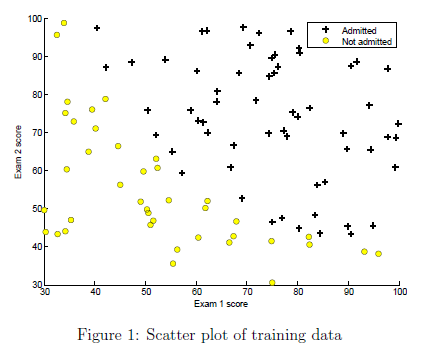

To help you get more familiar with plotting, we have left `plotData.m` empty so you can try to implement it yourself. However, this is an optional (ungraded) exercise. We also provide our implementation below so you can copy it or refer to it. If you choose to copy our example, make sure you learn what each of its commands is doing by consulting the MATLAB documentation.

Once you have added your own or the above code to `plotData.m`, run the code in this section to call the `plotData` function.

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);
 
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Warmup exercise: sigmoid function

Before you start with the actual cost function, recall that the logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


    Your first step is to implement this function in `sigmoid.m` so it can be called by the rest of your program. When you are finished, try testing a few values by calling `sigmoid(x)` in the code section below. For large positive values of `x`, the sigmoid should be close to 1, while for large negative values, the sigmoid should be close to 0. Evaluating `sigmoid(0)` should give you exactly 0.5. **Your code should also work with vectors and matrices**. For a matrix, your function should perform the sigmoid function on every element.

% Provide input values to the sigmoid function below and run to check your implementation
sigmoid(0)

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Cost function and gradient

Now you will implement the cost function and gradient for logistic regression. Complete the code in `costFunction.m` to return the cost and gradient. Recall that the cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


Note that while this gradient looks identical to the linear regression gradient, the formula is actually different because linear and logistic regression have different definitions of $h_{\theta}(x)$. Once you are done, run the code sections below to set up your data and call your `costFunction` using two sets of initial values of $\theta$. 

#### Initialize the data

%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];

% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

#### Compute the gradient

You should see that the cost is about 0.693 and gradients of about -0.1000,  -12.0092, and -11.2628 for all-zero $\theta$, and that the cost is  0.219 with gradients of 0.043, 2.566, 2.640 for non-zero $\theta$.

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);
disp('Gradient at initial theta (zeros):'); 
disp(grad);

% Compute and display cost and gradient with non-zero theta
test_theta = [-24; 0.2; 0.2];
[cost, grad] = costFunction(test_theta, X, y);
fprintf('\nCost at non-zero test theta: %f\n', cost);
disp('Gradient at non-zero theta:'); disp(grad);

#### 1.2.3 Learning parameters using `fminunc`

In the previous assignment, you found the optimal parameters of a linear regression model by implementing gradent descent. You wrote a cost function and calculated its gradient, then took a gradient descent step accordingly. This time, instead of taking gradient descent steps, you will use a MATLAB built-in function called `fminunc`. 

    MATLAB's `fminunc` is an optimization solver that finds the minimum of an unconstrained* function. For logistic regression, you want to optimize the cost function $J(\theta)$ with parameters. Concretely, you are going to use `fminunc` to find the best parameters $\theta$ for the logistic regression cost function, given a fixed dataset (of $X$ and $y$ values). You will pass to `fminunc` the following inputs:

- The initial values of the parameters we are trying to optimize.

- A function that, when given the training set and a particular $\theta$ computes the logistic regression cost and gradient with respect to $\theta$ for the dataset $(X, y)$

**Constraints in optimization often refer to constraints on the parameters, for example, constraints that bound the possible values *$\theta$* can take (e.g. *$\theta<1$*). Logistic regression does not have such constraints since *$\theta$* is allowed to take any real value.*

We already have code written below to call `fminunc` with the correct arguments:

- We first define the options to be used with `fminunc`. Specically, we set the `GradObj` option to `on`, which tells `fminunc` that our function returns both the cost and the gradient. This allows `fminunc` to use the gradient when minimizing the function. 

- Furthermore, we set the `MaxIter` option to 400, so that `fminunc` will run for at most 400 steps before it terminates. 

- To specify the actual function we are minimizing, we use a 'short-hand' for specifying functions with: `@(t)(costFunction(t,X,y))`. This creates a function, with argument `t`, which calls your `costFunction`. This allows us to wrap the `costFunction` for use with `fminunc`.

- If you have completed the `costFunction` correctly, `fminunc` will converge on the right optimization parameters and return the final values of the cost and $\theta$. Notice that by using `fminunc`, you did not have to write any loops yourself, or set a learning rate like you did for gradient descent. This is all done by `fminunc`: you only needed to provide a function calculating the cost and the gradient.

- Once `fminunc` completes, the remaining code will call your `costFunction` function using the optimal parameters of $\theta$. You should see that the cost is about 0.203. This final $\theta$ value will then be used to plot the decision boundary on the training data, resulting in a figure similar to Figure 2. We also encourage you to look at the code in `plotDecisionBoundary.m` to see how to plot such a boundary using the $\theta$ values.

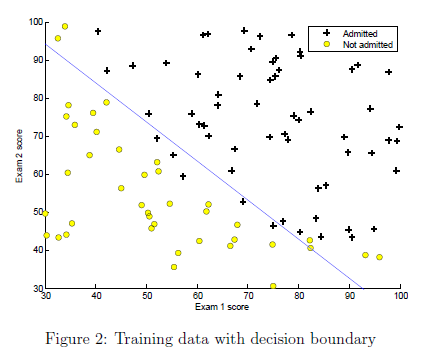

Run the code below and verify the results.

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);

% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);
disp('theta:');disp(theta);

% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

#### 1.2.4 Evaluating logistic regression

After learning the parameters, you can use the model to predict whether a particular student will be admitted. For a student with an Exam 1 score of 45 and an Exam 2 score of 85, you should expect to see an admission probability of 0.776. Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set. In this part, your task is to complete the code in `predict.m`. The predict function will produce '1' or '0' predictions given a dataset and a learned parameter vector $\theta$.

    After you have completed the code in `predict.m`, the code below will proceed to report the training accuracy of your classifier by computing the percentage of examples it got correct. 

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);
fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);
% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Regularized logistic regression

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model.

### 2.1 Visualizing the data

Similar to the previous parts of this exercise, `plotData` is used in the code below to generate a figure like Figure 3, where the axes are the two test scores, and the positive ($y=1,$  accepted) and negative ($y=0,$ rejected) examples are shown with different markers. 

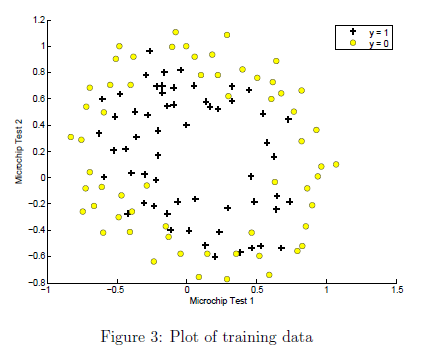

Run the code below and confirm you plot matches Figure 3.

%  The first two columns contains the X values and the third column
%  contains the label (y).
data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

        Figure 3 shows that our dataset cannot be separated into positive and negative examples by a straight-line through the plot. Therefore, a straightforward application of logistic regression will not perform well on this dataset since logistic regression will only be able to find a linear decision boundary.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. In the provided function `mapFeature.m`, we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\textrm{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \;\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


    As a result of this mapping, our vector of two features (the scores on two QA tests) has been transformed into a 28-dimensional vector. A logistic regression classifier trained on this higher-dimension feature vector will have a more complex decision boundary and will appear nonlinear when drawn in our 2-dimensional plot. 

    Run the code below to map the features.

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

    While the feature mapping allows us to build a more expressive classifier, it also more susceptible to overfitting. In the next parts of the exercise, you will implement regularized logistic regression to fit the data and also see for yourself how regularization can help combat the overfitting problem.

### 2.3 Cost function and gradient

Now you will implement code to compute the cost function and gradient for regularized logistic regression. Complete the code in `costFunctionReg.m` to return the cost and gradient. Recall that the regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that you should not regularize the parameter $\theta_0$. In MATLAB, recall that indexing starts from 1, hence, you should not be regularizing the `theta(1)` parameter (which corresponds to $\theta_0$) in the code. The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


Once you are done, run the code below to call your `costFunctionReg` function using the initial value of $\theta$ (initialized to all zeros). You should see that the cost is about 0.693 for all-zero $\theta$ and 3.16 for the non-zero $\theta$ test case.

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);
fprintf('Cost at initial theta (zeros): %f\n', cost);
fprintf('Expected cost (approx): 0.693\n');
fprintf('Gradient at initial theta (zeros) - first five values only:\n');
fprintf(' %f \n', grad(1:5));
fprintf('Expected gradients (approx) - first five values only:\n');
fprintf(' 0.0085\n 0.0188\n 0.0001\n 0.0503\n 0.0115\n');

% Compute and display cost and gradient with all-ones theta and lambda = 10
test_theta = ones(size(X,2),1);
[cost, grad] = costFunctionReg(test_theta, X, y, 10);
fprintf('\nCost at test theta (with lambda = 10): %f\n', cost);
fprintf('Expected cost (approx): 3.16\n');
fprintf('Gradient at test theta - first five values only:\n');
fprintf(' %f \n', grad(1:5));
fprintf('Expected gradients (approx) - first five values only:\n');
fprintf(' 0.3460\n 0.1614\n 0.1948\n 0.2269\n 0.0922\n');

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, the next step is to use `fminunc` to learn the optimal parameters. If you have completed the cost and gradient for regularized logistic regression (`costFunctionReg.m`) correctly, you should be able to run the code in the following sections to learn the parameters using `fminunc` for multiple values of $\lambda$.

### 2.4 Plotting the decision boundary

To help you visualize the model learned by this classifier, we have provided the function `plotDecisionBoundary.m` which plots the (nonlinear) decision boundary that separates the positive and negative examples. In `plotDecisionBoundary.m`, we plot the nonlinear decision boundary by computing the classifier's predictions on an evenly spaced grid and then drew a contour plot of where the predictions change from $y = 0$ to $y = 1$. After learning the parameters, the code in the next section will plot a decision boundary similar to Figure 4.

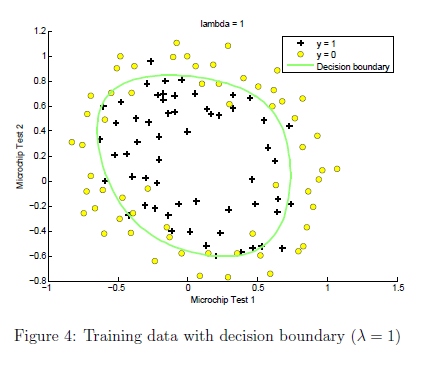

### 2.5 Optional (ungraded) exercises

In this part of the exercise, you will get to try out different regularization parameters for the dataset to understand how regularization prevents overfitting. Notice the changes in the decision boundary as you vary $\lambda$. With a small $\lambda$, you should find that the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data (Figure 5). 

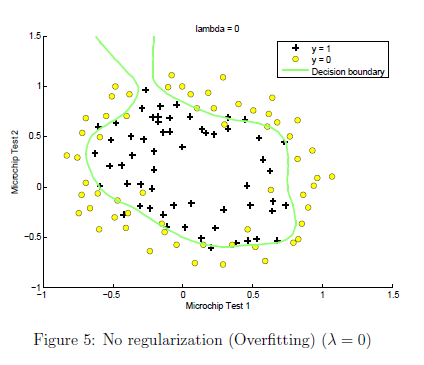

    This is not a good decision boundary: for example, it predicts that a point at $x = (0.25, 1.5)$ is accepted $(y = 1)$, which seems to be an incorrect decision given the training set. With a larger $\lambda$, you should see a plot that shows an simpler decision boundary which still separates the positives and negatives fairly well. However, if $\lambda$ is set to too high a value, you will not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data (Figure 6).

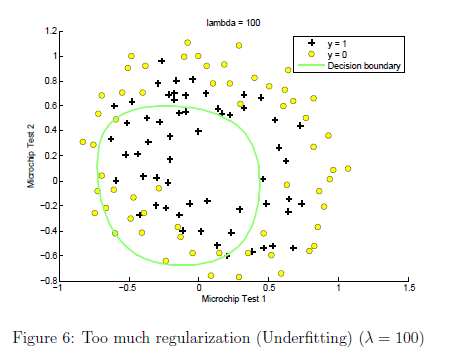

Use the control below to try the following values of $\lambda$: 0, 1, 10, 100. 

- How does the decision boundary change when you vary $\lambda$? 

- How does the training set accuracy vary?

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


preditions =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


J = 0.6931

grad =     0.0085
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235


grad =     0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235


g =     0.4860
    0.4879
    0.4879
    0.4943
    0.4941
    0.4966
    0.4978
    0.4978
    0.4964
    0.4949


preditions =     0.4860
    0.4879
    0.4879
    0.4943
    0.4941
    0.4966
    0.4978
    0.4978
    0.4964
    0.4949


J = 0.6812

grad =    -0.0071
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0071
    0.0146
   -0.0064
    0.0451
    0.0113
    0.0305
    0.0153
    0.0063
    0.0075
    0.0182


grad =    -0.0071
    0.0146
   -0.0064
    0.0451
    0.0113
    0.0305
    0.0153
    0.0063
    0.0075
    0.0182


g =     0.4724
    0.4915
    0.4919
    0.5464
    0.5386
    0.5505
    0.5595
    0.5513
    0.5344
    0.5146


preditions =     0.4724
    0.4915
    0.4919
    0.5464
    0.5386
    0.5505
    0.5595
    0.5513
    0.5344
    0.5146


J = 0.6011

grad =    -0.0568
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0568
   -0.0186
   -0.0345
    0.0192
    0.0086
   -0.0003
   -0.0061
    0.0018
    0.0022
   -0.0070


grad =    -0.0568
   -0.0186
   -0.0345
    0.0192
    0.0086
   -0.0003
   -0.0061
    0.0018
    0.0022
   -0.0070


g =     0.5364
    0.5680
    0.5657
    0.6478
    0.6258
    0.6350
    0.6504
    0.6317
    0.6043
    0.5670


preditions =     0.5364
    0.5680
    0.5657
    0.6478
    0.6258
    0.6350
    0.6504
    0.6317
    0.6043
    0.5670


J = 0.5473

grad =    -0.0408
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0408
   -0.0356
   -0.0366
    0.0132
    0.0069
   -0.0036
   -0.0154
    0.0014
   -0.0005
   -0.0121


grad =    -0.0408
   -0.0356
   -0.0366
    0.0132
    0.0069
   -0.0036
   -0.0154
    0.0014
   -0.0005
   -0.0121


g =     0.6613
    0.7007
    0.6903
    0.7824
    0.7379
    0.7358
    0.7610
    0.7302
    0.6993
    0.6400


preditions =     0.6613
    0.7007
    0.6903
    0.7824
    0.7379
    0.7358
    0.7610
    0.7302
    0.6993
    0.6400


J = 0.4896

grad =    -0.0046
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0046
   -0.0457
   -0.0295
    0.0106
    0.0060
   -0.0000
   -0.0204
    0.0022
   -0.0021
   -0.0119


grad =    -0.0046
   -0.0457
   -0.0295
    0.0106
    0.0060
   -0.0000
   -0.0204
    0.0022
   -0.0021
   -0.0119


g =     0.7673
    0.8025
    0.7841
    0.8630
    0.8025
    0.7880
    0.8229
    0.7847
    0.7595
    0.6845


preditions =     0.7673
    0.8025
    0.7841
    0.8630
    0.8025
    0.7880
    0.8229
    0.7847
    0.7595
    0.6845


J = 0.4508

grad =     0.0145
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0145
   -0.0436
   -0.0211
    0.0073
    0.0066
    0.0028
   -0.0195
    0.0028
   -0.0021
   -0.0096


grad =     0.0145
   -0.0436
   -0.0211
    0.0073
    0.0066
    0.0028
   -0.0195
    0.0028
   -0.0021
   -0.0096


g =     0.8501
    0.8754
    0.8521
    0.9108
    0.8374
    0.8085
    0.8554
    0.8100
    0.7956
    0.7065


preditions =     0.8501
    0.8754
    0.8521
    0.9108
    0.8374
    0.8085
    0.8554
    0.8100
    0.7956
    0.7065


J = 0.4206

grad =     0.0183
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0183
   -0.0344
   -0.0128
    0.0023
    0.0079
    0.0035
   -0.0156
    0.0032
   -0.0012
   -0.0067


grad =     0.0183
   -0.0344
   -0.0128
    0.0023
    0.0079
    0.0035
   -0.0156
    0.0032
   -0.0012
   -0.0067


g =     0.8959
    0.9130
    0.8878
    0.9313
    0.8450
    0.8002
    0.8617
    0.8077
    0.8061
    0.7054


preditions =     0.8959
    0.9130
    0.8878
    0.9313
    0.8450
    0.8002
    0.8617
    0.8077
    0.8061
    0.7054


J = 0.4023

grad =     0.0124
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0124
   -0.0240
   -0.0065
   -0.0021
    0.0094
    0.0028
   -0.0115
    0.0032
    0.0001
   -0.0045


grad =     0.0124
   -0.0240
   -0.0065
   -0.0021
    0.0094
    0.0028
   -0.0115
    0.0032
    0.0001
   -0.0045


g =     0.9184
    0.9302
    0.9038
    0.9372
    0.8343
    0.7705
    0.8498
    0.7852
    0.7993
    0.6893


preditions =     0.9184
    0.9302
    0.9038
    0.9372
    0.8343
    0.7705
    0.8498
    0.7852
    0.7993
    0.6893


J = 0.3916

grad =     0.0034
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0034
   -0.0142
   -0.0022
   -0.0050
    0.0108
    0.0017
   -0.0079
    0.0031
    0.0014
   -0.0029


grad =     0.0034
   -0.0142
   -0.0022
   -0.0050
    0.0108
    0.0017
   -0.0079
    0.0031
    0.0014
   -0.0029


g =     0.9272
    0.9358
    0.9077
    0.9343
    0.8110
    0.7261
    0.8243
    0.7486
    0.7810
    0.6660


preditions =     0.9272
    0.9358
    0.9077
    0.9343
    0.8110
    0.7261
    0.8243
    0.7486
    0.7810
    0.6660


J = 0.3851

grad =    -0.0051
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0051
   -0.0056
    0.0006
   -0.0066
    0.0119
    0.0008
   -0.0049
    0.0030
    0.0026
   -0.0019


grad =    -0.0051
   -0.0056
    0.0006
   -0.0066
    0.0119
    0.0008
   -0.0049
    0.0030
    0.0026
   -0.0019


g = 118×1
    0.9274
    0.9343
    0.9042
    0.9252
    0.7813
    0.6771
    0.7904
    0.7057
    0.7571
    0.6431


preditions = 118×1
    0.9274
    0.9343
    0.9042
    0.9252
    0.7813
    0.6771
    0.7904
    0.7057
    0.7571
    0.6431


J = 0.3806

grad = 28×1
   -0.0112
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0112
    0.0020
    0.0021
   -0.0068
    0.0126
    0.0005
   -0.0023
    0.0029
    0.0038
   -0.0013


grad = 28×1
   -0.0112
    0.0020
    0.0021
   -0.0068
    0.0126
    0.0005
   -0.0023
    0.0029
    0.0038
   -0.0013


g = 118×1
    0.9216
    0.9279
    0.8963
    0.9121
    0.7528
    0.6345
    0.7547
    0.6650
    0.7332
    0.6263


preditions = 118×1
    0.9216
    0.9279
    0.8963
    0.9121
    0.7528
    0.6345
    0.7547
    0.6650
    0.7332
    0.6263


J = 0.3767

grad = 28×1
   -0.0132
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0132
    0.0085
    0.0025
   -0.0054
    0.0125
    0.0012
    0.0001
    0.0027
    0.0049
   -0.0009


grad = 28×1
   -0.0132
    0.0085
    0.0025
   -0.0054
    0.0125
    0.0012
    0.0001
    0.0027
    0.0049
   -0.0009


g = 118×1
    0.9122
    0.9195
    0.8886
    0.9005
    0.7389
    0.6145
    0.7307
    0.6406
    0.7180
    0.6219


preditions = 118×1
    0.9122
    0.9195
    0.8886
    0.9005
    0.7389
    0.6145
    0.7307
    0.6406
    0.7180
    0.6219


J = 0.3731

grad = 28×1
   -0.0092
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0092
    0.0130
    0.0018
   -0.0025
    0.0113
    0.0032
    0.0021
    0.0024
    0.0055
   -0.0008


grad = 28×1
   -0.0092
    0.0130
    0.0018
   -0.0025
    0.0113
    0.0032
    0.0021
    0.0024
    0.0055
   -0.0008


g = 118×1
    0.9046
    0.9150
    0.8882
    0.8993
    0.7514
    0.6288
    0.7324
    0.6437
    0.7193
    0.6323


preditions = 118×1
    0.9046
    0.9150
    0.8882
    0.8993
    0.7514
    0.6288
    0.7324
    0.6437
    0.7193
    0.6323


J = 0.3692

grad = 28×1
	1.0e+-3 *

    0.8694
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0009
    0.0136
    0.0006
    0.0013
    0.0088
    0.0062
    0.0029
    0.0021
    0.0053
   -0.0006


grad = 28×1
    0.0009
    0.0136
    0.0006
    0.0013
    0.0088
    0.0062
    0.0029
    0.0021
    0.0053
   -0.0006


g = 118×1
    0.9046
    0.9199
    0.8999
    0.9129
    0.7895
    0.6730
    0.7604
    0.6715
    0.7367
    0.6529


preditions = 118×1
    0.9046
    0.9199
    0.8999
    0.9129
    0.7895
    0.6730
    0.7604
    0.6715
    0.7367
    0.6529


J = 0.3645

grad = 28×1
    0.0143
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0143
    0.0094
   -0.0002
    0.0046
    0.0051
    0.0093
    0.0019
    0.0019
    0.0040
   -0.0003


grad = 28×1
    0.0143
    0.0094
   -0.0002
    0.0046
    0.0051
    0.0093
    0.0019
    0.0019
    0.0040
   -0.0003


g = 118×1
    0.9138
    0.9328
    0.9189
    0.9326
    0.8301
    0.7163
    0.7924
    0.6989
    0.7551
    0.6672


preditions = 118×1
    0.9138
    0.9328
    0.9189
    0.9326
    0.8301
    0.7163
    0.7924
    0.6989
    0.7551
    0.6672


J = 0.3597

grad = 28×1
    0.0225
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0225
    0.0042
    0.0004
    0.0056
    0.0019
    0.0107
    0.0002
    0.0019
    0.0023
    0.0002


grad = 28×1
    0.0225
    0.0042
    0.0004
    0.0056
    0.0019
    0.0107
    0.0002
    0.0019
    0.0023
    0.0002


g = 118×1
    0.9252
    0.9464
    0.9373
    0.9493
    0.8604
    0.7414
    0.8126
    0.7079
    0.7619
    0.6644


preditions = 118×1
    0.9252
    0.9464
    0.9373
    0.9493
    0.8604
    0.7414
    0.8126
    0.7079
    0.7619
    0.6644


J = 0.3548

grad = 28×1
    0.0230
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0230
    0.0011
    0.0020
    0.0050
   -0.0007
    0.0103
   -0.0009
    0.0017
    0.0007
    0.0008


grad = 28×1
    0.0230
    0.0011
    0.0020
    0.0050
   -0.0007
    0.0103
   -0.0009
    0.0017
    0.0007
    0.0008


g = 118×1
    0.9310
    0.9539
    0.9472
    0.9575
    0.8726
    0.7425
    0.8150
    0.6954
    0.7527
    0.6432


preditions = 118×1
    0.9310
    0.9539
    0.9472
    0.9575
    0.8726
    0.7425
    0.8150
    0.6954
    0.7527
    0.6432


J = 0.3515

grad = 28×1
    0.0161
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0161
    0.0003
    0.0032
    0.0032
   -0.0022
    0.0084
   -0.0012
    0.0014
   -0.0003
    0.0011


grad = 28×1
    0.0161
    0.0003
    0.0032
    0.0032
   -0.0022
    0.0084
   -0.0012
    0.0014
   -0.0003
    0.0011


g = 118×1
    0.9296
    0.9546
    0.9488
    0.9587
    0.8712
    0.7302
    0.8063
    0.6745
    0.7353
    0.6167


preditions = 118×1
    0.9296
    0.9546
    0.9488
    0.9587
    0.8712
    0.7302
    0.8063
    0.6745
    0.7353
    0.6167


J = 0.3499

grad = 28×1
    0.0070
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0070
    0.0003
    0.0035
    0.0014
   -0.0026
    0.0059
   -0.0012
    0.0011
   -0.0008
    0.0009


grad = 28×1
    0.0070
    0.0003
    0.0035
    0.0014
   -0.0026
    0.0059
   -0.0012
    0.0011
   -0.0008
    0.0009


g = 118×1
    0.9238
    0.9515
    0.9459
    0.9563
    0.8641
    0.7167
    0.7958
    0.6580
    0.7199
    0.5968


preditions = 118×1
    0.9238
    0.9515
    0.9459
    0.9563
    0.8641
    0.7167
    0.7958
    0.6580
    0.7199
    0.5968


J = 0.3492

grad = 28×1
	1.0e+-3 *

   -0.5092
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0005
    0.0003
    0.0030
    0.0001
   -0.0027
    0.0038
   -0.0012
    0.0008
   -0.0011
    0.0004


grad = 28×1
   -0.0005
    0.0003
    0.0030
    0.0001
   -0.0027
    0.0038
   -0.0012
    0.0008
   -0.0011
    0.0004


g = 118×1
    0.9164
    0.9468
    0.9411
    0.9526
    0.8560
    0.7075
    0.7883
    0.6496
    0.7102
    0.5857


preditions = 118×1
    0.9164
    0.9468
    0.9411
    0.9526
    0.8560
    0.7075
    0.7883
    0.6496
    0.7102
    0.5857


J = 0.3487

grad = 28×1
   -0.0056
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0056
    0.0001
    0.0018
   -0.0007
   -0.0026
    0.0023
   -0.0012
    0.0006
   -0.0012
   -0.0003


grad = 28×1
   -0.0056
    0.0001
    0.0018
   -0.0007
   -0.0026
    0.0023
   -0.0012
    0.0006
   -0.0012
   -0.0003


g = 118×1
    0.9072
    0.9407
    0.9348
    0.9481
    0.8475
    0.7024
    0.7844
    0.6483
    0.7054
    0.5809


preditions = 118×1
    0.9072
    0.9407
    0.9348
    0.9481
    0.8475
    0.7024
    0.7844
    0.6483
    0.7054
    0.5809


J = 0.3482

grad = 28×1
   -0.0091
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0091
   -0.0002
    0.0002
   -0.0012
   -0.0024
    0.0010
   -0.0013
    0.0003
   -0.0012
   -0.0011


grad = 28×1
   -0.0091
   -0.0002
    0.0002
   -0.0012
   -0.0024
    0.0010
   -0.0013
    0.0003
   -0.0012
   -0.0011


g = 118×1
    0.8960
    0.9331
    0.9270
    0.9431
    0.8388
    0.7026
    0.7860
    0.6560
    0.7069
    0.5825


preditions = 118×1
    0.8960
    0.9331
    0.9270
    0.9431
    0.8388
    0.7026
    0.7860
    0.6560
    0.7069
    0.5825


J = 0.3475

grad = 28×1
   -0.0112
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0112
   -0.0007
   -0.0023
   -0.0014
   -0.0023
   -0.0003
   -0.0013
   -0.0000
   -0.0012
   -0.0021


grad = 28×1
   -0.0112
   -0.0007
   -0.0023
   -0.0014
   -0.0023
   -0.0003
   -0.0013
   -0.0000
   -0.0012
   -0.0021


g = 118×1
    0.8830
    0.9246
    0.9181
    0.9382
    0.8303
    0.7104
    0.7967
    0.6771
    0.7180
    0.5923


preditions = 118×1
    0.8830
    0.9246
    0.9181
    0.9382
    0.8303
    0.7104
    0.7967
    0.6771
    0.7180
    0.5923


J = 0.3461

grad = 28×1
   -0.0110
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0110
   -0.0011
   -0.0058
   -0.0012
   -0.0021
   -0.0016
   -0.0012
   -0.0006
   -0.0011
   -0.0035


grad = 28×1
   -0.0110
   -0.0011
   -0.0058
   -0.0012
   -0.0021
   -0.0016
   -0.0012
   -0.0006
   -0.0011
   -0.0035


g = 118×1
    0.8733
    0.9190
    0.9120
    0.9363
    0.8244
    0.7273
    0.8193
    0.7128
    0.7406
    0.6099


preditions = 118×1
    0.8733
    0.9190
    0.9120
    0.9363
    0.8244
    0.7273
    0.8193
    0.7128
    0.7406
    0.6099


J = 0.3440

grad = 28×1
   -0.0077
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0077
   -0.0009
   -0.0099
   -0.0005
   -0.0018
   -0.0027
   -0.0007
   -0.0013
   -0.0008
   -0.0050


grad = 28×1
   -0.0077
   -0.0009
   -0.0099
   -0.0005
   -0.0018
   -0.0027
   -0.0007
   -0.0013
   -0.0008
   -0.0050


g = 118×1
    0.8758
    0.9223
    0.9149
    0.9400
    0.8238
    0.7475
    0.8469
    0.7513
    0.7671
    0.6264


preditions = 118×1
    0.8758
    0.9223
    0.9149
    0.9400
    0.8238
    0.7475
    0.8469
    0.7513
    0.7671
    0.6264


J = 0.3415

grad = 28×1
   -0.0021
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0021
    0.0004
   -0.0123
    0.0004
   -0.0014
   -0.0030
    0.0003
   -0.0019
   -0.0005
   -0.0056


grad = 28×1
   -0.0021
    0.0004
   -0.0123
    0.0004
   -0.0014
   -0.0030
    0.0003
   -0.0019
   -0.0005
   -0.0056


g = 118×1
    0.8891
    0.9323
    0.9247
    0.9465
    0.8266
    0.7610
    0.8670
    0.7759
    0.7840
    0.6301


preditions = 118×1
    0.8891
    0.9323
    0.9247
    0.9465
    0.8266
    0.7610
    0.8670
    0.7759
    0.7840
    0.6301


J = 0.3393

grad = 28×1
    0.0022
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0022
    0.0021
   -0.0114
    0.0008
   -0.0009
   -0.0025
    0.0014
   -0.0022
   -0.0003
   -0.0048


grad = 28×1
    0.0022
    0.0021
   -0.0114
    0.0008
   -0.0009
   -0.0025
    0.0014
   -0.0022
   -0.0003
   -0.0048


g = 118×1
    0.9024
    0.9414
    0.9339
    0.9514
    0.8282
    0.7663
    0.8774
    0.7862
    0.7882
    0.6199


preditions = 118×1
    0.9024
    0.9414
    0.9339
    0.9514
    0.8282
    0.7663
    0.8774
    0.7862
    0.7882
    0.6199


J = 0.3377

grad = 28×1
    0.0039
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0039
    0.0032
   -0.0086
    0.0008
   -0.0003
   -0.0018
    0.0020
   -0.0020
   -0.0004
   -0.0032


grad = 28×1
    0.0039
    0.0032
   -0.0086
    0.0008
   -0.0003
   -0.0018
    0.0020
   -0.0020
   -0.0004
   -0.0032


g = 118×1
    0.9116
    0.9472
    0.9399
    0.9537
    0.8269
    0.7671
    0.8819
    0.7886
    0.7831
    0.5998


preditions = 118×1
    0.9116
    0.9472
    0.9399
    0.9537
    0.8269
    0.7671
    0.8819
    0.7886
    0.7831
    0.5998


J = 0.3365

grad = 28×1
    0.0037
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0037
    0.0033
   -0.0047
    0.0004
    0.0003
   -0.0010
    0.0022
   -0.0016
   -0.0007
   -0.0012


grad = 28×1
    0.0037
    0.0033
   -0.0047
    0.0004
    0.0003
   -0.0010
    0.0022
   -0.0016
   -0.0007
   -0.0012


g = 118×1
    0.9146
    0.9487
    0.9415
    0.9529
    0.8231
    0.7659
    0.8818
    0.7863
    0.7719
    0.5766


preditions = 118×1
    0.9146
    0.9487
    0.9415
    0.9529
    0.8231
    0.7659
    0.8818
    0.7863
    0.7719
    0.5766


J = 0.3356

grad = 28×1
    0.0022
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0022
    0.0023
   -0.0010
   -0.0001
    0.0009
   -0.0003
    0.0019
   -0.0011
   -0.0011
    0.0008


grad = 28×1
    0.0022
    0.0023
   -0.0010
   -0.0001
    0.0009
   -0.0003
    0.0019
   -0.0011
   -0.0011
    0.0008


g = 118×1
    0.9116
    0.9462
    0.9389
    0.9501
    0.8191
    0.7649
    0.8790
    0.7829
    0.7619
    0.5629


preditions = 118×1
    0.9116
    0.9462
    0.9389
    0.9501
    0.8191
    0.7649
    0.8790
    0.7829
    0.7619
    0.5629


J = 0.3352

grad = 28×1
	1.0e+-3 *

    0.5268
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0005
    0.0006
    0.0009
   -0.0006
    0.0013
   -0.0001
    0.0012
   -0.0007
   -0.0015
    0.0019


grad = 28×1
    0.0005
    0.0006
    0.0009
   -0.0006
    0.0013
   -0.0001
    0.0012
   -0.0007
   -0.0015
    0.0019


g = 118×1
    0.9070
    0.9428
    0.9356
    0.9477
    0.8174
    0.7654
    0.8769
    0.7816
    0.7582
    0.5615


preditions = 118×1
    0.9070
    0.9428
    0.9356
    0.9477
    0.8174
    0.7654
    0.8769
    0.7816
    0.7582
    0.5615


J = 0.3350

grad = 28×1
	1.0e+-3 *

   -0.2646
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0003
   -0.0005
    0.0009
   -0.0007
    0.0013
   -0.0002
    0.0008
   -0.0006
   -0.0017
    0.0019


grad = 28×1
   -0.0003
   -0.0005
    0.0009
   -0.0007
    0.0013
   -0.0002
    0.0008
   -0.0006
   -0.0017
    0.0019


g = 118×1
    0.9044
    0.9411
    0.9339
    0.9467
    0.8173
    0.7667
    0.8766
    0.7820
    0.7583
    0.5639


preditions = 118×1
    0.9044
    0.9411
    0.9339
    0.9467
    0.8173
    0.7667
    0.8766
    0.7820
    0.7583
    0.5639


J = 0.3349

grad = 28×1
	1.0e+-3 *

   -0.1527
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0002
   -0.0010
    0.0004
   -0.0007
    0.0013
   -0.0003
    0.0006
   -0.0006
   -0.0018
    0.0017


grad = 28×1
   -0.0002
   -0.0010
    0.0004
   -0.0007
    0.0013
   -0.0003
    0.0006
   -0.0006
   -0.0018
    0.0017


g = 118×1
    0.9006
    0.9386
    0.9315
    0.9456
    0.8179
    0.7697
    0.8769
    0.7835
    0.7596
    0.5691


preditions = 118×1
    0.9006
    0.9386
    0.9315
    0.9456
    0.8179
    0.7697
    0.8769
    0.7835
    0.7596
    0.5691


J = 0.3347

grad = 28×1
	1.0e+-3 *

    0.3631
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0004
   -0.0015
   -0.0004
   -0.0005
    0.0011
   -0.0003
    0.0004
   -0.0006
   -0.0018
    0.0014


grad = 28×1
    0.0004
   -0.0015
   -0.0004
   -0.0005
    0.0011
   -0.0003
    0.0004
   -0.0006
   -0.0018
    0.0014


g = 118×1
    0.8948
    0.9350
    0.9279
    0.9442
    0.8193
    0.7758
    0.8784
    0.7861
    0.7619
    0.5775


preditions = 118×1
    0.8948
    0.9350
    0.9279
    0.9442
    0.8193
    0.7758
    0.8784
    0.7861
    0.7619
    0.5775


J = 0.3343

grad = 28×1
    0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0014
   -0.0023
   -0.0017
   -0.0002
    0.0008
   -0.0003
   -0.0000
   -0.0007
   -0.0018
    0.0008


grad = 28×1
    0.0014
   -0.0023
   -0.0017
   -0.0002
    0.0008
   -0.0003
   -0.0000
   -0.0007
   -0.0018
    0.0008


g = 118×1
    0.8854
    0.9291
    0.9224
    0.9425
    0.8221
    0.7875
    0.8819
    0.7895
    0.7651
    0.5907


preditions = 118×1
    0.8854
    0.9291
    0.9224
    0.9425
    0.8221
    0.7875
    0.8819
    0.7895
    0.7651
    0.5907


J = 0.3332

grad = 28×1
    0.0030
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0030
   -0.0035
   -0.0037
    0.0002
    0.0002
   -0.0001
   -0.0006
   -0.0009
   -0.0018
    0.0001


grad = 28×1
    0.0030
   -0.0035
   -0.0037
    0.0002
    0.0002
   -0.0001
   -0.0006
   -0.0009
   -0.0018
    0.0001


g = 118×1
    0.8725
    0.9213
    0.9149
    0.9412
    0.8266
    0.8065
    0.8887
    0.7915
    0.7671
    0.6066


preditions = 118×1
    0.8725
    0.9213
    0.9149
    0.9412
    0.8266
    0.8065
    0.8887
    0.7915
    0.7671
    0.6066


J = 0.3310

grad = 28×1
    0.0051
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0051
   -0.0044
   -0.0061
    0.0005
   -0.0005
    0.0003
   -0.0014
   -0.0011
   -0.0016
   -0.0008


grad = 28×1
    0.0051
   -0.0044
   -0.0061
    0.0005
   -0.0005
    0.0003
   -0.0014
   -0.0011
   -0.0016
   -0.0008


g = 118×1
    0.8626
    0.9157
    0.9091
    0.9421
    0.8319
    0.8293
    0.8982
    0.7871
    0.7633
    0.6164


preditions = 118×1
    0.8626
    0.9157
    0.9091
    0.9421
    0.8319
    0.8293
    0.8982
    0.7871
    0.7633
    0.6164


J = 0.3274

grad = 28×1
    0.0064
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0064
   -0.0038
   -0.0075
    0.0004
   -0.0013
    0.0011
   -0.0018
   -0.0014
   -0.0011
   -0.0012


grad = 28×1
    0.0064
   -0.0038
   -0.0075
    0.0004
   -0.0013
    0.0011
   -0.0018
   -0.0014
   -0.0011
   -0.0012


g = 118×1
    0.8673
    0.9194
    0.9113
    0.9467
    0.8365
    0.8450
    0.9059
    0.7738
    0.7512
    0.6079


preditions = 118×1
    0.8673
    0.9194
    0.9113
    0.9467
    0.8365
    0.8450
    0.9059
    0.7738
    0.7512
    0.6079


J = 0.3241

grad = 28×1
    0.0046
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0046
   -0.0013
   -0.0062
   -0.0006
   -0.0012
    0.0017
   -0.0015
   -0.0015
   -0.0004
   -0.0006


grad = 28×1
    0.0046
   -0.0013
   -0.0062
   -0.0006
   -0.0012
    0.0017
   -0.0015
   -0.0015
   -0.0004
   -0.0006


g = 118×1
    0.8794
    0.9273
    0.9181
    0.9514
    0.8396
    0.8495
    0.9090
    0.7613
    0.7383
    0.5888


preditions = 118×1
    0.8794
    0.9273
    0.9181
    0.9514
    0.8396
    0.8495
    0.9090
    0.7613
    0.7383
    0.5888


J = 0.3228

grad = 28×1
    0.0012
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0012
    0.0005
   -0.0036
   -0.0018
   -0.0006
    0.0015
   -0.0012
   -0.0013
   -0.0000
    0.0002


grad = 28×1
    0.0012
    0.0005
   -0.0036
   -0.0018
   -0.0006
    0.0015
   -0.0012
   -0.0013
   -0.0000
    0.0002


g = 118×1
    0.8848
    0.9309
    0.9216
    0.9534
    0.8414
    0.8507
    0.9100
    0.7566
    0.7315
    0.5765


preditions = 118×1
    0.8848
    0.9309
    0.9216
    0.9534
    0.8414
    0.8507
    0.9100
    0.7566
    0.7315
    0.5765


J = 0.3225

grad = 28×1
	1.0e+-3 *

   -0.1964
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0002
    0.0009
   -0.0020
   -0.0022
   -0.0003
    0.0015
   -0.0011
   -0.0012
   -0.0000
    0.0008


grad = 28×1
   -0.0002
    0.0009
   -0.0020
   -0.0022
   -0.0003
    0.0015
   -0.0011
   -0.0012
   -0.0000
    0.0008


g = 118×1
    0.8877
    0.9330
    0.9237
    0.9548
    0.8434
    0.8518
    0.9107
    0.7542
    0.7272
    0.5682


preditions = 118×1
    0.8877
    0.9330
    0.9237
    0.9548
    0.8434
    0.8518
    0.9107
    0.7542
    0.7272
    0.5682


J = 0.3223

grad = 28×1
   -0.0011
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0011
    0.0011
   -0.0012
   -0.0024
   -0.0001
    0.0013
   -0.0010
   -0.0011
   -0.0000
    0.0010


grad = 28×1
   -0.0011
    0.0011
   -0.0012
   -0.0024
   -0.0001
    0.0013
   -0.0010
   -0.0011
   -0.0000
    0.0010


g = 118×1
    0.8909
    0.9355
    0.9266
    0.9571
    0.8486
    0.8564
    0.9129
    0.7509
    0.7173
    0.5501


preditions = 118×1
    0.8909
    0.9355
    0.9266
    0.9571
    0.8486
    0.8564
    0.9129
    0.7509
    0.7173
    0.5501


J = 0.3219

grad = 28×1
   -0.0021
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0021
    0.0012
    0.0004
   -0.0023
    0.0002
    0.0010
   -0.0008
   -0.0008
   -0.0001
    0.0015


grad = 28×1
   -0.0021
    0.0012
    0.0004
   -0.0023
    0.0002
    0.0010
   -0.0008
   -0.0008
   -0.0001
    0.0015


g = 118×1
    0.8912
    0.9366
    0.9283
    0.9598
    0.8574
    0.8652
    0.9166
    0.7485
    0.7043
    0.5278


preditions = 118×1
    0.8912
    0.9366
    0.9283
    0.9598
    0.8574
    0.8652
    0.9166
    0.7485
    0.7043
    0.5278


J = 0.3213

grad = 28×1
   -0.0028
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0028
    0.0014
    0.0016
   -0.0017
    0.0004
    0.0002
   -0.0006
   -0.0005
   -0.0001
    0.0015


grad = 28×1
   -0.0028
    0.0014
    0.0016
   -0.0017
    0.0004
    0.0002
   -0.0006
   -0.0005
   -0.0001
    0.0015


g = 118×1
    0.8853
    0.9340
    0.9264
    0.9614
    0.8670
    0.8775
    0.9213
    0.7495
    0.6913
    0.5086


preditions = 118×1
    0.8853
    0.9340
    0.9264
    0.9614
    0.8670
    0.8775
    0.9213
    0.7495
    0.6913
    0.5086


J = 0.3207

grad = 28×1
   -0.0020
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0020
    0.0012
    0.0022
   -0.0003
    0.0005
   -0.0005
   -0.0005
   -0.0002
   -0.0001
    0.0013


grad = 28×1
   -0.0020
    0.0012
    0.0022
   -0.0003
    0.0005
   -0.0005
   -0.0005
   -0.0002
   -0.0001
    0.0013


g = 118×1
    0.8772
    0.9295
    0.9223
    0.9611
    0.8715
    0.8845
    0.9236
    0.7530
    0.6893
    0.5085


preditions = 118×1
    0.8772
    0.9295
    0.9223
    0.9611
    0.8715
    0.8845
    0.9236
    0.7530
    0.6893
    0.5085


J = 0.3204

grad = 28×1
	1.0e+-3 *

   -0.7770
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0008
    0.0008
    0.0011
    0.0007
    0.0003
   -0.0010
   -0.0005
   -0.0001
   -0.0001
    0.0005


grad = 28×1
   -0.0008
    0.0008
    0.0011
    0.0007
    0.0003
   -0.0010
   -0.0005
   -0.0001
   -0.0001
    0.0005


g = 118×1
    0.8730
    0.9269
    0.9198
    0.9603
    0.8715
    0.8858
    0.9238
    0.7553
    0.6919
    0.5148


preditions = 118×1
    0.8730
    0.9269
    0.9198
    0.9603
    0.8715
    0.8858
    0.9238
    0.7553
    0.6919
    0.5148


J = 0.3203

grad = 28×1
	1.0e+-4 *

    0.1052
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0105
    0.4873
    0.2739
    0.9180
    0.1721
   -0.9916
   -0.6626
   -0.2031
   -0.0403
    0.2156


grad = 28×1
	1.0e+-3 *

    0.0105
    0.4873
    0.2739
    0.9180
    0.1721
   -0.9916
   -0.6626
   -0.2031
   -0.0403
    0.2156


g = 118×1
    0.8722
    0.9264
    0.9193
    0.9599
    0.8710
    0.8856
    0.9236
    0.7559
    0.6938
    0.5184


preditions = 118×1
    0.8722
    0.9264
    0.9193
    0.9599
    0.8710
    0.8856
    0.9236
    0.7559
    0.6938
    0.5184


J = 0.3203

grad = 28×1
	1.0e+-3 *

    0.1956
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1956
    0.3570
   -0.0277
    0.8893
    0.1179
   -0.9407
   -0.7388
   -0.2431
   -0.0310
    0.1194


grad = 28×1
	1.0e+-3 *

    0.1956
    0.3570
   -0.0277
    0.8893
    0.1179
   -0.9407
   -0.7388
   -0.2431
   -0.0310
    0.1194


g = 118×1
    0.8716
    0.9259
    0.9188
    0.9596
    0.8706
    0.8855
    0.9235
    0.7568
    0.6960
    0.5228


preditions = 118×1
    0.8716
    0.9259
    0.9188
    0.9596
    0.8706
    0.8855
    0.9235
    0.7568
    0.6960
    0.5228


J = 0.3202

grad = 28×1
	1.0e+-3 *

    0.4444
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.4444
    0.1580
   -0.3052
    0.8273
    0.0546
   -0.8239
   -0.8478
   -0.2811
   -0.0323
    0.0609


grad = 28×1
	1.0e+-3 *

    0.4444
    0.1580
   -0.3052
    0.8273
    0.0546
   -0.8239
   -0.8478
   -0.2811
   -0.0323
    0.0609


g = 118×1
    0.8708
    0.9255
    0.9184
    0.9594
    0.8705
    0.8857
    0.9235
    0.7583
    0.6996
    0.5299


preditions = 118×1
    0.8708
    0.9255
    0.9184
    0.9594
    0.8705
    0.8857
    0.9235
    0.7583
    0.6996
    0.5299


J = 0.3201

grad = 28×1
	1.0e+-3 *

    0.8199
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0008
   -0.0002
   -0.0007
    0.0007
   -0.0000
   -0.0006
   -0.0010
   -0.0003
   -0.0000
   -0.0000


grad = 28×1
    0.0008
   -0.0002
   -0.0007
    0.0007
   -0.0000
   -0.0006
   -0.0010
   -0.0003
   -0.0000
   -0.0000


g = 118×1
    0.8701
    0.9254
    0.9188
    0.9597
    0.8715
    0.8869
    0.9241
    0.7609
    0.7050
    0.5407


preditions = 118×1
    0.8701
    0.9254
    0.9188
    0.9597
    0.8715
    0.8869
    0.9241
    0.7609
    0.7050
    0.5407


J = 0.3199

grad = 28×1
    0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0014
   -0.0008
   -0.0012
    0.0005
   -0.0002
   -0.0003
   -0.0013
   -0.0004
   -0.0001
   -0.0002


grad = 28×1
    0.0014
   -0.0008
   -0.0012
    0.0005
   -0.0002
   -0.0003
   -0.0013
   -0.0004
   -0.0001
   -0.0002


g = 118×1
    0.8697
    0.9268
    0.9212
    0.9612
    0.8750
    0.8901
    0.9259
    0.7654
    0.7128
    0.5564


preditions = 118×1
    0.8697
    0.9268
    0.9212
    0.9612
    0.8750
    0.8901
    0.9259
    0.7654
    0.7128
    0.5564


J = 0.3194

grad = 28×1
    0.0022
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0022
   -0.0018
   -0.0019
    0.0002
   -0.0004
    0.0001
   -0.0017
   -0.0004
   -0.0002
   -0.0003


grad = 28×1
    0.0022
   -0.0018
   -0.0019
    0.0002
   -0.0004
    0.0001
   -0.0017
   -0.0004
   -0.0002
   -0.0003


g = 118×1
    0.8706
    0.9312
    0.9278
    0.9652
    0.8834
    0.8970
    0.9300
    0.7719
    0.7218
    0.5748


preditions = 118×1
    0.8706
    0.9312
    0.9278
    0.9652
    0.8834
    0.8970
    0.9300
    0.7719
    0.7218
    0.5748


J = 0.3182

grad = 28×1
    0.0029
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0029
   -0.0029
   -0.0024
   -0.0003
   -0.0006
    0.0007
   -0.0021
   -0.0003
   -0.0003
   -0.0005


grad = 28×1
    0.0029
   -0.0029
   -0.0024
   -0.0003
   -0.0006
    0.0007
   -0.0021
   -0.0003
   -0.0003
   -0.0005


g = 118×1
    0.8742
    0.9395
    0.9392
    0.9717
    0.8966
    0.9069
    0.9364
    0.7790
    0.7277
    0.5863


preditions = 118×1
    0.8742
    0.9395
    0.9392
    0.9717
    0.8966
    0.9069
    0.9364
    0.7790
    0.7277
    0.5863


J = 0.3165

grad = 28×1
    0.0031
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0031
   -0.0035
   -0.0022
   -0.0007
   -0.0006
    0.0010
   -0.0019
   -0.0000
   -0.0005
   -0.0006


grad = 28×1
    0.0031
   -0.0035
   -0.0022
   -0.0007
   -0.0006
    0.0010
   -0.0019
   -0.0000
   -0.0005
   -0.0006


g = 118×1
    0.8798
    0.9481
    0.9499
    0.9774
    0.9076
    0.9137
    0.9416
    0.7816
    0.7255
    0.5795


preditions = 118×1
    0.8798
    0.9481
    0.9499
    0.9774
    0.9076
    0.9137
    0.9416
    0.7816
    0.7255
    0.5795


J = 0.3150

grad = 28×1
    0.0023
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0023
   -0.0023
   -0.0009
   -0.0004
   -0.0002
    0.0007
   -0.0008
    0.0004
   -0.0006
   -0.0004


grad = 28×1
    0.0023
   -0.0023
   -0.0009
   -0.0004
   -0.0002
    0.0007
   -0.0008
    0.0004
   -0.0006
   -0.0004


g = 118×1
    0.8835
    0.9513
    0.9534
    0.9788
    0.9087
    0.9120
    0.9414
    0.7773
    0.7198
    0.5666


preditions = 118×1
    0.8835
    0.9513
    0.9534
    0.9788
    0.9087
    0.9120
    0.9414
    0.7773
    0.7198
    0.5666


J = 0.3146

grad = 28×1
	1.0e+-3 *

    0.9359
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.9359
   -0.6543
   -0.1164
   -0.0996
    0.0590
    0.1029
    0.0580
    0.5182
   -0.5881
   -0.3597


grad = 28×1
	1.0e+-3 *

    0.9359
   -0.6543
   -0.1164
   -0.0996
    0.0590
    0.1029
    0.0580
    0.5182
   -0.5881
   -0.3597


g = 118×1
    0.8839
    0.9511
    0.9530
    0.9784
    0.9068
    0.9093
    0.9399
    0.7735
    0.7165
    0.5611


preditions = 118×1
    0.8839
    0.9511
    0.9530
    0.9784
    0.9068
    0.9093
    0.9399
    0.7735
    0.7165
    0.5611


J = 0.3146

grad = 28×1
	1.0e+-3 *

    0.2077
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2077
   -0.1175
    0.0518
   -0.1022
    0.0839
   -0.0960
    0.2704
    0.4776
   -0.5605
   -0.3172


grad = 28×1
	1.0e+-3 *

    0.2077
   -0.1175
    0.0518
   -0.1022
    0.0839
   -0.0960
    0.2704
    0.4776
   -0.5605
   -0.3172


g = 118×1
    0.8835
    0.9506
    0.9524
    0.9780
    0.9054
    0.9077
    0.9389
    0.7714
    0.7147
    0.5590


preditions = 118×1
    0.8835
    0.9506
    0.9524
    0.9780
    0.9054
    0.9077
    0.9389
    0.7714
    0.7147
    0.5590


J = 0.3145

grad = 28×1
	1.0e+-4 *

   -0.9632
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0963
    0.1026
    0.0861
   -0.0927
    0.1067
   -0.1566
    0.3480
    0.4584
   -0.5298
   -0.3080


grad = 28×1
	1.0e+-3 *

   -0.0963
    0.1026
    0.0861
   -0.0927
    0.1067
   -0.1566
    0.3480
    0.4584
   -0.5298
   -0.3080


g = 118×1
    0.8825
    0.9496
    0.9513
    0.9772
    0.9030
    0.9051
    0.9371
    0.7680
    0.7121
    0.5566


preditions = 118×1
    0.8825
    0.9496
    0.9513
    0.9772
    0.9030
    0.9051
    0.9371
    0.7680
    0.7121
    0.5566


J = 0.3145

grad = 28×1
	1.0e+-3 *

   -0.5529
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.5529
    0.4288
    0.0579
   -0.0853
    0.1530
   -0.2384
    0.4578
    0.4207
   -0.4634
   -0.3274


grad = 28×1
	1.0e+-3 *

   -0.5529
    0.4288
    0.0579
   -0.0853
    0.1530
   -0.2384
    0.4578
    0.4207
   -0.4634
   -0.3274


g = 118×1
    0.8814
    0.9484
    0.9499
    0.9762
    0.9000
    0.9020
    0.9348
    0.7641
    0.7093
    0.5544


preditions = 118×1
    0.8814
    0.9484
    0.9499
    0.9762
    0.9000
    0.9020
    0.9348
    0.7641
    0.7093
    0.5544


J = 0.3145

grad = 28×1
   -0.0011
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0011
    0.0008
   -0.0000
   -0.0001
    0.0002
   -0.0003
    0.0006
    0.0004
   -0.0004
   -0.0004


grad = 28×1
   -0.0011
    0.0008
   -0.0000
   -0.0001
    0.0002
   -0.0003
    0.0006
    0.0004
   -0.0004
   -0.0004


g = 118×1
    0.8800
    0.9468
    0.9478
    0.9747
    0.8954
    0.8974
    0.9314
    0.7583
    0.7053
    0.5518


preditions = 118×1
    0.8800
    0.9468
    0.9478
    0.9747
    0.8954
    0.8974
    0.9314
    0.7583
    0.7053
    0.5518


J = 0.3143

grad = 28×1
   -0.0018
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0018
    0.0014
   -0.0003
   -0.0001
    0.0003
   -0.0004
    0.0008
    0.0002
   -0.0002
   -0.0005


grad = 28×1
   -0.0018
    0.0014
   -0.0003
   -0.0001
    0.0003
   -0.0004
    0.0008
    0.0002
   -0.0002
   -0.0005


g = 118×1
    0.8794
    0.9453
    0.9458
    0.9729
    0.8899
    0.8925
    0.9275
    0.7514
    0.7002
    0.5488


preditions = 118×1
    0.8794
    0.9453
    0.9458
    0.9729
    0.8899
    0.8925
    0.9275
    0.7514
    0.7002
    0.5488


J = 0.3139

grad = 28×1
   -0.0028
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0028
    0.0022
   -0.0008
   -0.0001
    0.0004
   -0.0005
    0.0011
   -0.0000
    0.0001
   -0.0006


grad = 28×1
   -0.0028
    0.0022
   -0.0008
   -0.0001
    0.0004
   -0.0005
    0.0011
   -0.0000
    0.0001
   -0.0006


g = 118×1
    0.8822
    0.9460
    0.9455
    0.9720
    0.8867
    0.8915
    0.9253
    0.7458
    0.6945
    0.5448


preditions = 118×1
    0.8822
    0.9460
    0.9455
    0.9720
    0.8867
    0.8915
    0.9253
    0.7458
    0.6945
    0.5448


J = 0.3132

grad = 28×1
   -0.0035
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0035
    0.0029
   -0.0013
   -0.0002
    0.0004
   -0.0005
    0.0014
   -0.0004
    0.0005
   -0.0008


grad = 28×1
   -0.0035
    0.0029
   -0.0013
   -0.0002
    0.0004
   -0.0005
    0.0014
   -0.0004
    0.0005
   -0.0008


g = 118×1
    0.8914
    0.9513
    0.9502
    0.9746
    0.8934
    0.9020
    0.9302
    0.7487
    0.6913
    0.5403


preditions = 118×1
    0.8914
    0.9513
    0.9502
    0.9746
    0.8934
    0.9020
    0.9302
    0.7487
    0.6913
    0.5403


J = 0.3122

grad = 28×1
   -0.0032
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0032
    0.0027
   -0.0015
   -0.0002
    0.0003
   -0.0003
    0.0013
   -0.0009
    0.0009
   -0.0008


grad = 28×1
   -0.0032
    0.0027
   -0.0015
   -0.0002
    0.0003
   -0.0003
    0.0013
   -0.0009
    0.0009
   -0.0008


g = 118×1
    0.9039
    0.9595
    0.9585
    0.9800
    0.9097
    0.9211
    0.9419
    0.7629
    0.6937
    0.5362


preditions = 118×1
    0.9039
    0.9595
    0.9585
    0.9800
    0.9097
    0.9211
    0.9419
    0.7629
    0.6937
    0.5362


J = 0.3113

grad = 28×1
   -0.0018
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0018
    0.0012
   -0.0009
   -0.0003
    0.0001
   -0.0002
    0.0008
   -0.0011
    0.0009
   -0.0006


grad = 28×1
   -0.0018
    0.0012
   -0.0009
   -0.0003
    0.0001
   -0.0002
    0.0008
   -0.0011
    0.0009
   -0.0006


g = 118×1
    0.9108
    0.9643
    0.9638
    0.9834
    0.9212
    0.9325
    0.9496
    0.7749
    0.6975
    0.5335


preditions = 118×1
    0.9108
    0.9643
    0.9638
    0.9834
    0.9212
    0.9325
    0.9496
    0.7749
    0.6975
    0.5335


J = 0.3110

grad = 28×1
	1.0e+-3 *

   -0.5687
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.5687
    0.0207
   -0.1341
   -0.1903
   -0.0099
   -0.2068
    0.3855
   -0.9364
    0.6660
   -0.3767


grad = 28×1
	1.0e+-3 *

   -0.5687
    0.0207
   -0.1341
   -0.1903
   -0.0099
   -0.2068
    0.3855
   -0.9364
    0.6660
   -0.3767


g = 118×1
    0.9124
    0.9656
    0.9653
    0.9843
    0.9244
    0.9351
    0.9514
    0.7781
    0.6987
    0.5325


preditions = 118×1
    0.9124
    0.9656
    0.9653
    0.9843
    0.9244
    0.9351
    0.9514
    0.7781
    0.6987
    0.5325


J = 0.3110

grad = 28×1
	1.0e+-4 *

   -0.5801
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0580
   -0.3160
    0.2214
   -0.1015
   -0.0848
   -0.1470
    0.2914
   -0.8455
    0.5374
   -0.2420


grad = 28×1
	1.0e+-3 *

   -0.0580
   -0.3160
    0.2214
   -0.1015
   -0.0848
   -0.1470
    0.2914
   -0.8455
    0.5374
   -0.2420


g = 118×1
    0.9130
    0.9660
    0.9658
    0.9846
    0.9256
    0.9357
    0.9518
    0.7787
    0.6991
    0.5322


preditions = 118×1
    0.9130
    0.9660
    0.9658
    0.9846
    0.9256
    0.9357
    0.9518
    0.7787
    0.6991
    0.5322


J = 0.3110

grad = 28×1
	1.0e+-3 *

    0.1803
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1803
   -0.4712
    0.4174
   -0.0540
   -0.1470
   -0.0851
    0.2443
   -0.7962
    0.4636
   -0.1578


grad = 28×1
	1.0e+-3 *

    0.1803
   -0.4712
    0.4174
   -0.0540
   -0.1470
   -0.0851
    0.2443
   -0.7962
    0.4636
   -0.1578


g = 118×1
    0.9136
    0.9664
    0.9664
    0.9849
    0.9272
    0.9364
    0.9521
    0.7790
    0.6993
    0.5318


preditions = 118×1
    0.9136
    0.9664
    0.9664
    0.9849
    0.9272
    0.9364
    0.9521
    0.7790
    0.6993
    0.5318


J = 0.3110

grad = 28×1
	1.0e+-3 *

    0.5690
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.5690
   -0.7155
    0.7694
    0.0343
   -0.2678
    0.0566
    0.1671
   -0.7124
    0.3410
    0.0035


grad = 28×1
	1.0e+-3 *

    0.5690
   -0.7155
    0.7694
    0.0343
   -0.2678
    0.0566
    0.1671
   -0.7124
    0.3410
    0.0035


g = 118×1
    0.9144
    0.9669
    0.9672
    0.9853
    0.9292
    0.9369
    0.9521
    0.7784
    0.6995
    0.5316


preditions = 118×1
    0.9144
    0.9669
    0.9672
    0.9853
    0.9292
    0.9369
    0.9521
    0.7784
    0.6995
    0.5316


J = 0.3109

grad = 28×1
    0.0011
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0011
   -0.0010
    0.0013
    0.0002
   -0.0004
    0.0003
    0.0001
   -0.0006
    0.0002
    0.0002


grad = 28×1
    0.0011
   -0.0010
    0.0013
    0.0002
   -0.0004
    0.0003
    0.0001
   -0.0006
    0.0002
    0.0002


g = 118×1
    0.9154
    0.9676
    0.9682
    0.9857
    0.9321
    0.9374
    0.9517
    0.7764
    0.7002
    0.5322


preditions = 118×1
    0.9154
    0.9676
    0.9682
    0.9857
    0.9321
    0.9374
    0.9517
    0.7764
    0.7002
    0.5322


J = 0.3107

grad = 28×1
    0.0019
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0019
   -0.0015
    0.0021
    0.0004
   -0.0007
    0.0006
   -0.0001
   -0.0004
   -0.0001
    0.0006


grad = 28×1
    0.0019
   -0.0015
    0.0021
    0.0004
   -0.0007
    0.0006
   -0.0001
   -0.0004
   -0.0001
    0.0006


g = 118×1
    0.9166
    0.9685
    0.9695
    0.9863
    0.9361
    0.9380
    0.9505
    0.7715
    0.7029
    0.5359


preditions = 118×1
    0.9166
    0.9685
    0.9695
    0.9863
    0.9361
    0.9380
    0.9505
    0.7715
    0.7029
    0.5359


J = 0.3103

grad = 28×1
    0.0030
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0030
   -0.0022
    0.0032
    0.0007
   -0.0011
    0.0012
   -0.0004
   -0.0001
   -0.0004
    0.0012


grad = 28×1
    0.0030
   -0.0022
    0.0032
    0.0007
   -0.0011
    0.0012
   -0.0004
   -0.0001
   -0.0004
    0.0012


g = 118×1
    0.9177
    0.9694
    0.9711
    0.9869
    0.9413
    0.9385
    0.9475
    0.7610
    0.7116
    0.5480


preditions = 118×1
    0.9177
    0.9694
    0.9711
    0.9869
    0.9413
    0.9385
    0.9475
    0.7610
    0.7116
    0.5480


J = 0.3093

grad = 28×1
    0.0045
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0045
   -0.0030
    0.0048
    0.0011
   -0.0017
    0.0020
   -0.0007
    0.0003
   -0.0009
    0.0019


grad = 28×1
    0.0045
   -0.0030
    0.0048
    0.0011
   -0.0017
    0.0020
   -0.0007
    0.0003
   -0.0009
    0.0019


g = 118×1
    0.9172
    0.9700
    0.9723
    0.9873
    0.9462
    0.9386
    0.9413
    0.7416
    0.7335
    0.5781


preditions = 118×1
    0.9172
    0.9700
    0.9723
    0.9873
    0.9462
    0.9386
    0.9413
    0.7416
    0.7335
    0.5781


J = 0.3071

grad = 28×1
    0.0061
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0061
   -0.0035
    0.0060
    0.0015
   -0.0023
    0.0029
   -0.0010
    0.0008
   -0.0013
    0.0026


grad = 28×1
    0.0061
   -0.0035
    0.0060
    0.0015
   -0.0023
    0.0029
   -0.0010
    0.0008
   -0.0013
    0.0026


g = 118×1
    0.9129
    0.9692
    0.9717
    0.9867
    0.9472
    0.9368
    0.9303
    0.7143
    0.7750
    0.6330


preditions = 118×1
    0.9129
    0.9692
    0.9717
    0.9867
    0.9472
    0.9368
    0.9303
    0.7143
    0.7750
    0.6330


J = 0.3037

grad = 28×1
    0.0065
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0065
   -0.0029
    0.0056
    0.0016
   -0.0025
    0.0032
   -0.0010
    0.0011
   -0.0012
    0.0025


grad = 28×1
    0.0065
   -0.0029
    0.0056
    0.0016
   -0.0025
    0.0032
   -0.0010
    0.0011
   -0.0012
    0.0025


g = 118×1
    0.9045
    0.9665
    0.9685
    0.9845
    0.9401
    0.9316
    0.9178
    0.6951
    0.8228
    0.6920


preditions = 118×1
    0.9045
    0.9665
    0.9685
    0.9845
    0.9401
    0.9316
    0.9178
    0.6951
    0.8228
    0.6920


J = 0.3007

grad = 28×1
    0.0040
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0040
   -0.0012
    0.0029
    0.0008
   -0.0017
    0.0021
   -0.0006
    0.0008
   -0.0006
    0.0014


grad = 28×1
    0.0040
   -0.0012
    0.0029
    0.0008
   -0.0017
    0.0021
   -0.0006
    0.0008
   -0.0006
    0.0014


g = 118×1
    0.8996
    0.9645
    0.9656
    0.9828
    0.9322
    0.9286
    0.9150
    0.6978
    0.8449
    0.7149


preditions = 118×1
    0.8996
    0.9645
    0.9656
    0.9828
    0.9322
    0.9286
    0.9150
    0.6978
    0.8449
    0.7149


J = 0.2999

grad = 28×1
    0.0011
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0011
   -0.0001
    0.0005
   -0.0001
   -0.0007
    0.0006
   -0.0002
    0.0004
   -0.0002
    0.0004


grad = 28×1
    0.0011
   -0.0001
    0.0005
   -0.0001
   -0.0007
    0.0006
   -0.0002
    0.0004
   -0.0002
    0.0004


g = 118×1
    0.8991
    0.9642
    0.9650
    0.9826
    0.9306
    0.9297
    0.9174
    0.7040
    0.8477
    0.7145


preditions = 118×1
    0.8991
    0.9642
    0.9650
    0.9826
    0.9306
    0.9297
    0.9174
    0.7040
    0.8477
    0.7145


J = 0.2998

grad = 28×1
	1.0e+-3 *

    0.3094
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.3094
    0.1050
   -0.0432
   -0.3379
   -0.3979
   -0.0477
   -0.0936
    0.2881
   -0.0591
    0.1226


grad = 28×1
	1.0e+-3 *

    0.3094
    0.1050
   -0.0432
   -0.3379
   -0.3979
   -0.0477
   -0.0936
    0.2881
   -0.0591
    0.1226


g = 118×1
    0.8992
    0.9642
    0.9649
    0.9827
    0.9306
    0.9305
    0.9186
    0.7063
    0.8469
    0.7121


preditions = 118×1
    0.8992
    0.9642
    0.9649
    0.9827
    0.9306
    0.9305
    0.9186
    0.7063
    0.8469
    0.7121


J = 0.2998

grad = 28×1
	1.0e+-3 *

    0.1365
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1365
    0.0891
   -0.1024
   -0.3464
   -0.3050
   -0.2240
   -0.0840
    0.2657
   -0.0337
    0.0581


grad = 28×1
	1.0e+-3 *

    0.1365
    0.0891
   -0.1024
   -0.3464
   -0.3050
   -0.2240
   -0.0840
    0.2657
   -0.0337
    0.0581


g = 118×1
    0.8992
    0.9642
    0.9648
    0.9827
    0.9306
    0.9309
    0.9192
    0.7072
    0.8460
    0.7100


preditions = 118×1
    0.8992
    0.9642
    0.9648
    0.9827
    0.9306
    0.9309
    0.9192
    0.7072
    0.8460
    0.7100


J = 0.2998

grad = 28×1
	1.0e+-4 *

    0.2935
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0293
    0.0662
   -0.0832
   -0.3412
   -0.2618
   -0.3078
   -0.0844
    0.2605
   -0.0254
    0.0434


grad = 28×1
	1.0e+-3 *

    0.0293
    0.0662
   -0.0832
   -0.3412
   -0.2618
   -0.3078
   -0.0844
    0.2605
   -0.0254
    0.0434


g = 118×1
    0.8992
    0.9642
    0.9647
    0.9827
    0.9306
    0.9315
    0.9201
    0.7083
    0.8439
    0.7059


preditions = 118×1
    0.8992
    0.9642
    0.9647
    0.9827
    0.9306
    0.9315
    0.9201
    0.7083
    0.8439
    0.7059


J = 0.2998

grad = 28×1
	1.0e+-3 *

   -0.2136
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.2136
    0.0280
   -0.0275
   -0.3340
   -0.1893
   -0.4607
   -0.0866
    0.2537
   -0.0123
    0.0209


grad = 28×1
	1.0e+-3 *

   -0.2136
    0.0280
   -0.0275
   -0.3340
   -0.1893
   -0.4607
   -0.0866
    0.2537
   -0.0123
    0.0209


g = 118×1
    0.8992
    0.9640
    0.9645
    0.9827
    0.9305
    0.9321
    0.9211
    0.7093
    0.8406
    0.6997


preditions = 118×1
    0.8992
    0.9640
    0.9645
    0.9827
    0.9305
    0.9321
    0.9211
    0.7093
    0.8406
    0.6997


J = 0.2998

grad = 28×1
	1.0e+-3 *

   -0.5978
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.5978
   -0.0215
    0.0815
   -0.3250
   -0.0896
   -0.6704
   -0.0900
    0.2455
    0.0050
    0.0034


grad = 28×1
	1.0e+-3 *

   -0.5978
   -0.0215
    0.0815
   -0.3250
   -0.0896
   -0.6704
   -0.0900
    0.2455
    0.0050
    0.0034


g = 118×1
    0.8991
    0.9638
    0.9642
    0.9827
    0.9301
    0.9330
    0.9223
    0.7104
    0.8350
    0.6892


preditions = 118×1
    0.8991
    0.9638
    0.9642
    0.9827
    0.9301
    0.9330
    0.9223
    0.7104
    0.8350
    0.6892


J = 0.2997

grad = 28×1
   -0.0013
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0013
   -0.0001
    0.0003
   -0.0003
    0.0001
   -0.0010
   -0.0001
    0.0002
    0.0000
   -0.0000


grad = 28×1
   -0.0013
   -0.0001
    0.0003
   -0.0003
    0.0001
   -0.0010
   -0.0001
    0.0002
    0.0000
   -0.0000


g = 118×1
    0.8990
    0.9635
    0.9638
    0.9825
    0.9294
    0.9342
    0.9238
    0.7112
    0.8260
    0.6728


preditions = 118×1
    0.8990
    0.9635
    0.9638
    0.9825
    0.9294
    0.9342
    0.9238
    0.7112
    0.8260
    0.6728


J = 0.2995

grad = 28×1
   -0.0023
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0023
   -0.0002
    0.0006
   -0.0003
    0.0003
   -0.0015
   -0.0001
    0.0002
    0.0001
   -0.0000


grad = 28×1
   -0.0023
   -0.0002
    0.0006
   -0.0003
    0.0003
   -0.0015
   -0.0001
    0.0002
    0.0001
   -0.0000


g = 118×1
    0.8986
    0.9632
    0.9634
    0.9822
    0.9279
    0.9353
    0.9249
    0.7112
    0.8128
    0.6495


preditions = 118×1
    0.8986
    0.9632
    0.9634
    0.9822
    0.9279
    0.9353
    0.9249
    0.7112
    0.8128
    0.6495


J = 0.2989

grad = 28×1
   -0.0037
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0037
   -0.0003
    0.0010
   -0.0003
    0.0006
   -0.0021
   -0.0001
    0.0002
    0.0001
   -0.0000


grad = 28×1
   -0.0037
   -0.0003
    0.0010
   -0.0003
    0.0006
   -0.0021
   -0.0001
    0.0002
    0.0001
   -0.0000


g = 118×1
    0.8980
    0.9632
    0.9636
    0.9816
    0.9250
    0.9357
    0.9240
    0.7088
    0.7989
    0.6256


preditions = 118×1
    0.8980
    0.9632
    0.9636
    0.9816
    0.9250
    0.9357
    0.9240
    0.7088
    0.7989
    0.6256


J = 0.2979

grad = 28×1
   -0.0049
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0049
   -0.0004
    0.0015
   -0.0002
    0.0009
   -0.0026
   -0.0001
    0.0001
    0.0002
    0.0000


grad = 28×1
   -0.0049
   -0.0004
    0.0015
   -0.0002
    0.0009
   -0.0026
   -0.0001
    0.0001
    0.0002
    0.0000


g = 118×1
    0.8971
    0.9639
    0.9652
    0.9810
    0.9212
    0.9339
    0.9189
    0.7030
    0.7969
    0.6225


preditions = 118×1
    0.8971
    0.9639
    0.9652
    0.9810
    0.9212
    0.9339
    0.9189
    0.7030
    0.7969
    0.6225


J = 0.2965

grad = 28×1
   -0.0047
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0047
   -0.0003
    0.0017
   -0.0000
    0.0010
   -0.0023
    0.0000
   -0.0000
    0.0002
    0.0002


grad = 28×1
   -0.0047
   -0.0003
    0.0017
   -0.0000
    0.0010
   -0.0023
    0.0000
   -0.0000
    0.0002
    0.0002


g = 118×1
    0.8969
    0.9655
    0.9678
    0.9809
    0.9194
    0.9305
    0.9109
    0.6966
    0.8155
    0.6547


preditions = 118×1
    0.8969
    0.9655
    0.9678
    0.9809
    0.9194
    0.9305
    0.9109
    0.6966
    0.8155
    0.6547


J = 0.2954

grad = 28×1
   -0.0025
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0025
   -0.0000
    0.0010
   -0.0000
    0.0006
   -0.0011
    0.0001
   -0.0001
    0.0002
    0.0003


grad = 28×1
   -0.0025
   -0.0000
    0.0010
   -0.0000
    0.0006
   -0.0011
    0.0001
   -0.0001
    0.0002
    0.0003


g = 118×1
    0.8973
    0.9667
    0.9694
    0.9814
    0.9209
    0.9293
    0.9069
    0.6945
    0.8332
    0.6861


preditions = 118×1
    0.8973
    0.9667
    0.9694
    0.9814
    0.9209
    0.9293
    0.9069
    0.6945
    0.8332
    0.6861


J = 0.2952

grad = 28×1
	1.0e+-3 *

   -0.6763
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.6763
    0.0269
    0.2121
   -0.0918
    0.1736
   -0.3213
    0.0576
   -0.0676
    0.1153
    0.1907


grad = 28×1
	1.0e+-3 *

   -0.6763
    0.0269
    0.2121
   -0.0918
    0.1736
   -0.3213
    0.0576
   -0.0676
    0.1153
    0.1907


g = 118×1
    0.8972
    0.9668
    0.9697
    0.9816
    0.9219
    0.9295
    0.9067
    0.6946
    0.8380
    0.6949


preditions = 118×1
    0.8972
    0.9668
    0.9697
    0.9816
    0.9219
    0.9295
    0.9067
    0.6946
    0.8380
    0.6949


J = 0.2951

grad = 28×1
	1.0e+-4 *

   -0.7436
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0744
   -0.0185
   -0.0195
   -0.0805
    0.0208
   -0.1034
    0.0205
   -0.0606
    0.0859
    0.1550


grad = 28×1
	1.0e+-3 *

   -0.0744
   -0.0185
   -0.0195
   -0.0805
    0.0208
   -0.1034
    0.0205
   -0.0606
    0.0859
    0.1550


g = 118×1
    0.8970
    0.9668
    0.9696
    0.9816
    0.9221
    0.9295
    0.9067
    0.6948
    0.8389
    0.6964


preditions = 118×1
    0.8970
    0.9668
    0.9696
    0.9816
    0.9221
    0.9295
    0.9067
    0.6948
    0.8389
    0.6964


J = 0.2951

grad = 28×1
	1.0e+-4 *

    0.4622
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0462
   -0.0333
   -0.0508
   -0.0734
   -0.0165
   -0.0539
    0.0131
   -0.0562
    0.0739
    0.1630


grad = 28×1
	1.0e+-3 *

    0.0462
   -0.0333
   -0.0508
   -0.0734
   -0.0165
   -0.0539
    0.0131
   -0.0562
    0.0739
    0.1630


g = 118×1
    0.8968
    0.9667
    0.9695
    0.9816
    0.9221
    0.9294
    0.9068
    0.6949
    0.8390
    0.6969


preditions = 118×1
    0.8968
    0.9667
    0.9695
    0.9816
    0.9221
    0.9294
    0.9068
    0.6949
    0.8390
    0.6969


J = 0.2951

grad = 28×1
	1.0e+-4 *

    0.8582
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0858
   -0.0330
   -0.0604
   -0.0700
   -0.0299
   -0.0313
    0.0140
   -0.0545
    0.0690
    0.1722


grad = 28×1
	1.0e+-3 *

    0.0858
   -0.0330
   -0.0604
   -0.0700
   -0.0299
   -0.0313
    0.0140
   -0.0545
    0.0690
    0.1722


g = 118×1
    0.8966
    0.9665
    0.9693
    0.9815
    0.9219
    0.9292
    0.9067
    0.6950
    0.8391
    0.6974


preditions = 118×1
    0.8966
    0.9665
    0.9693
    0.9815
    0.9219
    0.9292
    0.9067
    0.6950
    0.8391
    0.6974


J = 0.2951

grad = 28×1
	1.0e+-3 *

    0.1367
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1367
   -0.0209
   -0.0773
   -0.0649
   -0.0426
    0.0034
    0.0205
   -0.0539
    0.0662
    0.1858


grad = 28×1
	1.0e+-3 *

    0.1367
   -0.0209
   -0.0773
   -0.0649
   -0.0426
    0.0034
    0.0205
   -0.0539
    0.0662
    0.1858


g = 118×1
    0.8962
    0.9662
    0.9690
    0.9813
    0.9215
    0.9288
    0.9066
    0.6952
    0.8389
    0.6981


preditions = 118×1
    0.8962
    0.9662
    0.9690
    0.9813
    0.9215
    0.9288
    0.9066
    0.6952
    0.8389
    0.6981


J = 0.2951

grad = 28×1
	1.0e+-3 *

    0.2150
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2150
    0.0124
   -0.1140
   -0.0567
   -0.0536
    0.0585
    0.0359
   -0.0565
    0.0692
    0.2015


grad = 28×1
	1.0e+-3 *

    0.2150
    0.0124
   -0.1140
   -0.0567
   -0.0536
    0.0585
    0.0359
   -0.0565
    0.0692
    0.2015


g = 118×1
    0.8956
    0.9657
    0.9685
    0.9811
    0.9209
    0.9283
    0.9064
    0.6953
    0.8384
    0.6991


preditions = 118×1
    0.8956
    0.9657
    0.9685
    0.9811
    0.9209
    0.9283
    0.9064
    0.6953
    0.8384
    0.6991


J = 0.2951

grad = 28×1
	1.0e+-3 *

    0.3442
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.3442
    0.0876
   -0.1956
   -0.0432
   -0.0610
    0.1489
    0.0677
   -0.0666
    0.0849
    0.2149


grad = 28×1
	1.0e+-3 *

    0.3442
    0.0876
   -0.1956
   -0.0432
   -0.0610
    0.1489
    0.0677
   -0.0666
    0.0849
    0.2149


g = 118×1
    0.8949
    0.9651
    0.9678
    0.9807
    0.9200
    0.9275
    0.9060
    0.6949
    0.8369
    0.7007


preditions = 118×1
    0.8949
    0.9651
    0.9678
    0.9807
    0.9200
    0.9275
    0.9060
    0.6949
    0.8369
    0.7007


J = 0.2950

grad = 28×1
	1.0e+-3 *

    0.5427
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.5427
    0.2356
   -0.3617
   -0.0227
   -0.0591
    0.2881
    0.1263
   -0.0927
    0.1245
    0.2127


grad = 28×1
	1.0e+-3 *

    0.5427
    0.2356
   -0.3617
   -0.0227
   -0.0591
    0.2881
    0.1263
   -0.0927
    0.1245
    0.2127


g = 118×1
    0.8944
    0.9644
    0.9669
    0.9802
    0.9189
    0.9267
    0.9051
    0.6930
    0.8336
    0.7033


preditions = 118×1
    0.8944
    0.9644
    0.9669
    0.9802
    0.9189
    0.9267
    0.9051
    0.6930
    0.8336
    0.7033


J = 0.2948

grad = 28×1
	1.0e+-3 *

    0.8195
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.8195
    0.5005
   -0.6743
    0.0058
   -0.0376
    0.4864
    0.2239
   -0.1487
    0.2031
    0.1651


grad = 28×1
	1.0e+-3 *

    0.8195
    0.5005
   -0.6743
    0.0058
   -0.0376
    0.4864
    0.2239
   -0.1487
    0.2031
    0.1651


g = 118×1
    0.8948
    0.9640
    0.9662
    0.9799
    0.9184
    0.9269
    0.9033
    0.6867
    0.8269
    0.7073


preditions = 118×1
    0.8948
    0.9640
    0.9662
    0.9799
    0.9184
    0.9269
    0.9033
    0.6867
    0.8269
    0.7073


J = 0.2944

grad = 28×1
    0.0011
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0011
    0.0009
   -0.0012
    0.0000
    0.0000
    0.0007
    0.0004
   -0.0002
    0.0003
    0.0000


grad = 28×1
    0.0011
    0.0009
   -0.0012
    0.0000
    0.0000
    0.0007
    0.0004
   -0.0002
    0.0003
    0.0000


g = 118×1
    0.8980
    0.9651
    0.9669
    0.9803
    0.9207
    0.9299
    0.9002
    0.6723
    0.8161
    0.7124


preditions = 118×1
    0.8980
    0.9651
    0.9669
    0.9803
    0.9207
    0.9299
    0.9002
    0.6723
    0.8161
    0.7124


J = 0.2936

grad = 28×1
    0.0011
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0011
    0.0013
   -0.0017
    0.0001
    0.0001
    0.0008
    0.0005
   -0.0004
    0.0004
   -0.0003


grad = 28×1
    0.0011
    0.0013
   -0.0017
    0.0001
    0.0001
    0.0008
    0.0005
   -0.0004
    0.0004
   -0.0003


g = 118×1
    0.9050
    0.9686
    0.9701
    0.9822
    0.9274
    0.9367
    0.8977
    0.6521
    0.8060
    0.7160


preditions = 118×1
    0.9050
    0.9686
    0.9701
    0.9822
    0.9274
    0.9367
    0.8977
    0.6521
    0.8060
    0.7160


J = 0.2928

grad = 28×1
	1.0e+-3 *

    0.5765
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0006
    0.0013
   -0.0017
    0.0001
    0.0002
    0.0006
    0.0004
   -0.0004
    0.0004
   -0.0005


grad = 28×1
    0.0006
    0.0013
   -0.0017
    0.0001
    0.0002
    0.0006
    0.0004
   -0.0004
    0.0004
   -0.0005


g = 118×1
    0.9123
    0.9725
    0.9739
    0.9845
    0.9351
    0.9436
    0.8982
    0.6389
    0.8054
    0.7173


preditions = 118×1
    0.9123
    0.9725
    0.9739
    0.9845
    0.9351
    0.9436
    0.8982
    0.6389
    0.8054
    0.7173


J = 0.2922

grad = 28×1
	1.0e+-4 *

   -0.4474
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0447
    0.8497
   -0.9448
    0.0244
    0.1839
    0.2005
    0.1835
   -0.3317
    0.1842
   -0.4401


grad = 28×1
	1.0e+-3 *

   -0.0447
    0.8497
   -0.9448
    0.0244
    0.1839
    0.2005
    0.1835
   -0.3317
    0.1842
   -0.4401


g = 118×1
    0.9155
    0.9743
    0.9758
    0.9856
    0.9390
    0.9464
    0.8990
    0.6365
    0.8108
    0.7189


preditions = 118×1
    0.9155
    0.9743
    0.9758
    0.9856
    0.9390
    0.9464
    0.8990
    0.6365
    0.8108
    0.7189


J = 0.2921

grad = 28×1
	1.0e+-3 *

   -0.1633
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1633
    0.3726
   -0.3304
   -0.0034
    0.1102
    0.0055
    0.0115
   -0.2301
   -0.0304
   -0.2598


grad = 28×1
	1.0e+-3 *

   -0.1633
    0.3726
   -0.3304
   -0.0034
    0.1102
    0.0055
    0.0115
   -0.2301
   -0.0304
   -0.2598


g = 118×1
    0.9159
    0.9745
    0.9761
    0.9858
    0.9398
    0.9465
    0.8987
    0.6365
    0.8134
    0.7198


preditions = 118×1
    0.9159
    0.9745
    0.9761
    0.9858
    0.9398
    0.9465
    0.8987
    0.6365
    0.8134
    0.7198


J = 0.2921

grad = 28×1
	1.0e+-3 *

   -0.1089
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1089
    0.1473
   -0.0899
   -0.0032
    0.0545
    0.0052
   -0.0642
   -0.1762
   -0.1278
   -0.1543


grad = 28×1
	1.0e+-3 *

   -0.1089
    0.1473
   -0.0899
   -0.0032
    0.0545
    0.0052
   -0.0642
   -0.1762
   -0.1278
   -0.1543


g = 118×1
    0.9157
    0.9744
    0.9760
    0.9857
    0.9399
    0.9462
    0.8981
    0.6365
    0.8141
    0.7200


preditions = 118×1
    0.9157
    0.9744
    0.9760
    0.9857
    0.9399
    0.9462
    0.8981
    0.6365
    0.8141
    0.7200


J = 0.2920

grad = 28×1
	1.0e+-4 *

   -0.5644
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0564
    0.0522
    0.0238
    0.0087
    0.0254
    0.0374
   -0.0950
   -0.1464
   -0.1725
   -0.0935


grad = 28×1
	1.0e+-3 *

   -0.0564
    0.0522
    0.0238
    0.0087
    0.0254
    0.0374
   -0.0950
   -0.1464
   -0.1725
   -0.0935


g = 118×1
    0.9155
    0.9743
    0.9759
    0.9856
    0.9398
    0.9459
    0.8978
    0.6364
    0.8141
    0.7201


preditions = 118×1
    0.9155
    0.9743
    0.9759
    0.9856
    0.9398
    0.9459
    0.8978
    0.6364
    0.8141
    0.7201


J = 0.2920

grad = 28×1
	1.0e+-4 *

   -0.1592
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0159
    0.0291
    0.0709
    0.0214
    0.0153
    0.0666
   -0.1015
   -0.1328
   -0.1883
   -0.0635


grad = 28×1
	1.0e+-3 *

   -0.0159
    0.0291
    0.0709
    0.0214
    0.0153
    0.0666
   -0.1015
   -0.1328
   -0.1883
   -0.0635


g = 118×1
    0.9154
    0.9742
    0.9758
    0.9856
    0.9398
    0.9457
    0.8976
    0.6362
    0.8140
    0.7201


preditions = 118×1
    0.9154
    0.9742
    0.9758
    0.9856
    0.9398
    0.9457
    0.8976
    0.6362
    0.8140
    0.7201


J = 0.2920

grad = 28×1
	1.0e+-4 *

    0.2027
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0203
    0.0312
    0.0928
    0.0324
    0.0128
    0.0900
   -0.0995
   -0.1262
   -0.1935
   -0.0465


grad = 28×1
	1.0e+-3 *

    0.0203
    0.0312
    0.0928
    0.0324
    0.0128
    0.0900
   -0.0995
   -0.1262
   -0.1935
   -0.0465


g = 118×1
    0.9153
    0.9741
    0.9757
    0.9855
    0.9397
    0.9455
    0.8973
    0.6360
    0.8137
    0.7203


preditions = 118×1
    0.9153
    0.9741
    0.9757
    0.9855
    0.9397
    0.9455
    0.8973
    0.6360
    0.8137
    0.7203


J = 0.2920

grad = 28×1
	1.0e+-4 *

    0.8069
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0807
    0.0457
    0.1179
    0.0491
    0.0124
    0.1255
   -0.0926
   -0.1186
   -0.1972
   -0.0244


grad = 28×1
	1.0e+-3 *

    0.0807
    0.0457
    0.1179
    0.0491
    0.0124
    0.1255
   -0.0926
   -0.1186
   -0.1972
   -0.0244


g = 118×1
    0.9152
    0.9739
    0.9754
    0.9854
    0.9396
    0.9453
    0.8970
    0.6357
    0.8134
    0.7205


preditions = 118×1
    0.9152
    0.9739
    0.9754
    0.9854
    0.9396
    0.9453
    0.8970
    0.6357
    0.8134
    0.7205


J = 0.2920

grad = 28×1
	1.0e+-3 *

    0.1784
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1784
    0.0742
    0.1519
    0.0741
    0.0140
    0.1797
   -0.0797
   -0.1084
   -0.2003
    0.0078


grad = 28×1
	1.0e+-3 *

    0.1784
    0.0742
    0.1519
    0.0741
    0.0140
    0.1797
   -0.0797
   -0.1084
   -0.2003
    0.0078


g = 118×1
    0.9149
    0.9736
    0.9751
    0.9852
    0.9396
    0.9451
    0.8966
    0.6354
    0.8128
    0.7210


preditions = 118×1
    0.9149
    0.9736
    0.9751
    0.9852
    0.9396
    0.9451
    0.8966
    0.6354
    0.8128
    0.7210


J = 0.2920

grad = 28×1
	1.0e+-3 *

    0.3420
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.3420
    0.1242
    0.2049
    0.1137
    0.0181
    0.2682
   -0.0569
   -0.0925
   -0.2036
    0.0593


grad = 28×1
	1.0e+-3 *

    0.3420
    0.1242
    0.2049
    0.1137
    0.0181
    0.2682
   -0.0569
   -0.0925
   -0.2036
    0.0593


g = 118×1
    0.9143
    0.9730
    0.9745
    0.9850
    0.9398
    0.9450
    0.8962
    0.6350
    0.8120
    0.7219


preditions = 118×1
    0.9143
    0.9730
    0.9745
    0.9850
    0.9398
    0.9450
    0.8962
    0.6350
    0.8120
    0.7219


J = 0.2920

grad = 28×1
	1.0e+-3 *

    0.6030
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.6030
    0.2049
    0.2870
    0.1746
    0.0255
    0.4081
   -0.0188
   -0.0670
   -0.2065
    0.1404


grad = 28×1
	1.0e+-3 *

    0.6030
    0.2049
    0.2870
    0.1746
    0.0255
    0.4081
   -0.0188
   -0.0670
   -0.2065
    0.1404


g = 118×1
    0.9127
    0.9719
    0.9733
    0.9848
    0.9407
    0.9454
    0.8963
    0.6353
    0.8108
    0.7232


preditions = 118×1
    0.9127
    0.9719
    0.9733
    0.9848
    0.9407
    0.9454
    0.8963
    0.6353
    0.8108
    0.7232


J = 0.2918

grad = 28×1
	1.0e+-3 *

    0.9967
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.9967
    0.3257
    0.4089
    0.2639
    0.0368
    0.6186
    0.0423
   -0.0258
   -0.2077
    0.2625


grad = 28×1
	1.0e+-3 *

    0.9967
    0.3257
    0.4089
    0.2639
    0.0368
    0.6186
    0.0423
   -0.0258
   -0.2077
    0.2625


g = 118×1
    0.9092
    0.9697
    0.9710
    0.9846
    0.9434
    0.9474
    0.8979
    0.6374
    0.8095
    0.7249


preditions = 118×1
    0.9092
    0.9697
    0.9710
    0.9846
    0.9434
    0.9474
    0.8979
    0.6374
    0.8095
    0.7249


J = 0.2915

grad = 28×1
    0.0015
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0015
    0.0005
    0.0006
    0.0004
    0.0001
    0.0009
    0.0001
    0.0000
   -0.0002
    0.0004


grad = 28×1
    0.0015
    0.0005
    0.0006
    0.0004
    0.0001
    0.0009
    0.0001
    0.0000
   -0.0002
    0.0004


g = 118×1
    0.9024
    0.9661
    0.9676
    0.9848
    0.9490
    0.9522
    0.9028
    0.6439
    0.8089
    0.7264


preditions = 118×1
    0.9024
    0.9661
    0.9676
    0.9848
    0.9490
    0.9522
    0.9028
    0.6439
    0.8089
    0.7264


J = 0.2909

grad = 28×1
    0.0018
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0018
    0.0006
    0.0006
    0.0005
    0.0001
    0.0010
    0.0002
    0.0001
   -0.0002
    0.0005


grad = 28×1
    0.0018
    0.0006
    0.0006
    0.0005
    0.0001
    0.0010
    0.0002
    0.0001
   -0.0002
    0.0005


g = 118×1
    0.8939
    0.9625
    0.9648
    0.9859
    0.9564
    0.9592
    0.9114
    0.6557
    0.8101
    0.7253


preditions = 118×1
    0.8939
    0.9625
    0.9648
    0.9859
    0.9564
    0.9592
    0.9114
    0.6557
    0.8101
    0.7253


J = 0.2902

grad = 28×1
    0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0014
    0.0005
    0.0004
    0.0004
    0.0001
    0.0007
    0.0002
    0.0001
   -0.0001
    0.0002


grad = 28×1
    0.0014
    0.0005
    0.0004
    0.0004
    0.0001
    0.0007
    0.0002
    0.0001
   -0.0001
    0.0002


g = 118×1
    0.8896
    0.9619
    0.9651
    0.9872
    0.9609
    0.9641
    0.9190
    0.6664
    0.8124
    0.7215


preditions = 118×1
    0.8896
    0.9619
    0.9651
    0.9872
    0.9609
    0.9641
    0.9190
    0.6664
    0.8124
    0.7215


J = 0.2899

grad = 28×1
	1.0e+-3 *

    0.6678
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.6678
    0.1783
    0.1917
    0.2769
    0.0325
    0.2488
    0.1850
    0.1118
   -0.1099
   -0.0330


grad = 28×1
	1.0e+-3 *

    0.6678
    0.1783
    0.1917
    0.2769
    0.0325
    0.2488
    0.1850
    0.1118
   -0.1099
   -0.0330


g = 118×1
    0.8895
    0.9626
    0.9660
    0.9877
    0.9615
    0.9652
    0.9213
    0.6695
    0.8139
    0.7196


preditions = 118×1
    0.8895
    0.9626
    0.9660
    0.9877
    0.9615
    0.9652
    0.9213
    0.6695
    0.8139
    0.7196


J = 0.2898

grad = 28×1
	1.0e+-3 *

    0.2164
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2164
    0.0271
    0.1153
    0.1142
    0.0118
    0.0677
    0.1291
    0.0665
   -0.1146
   -0.0969


grad = 28×1
	1.0e+-3 *

    0.2164
    0.0271
    0.1153
    0.1142
    0.0118
    0.0677
    0.1291
    0.0665
   -0.1146
   -0.0969


g = 118×1
    0.8898
    0.9629
    0.9662
    0.9877
    0.9611
    0.9651
    0.9212
    0.6692
    0.8144
    0.7195


preditions = 118×1
    0.8898
    0.9629
    0.9662
    0.9877
    0.9611
    0.9651
    0.9212
    0.6692
    0.8144
    0.7195


J = 0.2898

grad = 28×1
	1.0e+-4 *

    0.4371
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0437
   -0.0006
    0.0446
    0.0584
    0.0054
    0.0003
    0.1064
    0.0411
   -0.1126
   -0.1353


grad = 28×1
	1.0e+-3 *

    0.0437
   -0.0006
    0.0446
    0.0584
    0.0054
    0.0003
    0.1064
    0.0411
   -0.1126
   -0.1353


g = 118×1
    0.8899
    0.9629
    0.9663
    0.9876
    0.9609
    0.9650
    0.9210
    0.6688
    0.8144
    0.7195


preditions = 118×1
    0.8899
    0.9629
    0.9663
    0.9876
    0.9609
    0.9650
    0.9210
    0.6688
    0.8144
    0.7195


J = 0.2898

grad = 28×1
	1.0e+-5 *

   -0.9148
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0091
   -0.0158
    0.0245
    0.0449
   -0.0004
   -0.0148
    0.0937
    0.0314
   -0.1129
   -0.1413


grad = 28×1
	1.0e+-3 *

   -0.0091
   -0.0158
    0.0245
    0.0449
   -0.0004
   -0.0148
    0.0937
    0.0314
   -0.1129
   -0.1413


g = 118×1
    0.8900
    0.9629
    0.9662
    0.9876
    0.9608
    0.9649
    0.9207
    0.6682
    0.8145
    0.7196


preditions = 118×1
    0.8900
    0.9629
    0.9662
    0.9876
    0.9608
    0.9649
    0.9207
    0.6682
    0.8145
    0.7196


J = 0.2898

grad = 28×1
	1.0e+-4 *

   -0.5693
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0569
   -0.0352
    0.0034
    0.0349
   -0.0089
   -0.0285
    0.0775
    0.0220
   -0.1130
   -0.1490


grad = 28×1
	1.0e+-3 *

   -0.0569
   -0.0352
    0.0034
    0.0349
   -0.0089
   -0.0285
    0.0775
    0.0220
   -0.1130
   -0.1490


g = 118×1
    0.8901
    0.9629
    0.9662
    0.9875
    0.9606
    0.9648
    0.9203
    0.6675
    0.8146
    0.7198


preditions = 118×1
    0.8901
    0.9629
    0.9662
    0.9875
    0.9606
    0.9648
    0.9203
    0.6675
    0.8146
    0.7198


J = 0.2898

grad = 28×1
	1.0e+-3 *

   -0.1077
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1077
   -0.0649
   -0.0144
    0.0247
   -0.0224
   -0.0385
    0.0537
    0.0114
   -0.1136
   -0.1535


grad = 28×1
	1.0e+-3 *

   -0.1077
   -0.0649
   -0.0144
    0.0247
   -0.0224
   -0.0385
    0.0537
    0.0114
   -0.1136
   -0.1535


g = 118×1
    0.8902
    0.9629
    0.9661
    0.9874
    0.9604
    0.9647
    0.9198
    0.6663
    0.8148
    0.7201


preditions = 118×1
    0.8902
    0.9629
    0.9661
    0.9874
    0.9604
    0.9647
    0.9198
    0.6663
    0.8148
    0.7201


J = 0.2898

grad = 28×1
	1.0e+-3 *

   -0.1771
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1771
   -0.1122
   -0.0343
    0.0103
   -0.0450
   -0.0479
    0.0152
   -0.0036
   -0.1139
   -0.1577


grad = 28×1
	1.0e+-3 *

   -0.1771
   -0.1122
   -0.0343
    0.0103
   -0.0450
   -0.0479
    0.0152
   -0.0036
   -0.1139
   -0.1577


g = 118×1
    0.8905
    0.9628
    0.9659
    0.9872
    0.9601
    0.9645
    0.9189
    0.6645
    0.8152
    0.7208


preditions = 118×1
    0.8905
    0.9628
    0.9659
    0.9872
    0.9601
    0.9645
    0.9189
    0.6645
    0.8152
    0.7208


J = 0.2898

grad = 28×1
	1.0e+-3 *

   -0.2736
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.2736
   -0.1848
   -0.0534
   -0.0112
   -0.0815
   -0.0533
   -0.0455
   -0.0254
   -0.1135
   -0.1580


grad = 28×1
	1.0e+-3 *

   -0.2736
   -0.1848
   -0.0534
   -0.0112
   -0.0815
   -0.0533
   -0.0455
   -0.0254
   -0.1135
   -0.1580


g = 118×1
    0.8910
    0.9627
    0.9656
    0.9869
    0.9597
    0.9643
    0.9176
    0.6617
    0.8159
    0.7219


preditions = 118×1
    0.8910
    0.9627
    0.9656
    0.9869
    0.9597
    0.9643
    0.9176
    0.6617
    0.8159
    0.7219


J = 0.2897

grad = 28×1
	1.0e+-3 *

   -0.4158
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.4158
   -0.2964
   -0.0714
   -0.0456
   -0.1399
   -0.0515
   -0.1420
   -0.0590
   -0.1110
   -0.1519


grad = 28×1
	1.0e+-3 *

   -0.4158
   -0.2964
   -0.0714
   -0.0456
   -0.1399
   -0.0515
   -0.1420
   -0.0590
   -0.1110
   -0.1519


g = 118×1
    0.8919
    0.9624
    0.9649
    0.9864
    0.9590
    0.9641
    0.9157
    0.6576
    0.8172
    0.7242


preditions = 118×1
    0.8919
    0.9624
    0.9649
    0.9864
    0.9590
    0.9641
    0.9157
    0.6576
    0.8172
    0.7242


J = 0.2896

grad = 28×1
	1.0e+-3 *

   -0.6274
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.6274
   -0.4645
   -0.0840
   -0.1011
   -0.2316
   -0.0350
   -0.2931
   -0.1110
   -0.1037
   -0.1324


grad = 28×1
	1.0e+-3 *

   -0.6274
   -0.4645
   -0.0840
   -0.1011
   -0.2316
   -0.0350
   -0.2931
   -0.1110
   -0.1037
   -0.1324


g = 118×1
    0.8939
    0.9619
    0.9637
    0.9854
    0.9580
    0.9640
    0.9130
    0.6525
    0.8199
    0.7284


preditions = 118×1
    0.8939
    0.9619
    0.9637
    0.9854
    0.9580
    0.9640
    0.9130
    0.6525
    0.8199
    0.7284


J = 0.2894

grad = 28×1
	1.0e+-3 *

   -0.9416
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.9416
   -0.7060
   -0.0866
   -0.1911
   -0.3694
    0.0083
   -0.5205
   -0.1907
   -0.0858
   -0.0885


grad = 28×1
	1.0e+-3 *

   -0.9416
   -0.7060
   -0.0866
   -0.1911
   -0.3694
    0.0083
   -0.5205
   -0.1907
   -0.0858
   -0.0885


g = 118×1
    0.8975
    0.9609
    0.9612
    0.9835
    0.9564
    0.9643
    0.9100
    0.6479
    0.8251
    0.7362


preditions = 118×1
    0.8975
    0.9609
    0.9612
    0.9835
    0.9564
    0.9643
    0.9100
    0.6479
    0.8251
    0.7362


J = 0.2888

grad = 28×1
   -0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0014
   -0.0010
   -0.0001
   -0.0003
   -0.0006
    0.0001
   -0.0008
   -0.0003
   -0.0000
   -0.0000


grad = 28×1
   -0.0014
   -0.0010
   -0.0001
   -0.0003
   -0.0006
    0.0001
   -0.0008
   -0.0003
   -0.0000
   -0.0000


g = 118×1
    0.9036
    0.9593
    0.9566
    0.9798
    0.9541
    0.9658
    0.9091
    0.6499
    0.8345
    0.7492


preditions = 118×1
    0.9036
    0.9593
    0.9566
    0.9798
    0.9541
    0.9658
    0.9091
    0.6499
    0.8345
    0.7492


J = 0.2876

grad = 28×1
   -0.0018
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0018
   -0.0012
   -0.0001
   -0.0005
   -0.0007
    0.0003
   -0.0011
   -0.0004
    0.0000
    0.0001


grad = 28×1
   -0.0018
   -0.0012
   -0.0001
   -0.0005
   -0.0007
    0.0003
   -0.0011
   -0.0004
    0.0000
    0.0001


g = 118×1
    0.9117
    0.9578
    0.9510
    0.9744
    0.9520
    0.9690
    0.9145
    0.6674
    0.8473
    0.7650


preditions = 118×1
    0.9117
    0.9578
    0.9510
    0.9744
    0.9520
    0.9690
    0.9145
    0.6674
    0.8473
    0.7650


J = 0.2858

grad = 28×1
   -0.0017
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0017
   -0.0012
   -0.0001
   -0.0006
   -0.0008
    0.0005
   -0.0011
   -0.0005
    0.0001
    0.0003


grad = 28×1
   -0.0017
   -0.0012
   -0.0001
   -0.0006
   -0.0008
    0.0005
   -0.0011
   -0.0005
    0.0001
    0.0003


g = 118×1
    0.9185
    0.9582
    0.9486
    0.9707
    0.9512
    0.9720
    0.9250
    0.6963
    0.8578
    0.7752


preditions = 118×1
    0.9185
    0.9582
    0.9486
    0.9707
    0.9512
    0.9720
    0.9250
    0.6963
    0.8578
    0.7752


J = 0.2842

grad = 28×1
	1.0e+-3 *

   -0.4676
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.4676
   -0.7419
    0.0414
   -0.2439
   -0.5869
    0.5504
   -0.6495
   -0.3480
    0.0682
    0.4009


grad = 28×1
	1.0e+-3 *

   -0.4676
   -0.7419
    0.0414
   -0.2439
   -0.5869
    0.5504
   -0.6495
   -0.3480
    0.0682
    0.4009


g = 118×1
    0.9197
    0.9592
    0.9498
    0.9705
    0.9508
    0.9728
    0.9319
    0.7159
    0.8610
    0.7756


preditions = 118×1
    0.9197
    0.9592
    0.9498
    0.9705
    0.9508
    0.9728
    0.9319
    0.7159
    0.8610
    0.7756


J = 0.2836

grad = 28×1
	1.0e+-3 *

    0.3392
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.3392
   -0.2656
    0.1321
    0.0836
   -0.2779
    0.3265
   -0.1827
   -0.0878
    0.0219
    0.2727


grad = 28×1
	1.0e+-3 *

    0.3392
   -0.2656
    0.1321
    0.0836
   -0.2779
    0.3265
   -0.1827
   -0.0878
    0.0219
    0.2727


g = 118×1
    0.9178
    0.9592
    0.9506
    0.9712
    0.9504
    0.9723
    0.9329
    0.7200
    0.8602
    0.7730


preditions = 118×1
    0.9178
    0.9592
    0.9506
    0.9712
    0.9504
    0.9723
    0.9329
    0.7200
    0.8602
    0.7730


J = 0.2835

grad = 28×1
	1.0e+-4 *

    0.6534
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0653
   -0.0937
    0.0282
    0.0912
   -0.0969
    0.0770
   -0.0213
    0.0077
    0.0214
    0.1059


grad = 28×1
	1.0e+-3 *

    0.0653
   -0.0937
    0.0282
    0.0912
   -0.0969
    0.0770
   -0.0213
    0.0077
    0.0214
    0.1059


g = 118×1
    0.9169
    0.9591
    0.9508
    0.9715
    0.9502
    0.9719
    0.9326
    0.7200
    0.8594
    0.7717


preditions = 118×1
    0.9169
    0.9591
    0.9508
    0.9715
    0.9502
    0.9719
    0.9326
    0.7200
    0.8594
    0.7717


J = 0.2835

grad = 28×1
	1.0e+-4 *

   -0.7025
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0702
   -0.0444
   -0.0325
    0.0763
   -0.0602
    0.0162
    0.0155
    0.0117
    0.0283
    0.0545


grad = 28×1
	1.0e+-3 *

   -0.0702
   -0.0444
   -0.0325
    0.0763
   -0.0602
    0.0162
    0.0155
    0.0117
    0.0283
    0.0545


g = 118×1
    0.9168
    0.9591
    0.9508
    0.9715
    0.9500
    0.9717
    0.9324
    0.7200
    0.8590
    0.7712


preditions = 118×1
    0.9168
    0.9591
    0.9508
    0.9715
    0.9500
    0.9717
    0.9324
    0.7200
    0.8590
    0.7712


J = 0.2835

grad = 28×1
	1.0e+-4 *

   -0.5864
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0586
   -0.0251
   -0.0416
    0.0805
   -0.0580
    0.0263
    0.0274
    0.0047
    0.0322
    0.0552


grad = 28×1
	1.0e+-3 *

   -0.0586
   -0.0251
   -0.0416
    0.0805
   -0.0580
    0.0263
    0.0274
    0.0047
    0.0322
    0.0552


g = 118×1
    0.9169
    0.9591
    0.9509
    0.9714
    0.9498
    0.9716
    0.9323
    0.7201
    0.8588
    0.7709


preditions = 118×1
    0.9169
    0.9591
    0.9509
    0.9714
    0.9498
    0.9716
    0.9323
    0.7201
    0.8588
    0.7709


J = 0.2835

grad = 28×1
	1.0e+-4 *

   -0.2217
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0222
   -0.0155
   -0.0388
    0.0851
   -0.0578
    0.0451
    0.0328
   -0.0011
    0.0351
    0.0644


grad = 28×1
	1.0e+-3 *

   -0.0222
   -0.0155
   -0.0388
    0.0851
   -0.0578
    0.0451
    0.0328
   -0.0011
    0.0351
    0.0644


g = 118×1
    0.9170
    0.9591
    0.9509
    0.9714
    0.9497
    0.9715
    0.9322
    0.7203
    0.8586
    0.7707


preditions = 118×1
    0.9170
    0.9591
    0.9509
    0.9714
    0.9497
    0.9715
    0.9322
    0.7203
    0.8586
    0.7707


J = 0.2835

grad = 28×1
	1.0e+-4 *

    0.2824
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0282
   -0.0066
   -0.0312
    0.0891
   -0.0561
    0.0693
    0.0374
   -0.0071
    0.0386
    0.0778


grad = 28×1
	1.0e+-3 *

    0.0282
   -0.0066
   -0.0312
    0.0891
   -0.0561
    0.0693
    0.0374
   -0.0071
    0.0386
    0.0778


g = 118×1
    0.9173
    0.9592
    0.9509
    0.9713
    0.9495
    0.9714
    0.9322
    0.7208
    0.8585
    0.7705


preditions = 118×1
    0.9173
    0.9592
    0.9509
    0.9713
    0.9495
    0.9714
    0.9322
    0.7208
    0.8585
    0.7705


J = 0.2835

grad = 28×1
	1.0e+-3 *

    0.1070
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1070
    0.0060
   -0.0166
    0.0925
   -0.0515
    0.1065
    0.0437
   -0.0156
    0.0436
    0.0993


grad = 28×1
	1.0e+-3 *

    0.1070
    0.0060
   -0.0166
    0.0925
   -0.0515
    0.1065
    0.0437
   -0.0156
    0.0436
    0.0993


g = 118×1
    0.9178
    0.9593
    0.9509
    0.9711
    0.9492
    0.9713
    0.9321
    0.7216
    0.8583
    0.7703


preditions = 118×1
    0.9178
    0.9593
    0.9509
    0.9711
    0.9492
    0.9713
    0.9321
    0.7216
    0.8583
    0.7703


J = 0.2835

grad = 28×1
	1.0e+-3 *

    0.2244
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2244
    0.0254
    0.0081
    0.0941
   -0.0427
    0.1622
    0.0527
   -0.0278
    0.0511
    0.1325


grad = 28×1
	1.0e+-3 *

    0.2244
    0.0254
    0.0081
    0.0941
   -0.0427
    0.1622
    0.0527
   -0.0278
    0.0511
    0.1325


g = 118×1
    0.9186
    0.9594
    0.9508
    0.9709
    0.9488
    0.9711
    0.9322
    0.7228
    0.8581
    0.7701


preditions = 118×1
    0.9186
    0.9594
    0.9508
    0.9709
    0.9488
    0.9711
    0.9322
    0.7228
    0.8581
    0.7701


J = 0.2835

grad = 28×1
	1.0e+-3 *

    0.4015
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.4015
    0.0566
    0.0486
    0.0917
   -0.0274
    0.2476
    0.0667
   -0.0461
    0.0622
    0.1842


grad = 28×1
	1.0e+-3 *

    0.4015
    0.0566
    0.0486
    0.0917
   -0.0274
    0.2476
    0.0667
   -0.0461
    0.0622
    0.1842


g = 118×1
    0.9201
    0.9597
    0.9507
    0.9705
    0.9481
    0.9708
    0.9323
    0.7249
    0.8579
    0.7698


preditions = 118×1
    0.9201
    0.9597
    0.9507
    0.9705
    0.9481
    0.9708
    0.9323
    0.7249
    0.8579
    0.7698


J = 0.2835

grad = 28×1
	1.0e+-3 *

    0.6616
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.6616
    0.1062
    0.1123
    0.0812
   -0.0024
    0.3754
    0.0880
   -0.0734
    0.0784
    0.2624


grad = 28×1
	1.0e+-3 *

    0.6616
    0.1062
    0.1123
    0.0812
   -0.0024
    0.3754
    0.0880
   -0.0734
    0.0784
    0.2624


g = 118×1
    0.9224
    0.9601
    0.9504
    0.9699
    0.9471
    0.9705
    0.9326
    0.7280
    0.8578
    0.7696


preditions = 118×1
    0.9224
    0.9601
    0.9504
    0.9699
    0.9471
    0.9705
    0.9326
    0.7280
    0.8578
    0.7696


J = 0.2834

grad = 28×1
    0.0010
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0010
    0.0002
    0.0002
    0.0001
    0.0000
    0.0006
    0.0001
   -0.0001
    0.0001
    0.0004


grad = 28×1
    0.0010
    0.0002
    0.0002
    0.0001
    0.0000
    0.0006
    0.0001
   -0.0001
    0.0001
    0.0004


g = 118×1
    0.9259
    0.9606
    0.9495
    0.9687
    0.9456
    0.9701
    0.9333
    0.7323
    0.8579
    0.7697


preditions = 118×1
    0.9259
    0.9606
    0.9495
    0.9687
    0.9456
    0.9701
    0.9333
    0.7323
    0.8579
    0.7697


J = 0.2833

grad = 28×1
    0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0014
    0.0003
    0.0003
    0.0000
    0.0001
    0.0008
    0.0002
   -0.0002
    0.0001
    0.0005


grad = 28×1
    0.0014
    0.0003
    0.0003
    0.0000
    0.0001
    0.0008
    0.0002
   -0.0002
    0.0001
    0.0005


g = 118×1
    0.9304
    0.9613
    0.9477
    0.9670
    0.9438
    0.9700
    0.9343
    0.7363
    0.8587
    0.7707


preditions = 118×1
    0.9304
    0.9613
    0.9477
    0.9670
    0.9438
    0.9700
    0.9343
    0.7363
    0.8587
    0.7707


J = 0.2830

grad = 28×1
    0.0017
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0017
    0.0004
    0.0004
   -0.0001
    0.0001
    0.0009
    0.0002
   -0.0002
    0.0001
    0.0006


grad = 28×1
    0.0017
    0.0004
    0.0004
   -0.0001
    0.0001
    0.0009
    0.0002
   -0.0002
    0.0001
    0.0006


g = 118×1
    0.9340
    0.9618
    0.9452
    0.9653
    0.9426
    0.9705
    0.9352
    0.7360
    0.8607
    0.7733


preditions = 118×1
    0.9340
    0.9618
    0.9452
    0.9653
    0.9426
    0.9705
    0.9352
    0.7360
    0.8607
    0.7733


J = 0.2826

grad = 28×1
    0.0013
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0013
    0.0003
    0.0004
   -0.0002
    0.0001
    0.0008
    0.0002
   -0.0002
    0.0001
    0.0005


grad = 28×1
    0.0013
    0.0003
    0.0004
   -0.0002
    0.0001
    0.0008
    0.0002
   -0.0002
    0.0001
    0.0005


g = 118×1
    0.9344
    0.9620
    0.9438
    0.9650
    0.9432
    0.9714
    0.9352
    0.7296
    0.8631
    0.7765


preditions = 118×1
    0.9344
    0.9620
    0.9438
    0.9650
    0.9432
    0.9714
    0.9352
    0.7296
    0.8631
    0.7765


J = 0.2824

grad = 28×1
	1.0e+-3 *

    0.5820
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.5820
    0.1754
    0.1898
   -0.1559
    0.0635
    0.3714
    0.0457
   -0.0787
    0.0958
    0.1961


grad = 28×1
	1.0e+-3 *

    0.5820
    0.1754
    0.1898
   -0.1559
    0.0635
    0.3714
    0.0457
   -0.0787
    0.0958
    0.1961


g = 118×1
    0.9327
    0.9619
    0.9441
    0.9655
    0.9440
    0.9718
    0.9345
    0.7239
    0.8641
    0.7777


preditions = 118×1
    0.9327
    0.9619
    0.9441
    0.9655
    0.9440
    0.9718
    0.9345
    0.7239
    0.8641
    0.7777


J = 0.2823

grad = 28×1
	1.0e+-3 *

    0.1031
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1031
    0.0301
    0.0679
   -0.0732
    0.0208
    0.0609
   -0.0279
    0.0033
    0.0663
   -0.0105


grad = 28×1
	1.0e+-3 *

    0.1031
    0.0301
    0.0679
   -0.0732
    0.0208
    0.0609
   -0.0279
    0.0033
    0.0663
   -0.0105


g = 118×1
    0.9315
    0.9617
    0.9444
    0.9657
    0.9439
    0.9717
    0.9340
    0.7227
    0.8641
    0.7773


preditions = 118×1
    0.9315
    0.9617
    0.9444
    0.9657
    0.9439
    0.9717
    0.9340
    0.7227
    0.8641
    0.7773


J = 0.2823

grad = 28×1
	1.0e+-4 *

   -0.1022
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0102
    0.0035
    0.0230
   -0.0325
    0.0173
   -0.0160
   -0.0326
    0.0231
    0.0642
   -0.0622


grad = 28×1
	1.0e+-3 *

   -0.0102
    0.0035
    0.0230
   -0.0325
    0.0173
   -0.0160
   -0.0326
    0.0231
    0.0642
   -0.0622


g = 118×1
    0.9313
    0.9616
    0.9444
    0.9656
    0.9437
    0.9716
    0.9338
    0.7228
    0.8640
    0.7770


preditions = 118×1
    0.9313
    0.9616
    0.9444
    0.9656
    0.9437
    0.9716
    0.9338
    0.7228
    0.8640
    0.7770


J = 0.2823

grad = 28×1
	1.0e+-4 *

   -0.1396
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0140
    0.0042
    0.0133
   -0.0244
    0.0188
   -0.0188
   -0.0306
    0.0215
    0.0678
   -0.0655


grad = 28×1
	1.0e+-3 *

   -0.0140
    0.0042
    0.0133
   -0.0244
    0.0188
   -0.0188
   -0.0306
    0.0215
    0.0678
   -0.0655


g = 118×1
    0.9313
    0.9616
    0.9444
    0.9655
    0.9436
    0.9715
    0.9337
    0.7228
    0.8640
    0.7769


preditions = 118×1
    0.9313
    0.9616
    0.9444
    0.9655
    0.9436
    0.9715
    0.9337
    0.7228
    0.8640
    0.7769


J = 0.2823

grad = 28×1
	1.0e+-5 *

   -0.3312
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0033
    0.0033
    0.0152
   -0.0206
    0.0198
   -0.0131
   -0.0311
    0.0192
    0.0703
   -0.0620


grad = 28×1
	1.0e+-3 *

   -0.0033
    0.0033
    0.0152
   -0.0206
    0.0198
   -0.0131
   -0.0311
    0.0192
    0.0703
   -0.0620


g = 118×1
    0.9314
    0.9616
    0.9445
    0.9654
    0.9433
    0.9713
    0.9335
    0.7228
    0.8640
    0.7767


preditions = 118×1
    0.9314
    0.9616
    0.9445
    0.9654
    0.9433
    0.9713
    0.9335
    0.7228
    0.8640
    0.7767


J = 0.2823

grad = 28×1
	1.0e+-4 *

    0.1834
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0183
    0.0019
    0.0225
   -0.0160
    0.0224
   -0.0033
   -0.0328
    0.0166
    0.0738
   -0.0560


grad = 28×1
	1.0e+-3 *

    0.0183
    0.0019
    0.0225
   -0.0160
    0.0224
   -0.0033
   -0.0328
    0.0166
    0.0738
   -0.0560


g = 118×1
    0.9317
    0.9617
    0.9445
    0.9653
    0.9431
    0.9712
    0.9334
    0.7229
    0.8640
    0.7767


preditions = 118×1
    0.9317
    0.9617
    0.9445
    0.9653
    0.9431
    0.9712
    0.9334
    0.7229
    0.8640
    0.7767


J = 0.2823

grad = 28×1
	1.0e+-4 *

    0.4835
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0484
    0.0006
    0.0330
   -0.0105
    0.0266
    0.0078
   -0.0353
    0.0143
    0.0778
   -0.0494


grad = 28×1
	1.0e+-3 *

    0.0484
    0.0006
    0.0330
   -0.0105
    0.0266
    0.0078
   -0.0353
    0.0143
    0.0778
   -0.0494


g = 118×1
    0.9321
    0.9619
    0.9446
    0.9650
    0.9427
    0.9710
    0.9331
    0.7229
    0.8641
    0.7766


preditions = 118×1
    0.9321
    0.9619
    0.9446
    0.9650
    0.9427
    0.9710
    0.9331
    0.7229
    0.8641
    0.7766


J = 0.2823

grad = 28×1
	1.0e+-4 *

    0.9645
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0965
   -0.0012
    0.0489
   -0.0022
    0.0341
    0.0225
   -0.0394
    0.0117
    0.0834
   -0.0414


grad = 28×1
	1.0e+-3 *

    0.0965
   -0.0012
    0.0489
   -0.0022
    0.0341
    0.0225
   -0.0394
    0.0117
    0.0834
   -0.0414


g = 118×1
    0.9328
    0.9622
    0.9448
    0.9647
    0.9421
    0.9708
    0.9328
    0.7229
    0.8643
    0.7767


preditions = 118×1
    0.9328
    0.9622
    0.9448
    0.9647
    0.9421
    0.9708
    0.9328
    0.7229
    0.8643
    0.7767


J = 0.2823

grad = 28×1
	1.0e+-3 *

    0.1668
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1668
   -0.0042
    0.0702
    0.0097
    0.0457
    0.0404
   -0.0459
    0.0087
    0.0909
   -0.0330


grad = 28×1
	1.0e+-3 *

    0.1668
   -0.0042
    0.0702
    0.0097
    0.0457
    0.0404
   -0.0459
    0.0087
    0.0909
   -0.0330


g = 118×1
    0.9340
    0.9627
    0.9452
    0.9642
    0.9413
    0.9705
    0.9322
    0.7229
    0.8647
    0.7769


preditions = 118×1
    0.9340
    0.9627
    0.9452
    0.9642
    0.9413
    0.9705
    0.9322
    0.7229
    0.8647
    0.7769


J = 0.2823

grad = 28×1
	1.0e+-3 *

    0.2705
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2705
   -0.0104
    0.0983
    0.0273
    0.0632
    0.0618
   -0.0568
    0.0047
    0.1010
   -0.0249


grad = 28×1
	1.0e+-3 *

    0.2705
   -0.0104
    0.0983
    0.0273
    0.0632
    0.0618
   -0.0568
    0.0047
    0.1010
   -0.0249


g = 118×1
    0.9359
    0.9635
    0.9458
    0.9634
    0.9400
    0.9700
    0.9313
    0.7230
    0.8654
    0.7773


preditions = 118×1
    0.9359
    0.9635
    0.9458
    0.9634
    0.9400
    0.9700
    0.9313
    0.7230
    0.8654
    0.7773


J = 0.2823

grad = 28×1
	1.0e+-3 *

    0.4170
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.4170
   -0.0227
    0.1326
    0.0522
    0.0885
    0.0851
   -0.0744
   -0.0010
    0.1138
   -0.0198


grad = 28×1
	1.0e+-3 *

    0.4170
   -0.0227
    0.1326
    0.0522
    0.0885
    0.0851
   -0.0744
   -0.0010
    0.1138
   -0.0198


g = 118×1
    0.9388
    0.9649
    0.9467
    0.9620
    0.9379
    0.9691
    0.9298
    0.7233
    0.8667
    0.7780


preditions = 118×1
    0.9388
    0.9649
    0.9467
    0.9620
    0.9379
    0.9691
    0.9298
    0.7233
    0.8667
    0.7780


J = 0.2822

grad = 28×1
	1.0e+-3 *

    0.6140
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.6140
   -0.0457
    0.1693
    0.0860
    0.1235
    0.1058
   -0.1018
   -0.0100
    0.1287
   -0.0226


grad = 28×1
	1.0e+-3 *

    0.6140
   -0.0457
    0.1693
    0.0860
    0.1235
    0.1058
   -0.1018
   -0.0100
    0.1287
   -0.0226


g = 118×1
    0.9431
    0.9670
    0.9483
    0.9596
    0.9347
    0.9674
    0.9269
    0.7241
    0.8690
    0.7788


preditions = 118×1
    0.9431
    0.9670
    0.9483
    0.9596
    0.9347
    0.9674
    0.9269
    0.7241
    0.8690
    0.7788


J = 0.2820

grad = 28×1
	1.0e+-3 *

    0.8462
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.8462
   -0.0832
    0.1947
    0.1276
    0.1666
    0.1118
   -0.1397
   -0.0241
    0.1421
   -0.0432


grad = 28×1
	1.0e+-3 *

    0.8462
   -0.0832
    0.1947
    0.1276
    0.1666
    0.1118
   -0.1397
   -0.0241
    0.1421
   -0.0432


g = 118×1
    0.9487
    0.9698
    0.9505
    0.9556
    0.9298
    0.9645
    0.9218
    0.7259
    0.8727
    0.7792


preditions = 118×1
    0.9487
    0.9698
    0.9505
    0.9556
    0.9298
    0.9645
    0.9218
    0.7259
    0.8727
    0.7792


J = 0.2817

grad = 28×1
    0.0010
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0010
   -0.0001
    0.0002
    0.0002
    0.0002
    0.0001
   -0.0002
   -0.0000
    0.0001
   -0.0001


grad = 28×1
    0.0010
   -0.0001
    0.0002
    0.0002
    0.0002
    0.0001
   -0.0002
   -0.0000
    0.0001
   -0.0001


g = 118×1
    0.9538
    0.9728
    0.9530
    0.9502
    0.9245
    0.9600
    0.9142
    0.7296
    0.8774
    0.7777


preditions = 118×1
    0.9538
    0.9728
    0.9530
    0.9502
    0.9245
    0.9600
    0.9142
    0.7296
    0.8774
    0.7777


J = 0.2811

grad = 28×1
    0.0010
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0010
   -0.0002
    0.0001
    0.0002
    0.0002
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0002


grad = 28×1
    0.0010
   -0.0002
    0.0001
    0.0002
    0.0002
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0002


g = 118×1
    0.9556
    0.9745
    0.9546
    0.9458
    0.9222
    0.9551
    0.9064
    0.7348
    0.8810
    0.7725


preditions = 118×1
    0.9556
    0.9745
    0.9546
    0.9458
    0.9222
    0.9551
    0.9064
    0.7348
    0.8810
    0.7725


J = 0.2802

grad = 28×1
	1.0e+-3 *

    0.7044
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.7044
   -0.1656
   -0.0607
    0.1835
    0.1064
   -0.1309
   -0.1320
   -0.0703
    0.0378
   -0.2539


grad = 28×1
	1.0e+-3 *

    0.7044
   -0.1656
   -0.0607
    0.1835
    0.1064
   -0.1309
   -0.1320
   -0.0703
    0.0378
   -0.2539


g = 118×1
    0.9515
    0.9735
    0.9539
    0.9460
    0.9253
    0.9529
    0.9029
    0.7388
    0.8808
    0.7644


preditions = 118×1
    0.9515
    0.9735
    0.9539
    0.9460
    0.9253
    0.9529
    0.9029
    0.7388
    0.8808
    0.7644


J = 0.2795

grad = 28×1
	1.0e+-3 *

    0.2920
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2920
   -0.1545
   -0.0559
    0.0973
   -0.0149
   -0.0792
   -0.0475
   -0.0525
   -0.0556
   -0.1123


grad = 28×1
	1.0e+-3 *

    0.2920
   -0.1545
   -0.0559
    0.0973
   -0.0149
   -0.0792
   -0.0475
   -0.0525
   -0.0556
   -0.1123


g = 118×1
    0.9460
    0.9713
    0.9519
    0.9483
    0.9285
    0.9532
    0.9040
    0.7392
    0.8784
    0.7604


preditions = 118×1
    0.9460
    0.9713
    0.9519
    0.9483
    0.9285
    0.9532
    0.9040
    0.7392
    0.8784
    0.7604


J = 0.2794

grad = 28×1
	1.0e+-4 *

   -0.2534
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0253
   -0.1007
   -0.0267
   -0.0140
   -0.0052
    0.0018
   -0.0036
   -0.0249
   -0.0624
    0.0199


grad = 28×1
	1.0e+-3 *

   -0.0253
   -0.1007
   -0.0267
   -0.0140
   -0.0052
    0.0018
   -0.0036
   -0.0249
   -0.0624
    0.0199


g = 118×1
    0.9446
    0.9705
    0.9512
    0.9490
    0.9289
    0.9534
    0.9048
    0.7387
    0.8775
    0.7604


preditions = 118×1
    0.9446
    0.9705
    0.9512
    0.9490
    0.9289
    0.9534
    0.9048
    0.7387
    0.8775
    0.7604


J = 0.2794

grad = 28×1
	1.0e+-3 *

   -0.1292
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1292
   -0.0513
   -0.0718
   -0.0243
    0.0352
   -0.0371
    0.0131
   -0.0098
   -0.0326
   -0.0279


grad = 28×1
	1.0e+-3 *

   -0.1292
   -0.0513
   -0.0718
   -0.0243
    0.0352
   -0.0371
    0.0131
   -0.0098
   -0.0326
   -0.0279


g = 118×1
    0.9442
    0.9702
    0.9510
    0.9491
    0.9289
    0.9535
    0.9052
    0.7385
    0.8772
    0.7605


preditions = 118×1
    0.9442
    0.9702
    0.9510
    0.9491
    0.9289
    0.9535
    0.9052
    0.7385
    0.8772
    0.7605


J = 0.2794

grad = 28×1
	1.0e+-4 *

   -0.7750
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0775
   -0.0212
   -0.0397
    0.0031
    0.0422
   -0.0086
    0.0314
   -0.0023
   -0.0210
   -0.0140


grad = 28×1
	1.0e+-3 *

   -0.0775
   -0.0212
   -0.0397
    0.0031
    0.0422
   -0.0086
    0.0314
   -0.0023
   -0.0210
   -0.0140


g = 118×1
    0.9443
    0.9702
    0.9510
    0.9491
    0.9288
    0.9535
    0.9052
    0.7386
    0.8773
    0.7605


preditions = 118×1
    0.9443
    0.9702
    0.9510
    0.9491
    0.9288
    0.9535
    0.9052
    0.7386
    0.8773
    0.7605


J = 0.2794

grad = 28×1
	1.0e+-4 *

   -0.2964
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0296
   -0.0076
   -0.0200
    0.0168
    0.0413
    0.0123
    0.0393
   -0.0028
   -0.0184
    0.0018


grad = 28×1
	1.0e+-3 *

   -0.0296
   -0.0076
   -0.0200
    0.0168
    0.0413
    0.0123
    0.0393
   -0.0028
   -0.0184
    0.0018


g = 118×1
    0.9445
    0.9703
    0.9510
    0.9489
    0.9286
    0.9534
    0.9051
    0.7388
    0.8774
    0.7605


preditions = 118×1
    0.9445
    0.9703
    0.9510
    0.9489
    0.9286
    0.9534
    0.9051
    0.7388
    0.8774
    0.7605


J = 0.2794

grad = 28×1
	1.0e+-4 *

    0.4486
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0449
    0.0131
    0.0109
    0.0356
    0.0429
    0.0434
    0.0505
   -0.0039
   -0.0133
    0.0259


grad = 28×1
	1.0e+-3 *

    0.0449
    0.0131
    0.0109
    0.0356
    0.0429
    0.0434
    0.0505
   -0.0039
   -0.0133
    0.0259


g = 118×1
    0.9447
    0.9704
    0.9510
    0.9488
    0.9285
    0.9533
    0.9051
    0.7389
    0.8775
    0.7604


preditions = 118×1
    0.9447
    0.9704
    0.9510
    0.9488
    0.9285
    0.9533
    0.9051
    0.7389
    0.8775
    0.7604


J = 0.2794

grad = 28×1
	1.0e+-3 *

    0.1066
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1066
    0.0299
    0.0387
    0.0495
    0.0470
    0.0691
    0.0587
   -0.0039
   -0.0081
    0.0458


grad = 28×1
	1.0e+-3 *

    0.1066
    0.0299
    0.0387
    0.0495
    0.0470
    0.0691
    0.0587
   -0.0039
   -0.0081
    0.0458


g = 118×1
    0.9450
    0.9705
    0.9511
    0.9486
    0.9282
    0.9531
    0.9049
    0.7392
    0.8778
    0.7604


preditions = 118×1
    0.9450
    0.9705
    0.9511
    0.9486
    0.9282
    0.9531
    0.9049
    0.7392
    0.8778
    0.7604


J = 0.2794

grad = 28×1
	1.0e+-3 *

    0.2280
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2280
    0.0626
    0.0975
    0.0750
    0.0588
    0.1198
    0.0737
   -0.0019
    0.0033
    0.0847


grad = 28×1
	1.0e+-3 *

    0.2280
    0.0626
    0.0975
    0.0750
    0.0588
    0.1198
    0.0737
   -0.0019
    0.0033
    0.0847


g = 118×1
    0.9456
    0.9707
    0.9513
    0.9483
    0.9278
    0.9529
    0.9047
    0.7396
    0.8782
    0.7604


preditions = 118×1
    0.9456
    0.9707
    0.9513
    0.9483
    0.9278
    0.9529
    0.9047
    0.7396
    0.8782
    0.7604


J = 0.2794

grad = 28×1
	1.0e+-3 *

    0.4000
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.4000
    0.1094
    0.1855
    0.1097
    0.0793
    0.1921
    0.0936
    0.0029
    0.0207
    0.1399


grad = 28×1
	1.0e+-3 *

    0.4000
    0.1094
    0.1855
    0.1097
    0.0793
    0.1921
    0.0936
    0.0029
    0.0207
    0.1399


g = 118×1
    0.9465
    0.9711
    0.9516
    0.9479
    0.9271
    0.9525
    0.9044
    0.7402
    0.8789
    0.7605


preditions = 118×1
    0.9465
    0.9711
    0.9516
    0.9479
    0.9271
    0.9525
    0.9044
    0.7402
    0.8789
    0.7605


J = 0.2794

grad = 28×1
	1.0e+-3 *

    0.6812
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.6812
    0.1874
    0.3352
    0.1648
    0.1171
    0.3109
    0.1252
    0.0136
    0.0509
    0.2301


grad = 28×1
	1.0e+-3 *

    0.6812
    0.1874
    0.3352
    0.1648
    0.1171
    0.3109
    0.1252
    0.0136
    0.0509
    0.2301


g = 118×1
    0.9478
    0.9717
    0.9522
    0.9472
    0.9262
    0.9519
    0.9038
    0.7410
    0.8800
    0.7608


preditions = 118×1
    0.9478
    0.9717
    0.9522
    0.9472
    0.9262
    0.9519
    0.9038
    0.7410
    0.8800
    0.7608


J = 0.2793

grad = 28×1
    0.0011
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0011
    0.0003
    0.0006
    0.0002
    0.0002
    0.0005
    0.0002
    0.0000
    0.0001
    0.0004


grad = 28×1
    0.0011
    0.0003
    0.0006
    0.0002
    0.0002
    0.0005
    0.0002
    0.0000
    0.0001
    0.0004


g = 118×1
    0.9500
    0.9727
    0.9531
    0.9460
    0.9246
    0.9509
    0.9028
    0.7419
    0.8818
    0.7615


preditions = 118×1
    0.9500
    0.9727
    0.9531
    0.9460
    0.9246
    0.9509
    0.9028
    0.7419
    0.8818
    0.7615


J = 0.2792

grad = 28×1
    0.0018
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0018
    0.0005
    0.0010
    0.0004
    0.0003
    0.0008
    0.0002
    0.0001
    0.0002
    0.0006


grad = 28×1
    0.0018
    0.0005
    0.0010
    0.0004
    0.0003
    0.0008
    0.0002
    0.0001
    0.0002
    0.0006


g = 118×1
    0.9531
    0.9742
    0.9546
    0.9442
    0.9223
    0.9492
    0.9011
    0.7429
    0.8850
    0.7636


preditions = 118×1
    0.9531
    0.9742
    0.9546
    0.9442
    0.9223
    0.9492
    0.9011
    0.7429
    0.8850
    0.7636


J = 0.2791

grad = 28×1
    0.0028
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0028
    0.0008
    0.0015
    0.0006
    0.0005
    0.0012
    0.0004
    0.0001
    0.0003
    0.0009


grad = 28×1
    0.0028
    0.0008
    0.0015
    0.0006
    0.0005
    0.0012
    0.0004
    0.0001
    0.0003
    0.0009


g = 118×1
    0.9572
    0.9763
    0.9570
    0.9413
    0.9188
    0.9466
    0.8982
    0.7430
    0.8901
    0.7684


preditions = 118×1
    0.9572
    0.9763
    0.9570
    0.9413
    0.9188
    0.9466
    0.8982
    0.7430
    0.8901
    0.7684


J = 0.2786

grad = 28×1
    0.0042
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0042
    0.0012
    0.0023
    0.0008
    0.0007
    0.0018
    0.0005
    0.0002
    0.0005
    0.0014


grad = 28×1
    0.0042
    0.0012
    0.0023
    0.0008
    0.0007
    0.0018
    0.0005
    0.0002
    0.0005
    0.0014


g = 118×1
    0.9611
    0.9789
    0.9602
    0.9374
    0.9147
    0.9430
    0.8939
    0.7402
    0.8976
    0.7788


preditions = 118×1
    0.9611
    0.9789
    0.9602
    0.9374
    0.9147
    0.9430
    0.8939
    0.7402
    0.8976
    0.7788


J = 0.2777

grad = 28×1
    0.0055
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0055
    0.0016
    0.0031
    0.0011
    0.0009
    0.0024
    0.0006
    0.0003
    0.0006
    0.0018


grad = 28×1
    0.0055
    0.0016
    0.0031
    0.0011
    0.0009
    0.0024
    0.0006
    0.0003
    0.0006
    0.0018


g = 118×1
    0.9619
    0.9805
    0.9629
    0.9339
    0.9125
    0.9398
    0.8896
    0.7323
    0.9058
    0.7950


preditions = 118×1
    0.9619
    0.9805
    0.9629
    0.9339
    0.9125
    0.9398
    0.8896
    0.7323
    0.9058
    0.7950


J = 0.2762

grad = 28×1
    0.0057
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0057
    0.0016
    0.0033
    0.0011
    0.0009
    0.0024
    0.0006
    0.0004
    0.0006
    0.0018


grad = 28×1
    0.0057
    0.0016
    0.0033
    0.0011
    0.0009
    0.0024
    0.0006
    0.0004
    0.0006
    0.0018


g = 118×1
    0.9564
    0.9795
    0.9627
    0.9338
    0.9153
    0.9399
    0.8888
    0.7221
    0.9101
    0.8091


preditions = 118×1
    0.9564
    0.9795
    0.9627
    0.9338
    0.9153
    0.9399
    0.8888
    0.7221
    0.9101
    0.8091


J = 0.2749

grad = 28×1
    0.0039
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0039
    0.0009
    0.0022
    0.0008
    0.0006
    0.0016
    0.0003
    0.0003
    0.0004
    0.0012


grad = 28×1
    0.0039
    0.0009
    0.0022
    0.0008
    0.0006
    0.0016
    0.0003
    0.0003
    0.0004
    0.0012


g = 118×1
    0.9481
    0.9767
    0.9599
    0.9359
    0.9199
    0.9429
    0.8919
    0.7174
    0.9084
    0.8124


preditions = 118×1
    0.9481
    0.9767
    0.9599
    0.9359
    0.9199
    0.9429
    0.8919
    0.7174
    0.9084
    0.8124


J = 0.2744

grad = 28×1
    0.0013
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0013
    0.0002
    0.0006
    0.0002
    0.0002
    0.0005
    0.0001
    0.0001
    0.0001
    0.0003


grad = 28×1
    0.0013
    0.0002
    0.0006
    0.0002
    0.0002
    0.0005
    0.0001
    0.0001
    0.0001
    0.0003


g = 118×1
    0.9446
    0.9751
    0.9581
    0.9372
    0.9221
    0.9448
    0.8941
    0.7174
    0.9052
    0.8097


preditions = 118×1
    0.9446
    0.9751
    0.9581
    0.9372
    0.9221
    0.9448
    0.8941
    0.7174
    0.9052
    0.8097


J = 0.2743

grad = 28×1
	1.0e+-3 *

    0.1180
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1180
   -0.0126
    0.0084
    0.0196
    0.0197
    0.0002
   -0.0008
    0.0469
    0.0199
    0.0341


grad = 28×1
	1.0e+-3 *

    0.1180
   -0.0126
    0.0084
    0.0196
    0.0197
    0.0002
   -0.0008
    0.0469
    0.0199
    0.0341


g = 118×1
    0.9443
    0.9749
    0.9578
    0.9376
    0.9225
    0.9451
    0.8945
    0.7175
    0.9039
    0.8082


preditions = 118×1
    0.9443
    0.9749
    0.9578
    0.9376
    0.9225
    0.9451
    0.8945
    0.7175
    0.9039
    0.8082


J = 0.2743

grad = 28×1
	1.0e+-4 *

   -0.2771
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.2771
   -0.1939
   -0.2352
   -0.0289
   -0.0011
   -0.2937
    0.0227
    0.3808
    0.0503
    0.1637


grad = 28×1
	1.0e+-4 *

   -0.2771
   -0.1939
   -0.2352
   -0.0289
   -0.0011
   -0.2937
    0.0227
    0.3808
    0.0503
    0.1637


g = 118×1
    0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9452
    0.8944
    0.7174
    0.9036
    0.8079


preditions = 118×1
    0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9452
    0.8944
    0.7174
    0.9036
    0.8079


J = 0.2743

grad = 28×1
	1.0e+-4 *

   -0.1483
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1483
   -0.0612
   -0.1019
    0.0446
    0.0065
   -0.1813
    0.0745
    0.3999
    0.0712
    0.2182


grad = 28×1
	1.0e+-4 *

   -0.1483
   -0.0612
   -0.1019
    0.0446
    0.0065
   -0.1813
    0.0745
    0.3999
    0.0712
    0.2182


g = 118×1
    0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9451
    0.8944
    0.7172
    0.9034
    0.8078


preditions = 118×1
    0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9451
    0.8944
    0.7172
    0.9034
    0.8078


J = 0.2743

grad = 28×1
	1.0e+-5 *

   -0.2756
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0276
    0.0082
   -0.0454
    0.1069
    0.0166
   -0.1272
    0.0999
    0.4133
    0.0887
    0.2350


grad = 28×1
	1.0e+-4 *

   -0.0276
    0.0082
   -0.0454
    0.1069
    0.0166
   -0.1272
    0.0999
    0.4133
    0.0887
    0.2350


g = 118×1
    0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9451
    0.8944
    0.7171
    0.9033
    0.8077


preditions = 118×1
    0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9451
    0.8944
    0.7171
    0.9033
    0.8077


J = 0.2743

grad = 28×1
	1.0e+-4 *

    0.1039
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.1039
    0.0586
   -0.0169
    0.1762
    0.0256
   -0.0898
    0.1193
    0.4259
    0.1030
    0.2378


grad = 28×1
	1.0e+-4 *

    0.1039
    0.0586
   -0.0169
    0.1762
    0.0256
   -0.0898
    0.1193
    0.4259
    0.1030
    0.2378


g = 118×1
    0.9442
    0.9748
    0.9577
    0.9378
    0.9226
    0.9452
    0.8944
    0.7169
    0.9031
    0.8077


preditions = 118×1
    0.9442
    0.9748
    0.9577
    0.9378
    0.9226
    0.9452
    0.8944
    0.7169
    0.9031
    0.8077


J = 0.2743

grad = 28×1
	1.0e+-4 *

    0.3059
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.3059
    0.1042
   -0.0065
    0.2788
    0.0356
   -0.0516
    0.1395
    0.4418
    0.1173
    0.2299


grad = 28×1
	1.0e+-4 *

    0.3059
    0.1042
   -0.0065
    0.2788
    0.0356
   -0.0516
    0.1395
    0.4418
    0.1173
    0.2299


g = 118×1
    0.9441
    0.9748
    0.9577
    0.9379
    0.9226
    0.9452
    0.8943
    0.7166
    0.9030
    0.8076


preditions = 118×1
    0.9441
    0.9748
    0.9577
    0.9379
    0.9226
    0.9452
    0.8943
    0.7166
    0.9030
    0.8076


J = 0.2743

grad = 28×1
	1.0e+-4 *

    0.6266
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.6266
    0.1382
   -0.0244
    0.4327
    0.0461
   -0.0086
    0.1603
    0.4620
    0.1305
    0.2079


grad = 28×1
	1.0e+-4 *

    0.6266
    0.1382
   -0.0244
    0.4327
    0.0461
   -0.0086
    0.1603
    0.4620
    0.1305
    0.2079


g = 118×1
    0.9440
    0.9748
    0.9577
    0.9380
    0.9225
    0.9452
    0.8942
    0.7162
    0.9027
    0.8076


preditions = 118×1
    0.9440
    0.9748
    0.9577
    0.9380
    0.9225
    0.9452
    0.8942
    0.7162
    0.9027
    0.8076


J = 0.2743

grad = 28×1
	1.0e+-3 *

    0.1150
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1150
    0.0147
   -0.0091
    0.0671
    0.0056
    0.0044
    0.0181
    0.0488
    0.0140
    0.0164


grad = 28×1
	1.0e+-3 *

    0.1150
    0.0147
   -0.0091
    0.0671
    0.0056
    0.0044
    0.0181
    0.0488
    0.0140
    0.0164


g = 118×1
    0.9439
    0.9747
    0.9577
    0.9381
    0.9225
    0.9451
    0.8941
    0.7155
    0.9023
    0.8077


preditions = 118×1
    0.9439
    0.9747
    0.9577
    0.9381
    0.9225
    0.9451
    0.8941
    0.7155
    0.9023
    0.8077


J = 0.2743

grad = 28×1
	1.0e+-3 *

    0.2000
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2000
    0.0105
   -0.0240
    0.1041
    0.0064
    0.0114
    0.0197
    0.0522
    0.0142
    0.0087


grad = 28×1
	1.0e+-3 *

    0.2000
    0.0105
   -0.0240
    0.1041
    0.0064
    0.0114
    0.0197
    0.0522
    0.0142
    0.0087


g = 118×1
    0.9437
    0.9747
    0.9577
    0.9384
    0.9224
    0.9451
    0.8937
    0.7145
    0.9018
    0.8077


preditions = 118×1
    0.9437
    0.9747
    0.9577
    0.9384
    0.9224
    0.9451
    0.8937
    0.7145
    0.9018
    0.8077


J = 0.2743

grad = 28×1
	1.0e+-3 *

    0.3381
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.3381
   -0.0035
   -0.0530
    0.1620
    0.0063
    0.0208
    0.0201
    0.0564
    0.0127
   -0.0043


grad = 28×1
	1.0e+-3 *

    0.3381
   -0.0035
   -0.0530
    0.1620
    0.0063
    0.0208
    0.0201
    0.0564
    0.0127
   -0.0043


g = 118×1
    0.9435
    0.9746
    0.9577
    0.9388
    0.9223
    0.9449
    0.8931
    0.7129
    0.9011
    0.8079


preditions = 118×1
    0.9435
    0.9746
    0.9577
    0.9388
    0.9223
    0.9449
    0.8931
    0.7129
    0.9011
    0.8079


J = 0.2742

grad = 28×1
	1.0e+-3 *

    0.5608
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.5608
   -0.0351
   -0.1056
    0.2526
    0.0045
    0.0340
    0.0181
    0.0613
    0.0080
   -0.0257


grad = 28×1
	1.0e+-3 *

    0.5608
   -0.0351
   -0.1056
    0.2526
    0.0045
    0.0340
    0.0181
    0.0613
    0.0080
   -0.0257


g = 118×1
    0.9434
    0.9746
    0.9577
    0.9396
    0.9221
    0.9443
    0.8916
    0.7102
    0.9002
    0.8083


preditions = 118×1
    0.9434
    0.9746
    0.9577
    0.9396
    0.9221
    0.9443
    0.8916
    0.7102
    0.9002
    0.8083


J = 0.2742

grad = 28×1
	1.0e+-3 *

    0.9126
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.9126
   -0.0961
   -0.1963
    0.3923
   -0.0007
    0.0528
    0.0116
    0.0661
   -0.0023
   -0.0598


grad = 28×1
	1.0e+-3 *

    0.9126
   -0.0961
   -0.1963
    0.3923
   -0.0007
    0.0528
    0.0116
    0.0661
   -0.0023
   -0.0598


g = 118×1
    0.9438
    0.9749
    0.9577
    0.9411
    0.9220
    0.9428
    0.8883
    0.7055
    0.8991
    0.8088


preditions = 118×1
    0.9438
    0.9749
    0.9577
    0.9411
    0.9220
    0.9428
    0.8883
    0.7055
    0.8991
    0.8088


J = 0.2740

grad = 28×1
    0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0014
   -0.0002
   -0.0003
    0.0006
   -0.0000
    0.0001
   -0.0000
    0.0001
   -0.0000
   -0.0001


grad = 28×1
    0.0014
   -0.0002
   -0.0003
    0.0006
   -0.0000
    0.0001
   -0.0000
    0.0001
   -0.0000
   -0.0001


g = 118×1
    0.9458
    0.9759
    0.9579
    0.9439
    0.9223
    0.9391
    0.8810
    0.6976
    0.8987
    0.8095


preditions = 118×1
    0.9458
    0.9759
    0.9579
    0.9439
    0.9223
    0.9391
    0.8810
    0.6976
    0.8987
    0.8095


J = 0.2736

grad = 28×1
    0.0020
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0020
   -0.0003
   -0.0005
    0.0008
   -0.0000
    0.0001
   -0.0000
    0.0001
   -0.0000
   -0.0002


grad = 28×1
    0.0020
   -0.0003
   -0.0005
    0.0008
   -0.0000
    0.0001
   -0.0000
    0.0001
   -0.0000
   -0.0002


g = 118×1
    0.9509
    0.9781
    0.9586
    0.9481
    0.9240
    0.9324
    0.8682
    0.6867
    0.9009
    0.8103


preditions = 118×1
    0.9509
    0.9781
    0.9586
    0.9481
    0.9240
    0.9324
    0.8682
    0.6867
    0.9009
    0.8103


J = 0.2729

grad = 28×1
    0.0023
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0023
   -0.0004
   -0.0007
    0.0009
   -0.0000
    0.0001
   -0.0000
    0.0000
   -0.0001
   -0.0002


grad = 28×1
    0.0023
   -0.0004
   -0.0007
    0.0009
   -0.0000
    0.0001
   -0.0000
    0.0000
   -0.0001
   -0.0002


g = 118×1
    0.9581
    0.9812
    0.9605
    0.9520
    0.9269
    0.9256
    0.8558
    0.6789
    0.9067
    0.8111


preditions = 118×1
    0.9581
    0.9812
    0.9605
    0.9520
    0.9269
    0.9256
    0.8558
    0.6789
    0.9067
    0.8111


J = 0.2723

grad = 28×1
    0.0015
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0015
   -0.0004
   -0.0006
    0.0006
   -0.0000
    0.0001
   -0.0001
   -0.0000
   -0.0001
   -0.0002


grad = 28×1
    0.0015
   -0.0004
   -0.0006
    0.0006
   -0.0000
    0.0001
   -0.0001
   -0.0000
   -0.0001
   -0.0002


g = 118×1
    0.9626
    0.9831
    0.9624
    0.9534
    0.9289
    0.9234
    0.8529
    0.6795
    0.9115
    0.8107


preditions = 118×1
    0.9626
    0.9831
    0.9624
    0.9534
    0.9289
    0.9234
    0.8529
    0.6795
    0.9115
    0.8107


J = 0.2720

grad = 28×1
	1.0e+-3 *

    0.4262
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.4262
   -0.1606
   -0.1790
    0.1674
   -0.0280
   -0.0091
   -0.0530
   -0.0032
   -0.0241
   -0.0826


grad = 28×1
	1.0e+-3 *

    0.4262
   -0.1606
   -0.1790
    0.1674
   -0.0280
   -0.0091
   -0.0530
   -0.0032
   -0.0241
   -0.0826


g = 118×1
    0.9628
    0.9831
    0.9624
    0.9534
    0.9294
    0.9234
    0.8540
    0.6817
    0.9120
    0.8091


preditions = 118×1
    0.9628
    0.9831
    0.9624
    0.9534
    0.9294
    0.9234
    0.8540
    0.6817
    0.9120
    0.8091


J = 0.2720

grad = 28×1
	1.0e+-4 *

    0.3431
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.3431
   -0.4259
   -0.0363
    0.0693
   -0.1284
    0.0173
   -0.2536
   -0.0566
   -0.0827
    0.0229


grad = 28×1
	1.0e+-4 *

    0.3431
   -0.4259
   -0.0363
    0.0693
   -0.1284
    0.0173
   -0.2536
   -0.0566
   -0.0827
    0.0229


g = 118×1
    0.9626
    0.9830
    0.9622
    0.9529
    0.9291
    0.9233
    0.8545
    0.6828
    0.9118
    0.8087


preditions = 118×1
    0.9626
    0.9830
    0.9622
    0.9529
    0.9291
    0.9233
    0.8545
    0.6828
    0.9118
    0.8087


J = 0.2720

grad = 28×1
	1.0e+-4 *

   -0.3465
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.3465
   -0.0656
   -0.0600
   -0.1166
    0.0145
   -0.0890
   -0.1340
   -0.0906
    0.0149
   -0.0308


grad = 28×1
	1.0e+-4 *

   -0.3465
   -0.0656
   -0.0600
   -0.1166
    0.0145
   -0.0890
   -0.1340
   -0.0906
    0.0149
   -0.0308


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8546
    0.6830
    0.9117
    0.8086


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8546
    0.6830
    0.9117
    0.8086


J = 0.2720

grad = 28×1
	1.0e+-4 *

   -0.1558
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1558
   -0.0267
    0.0050
   -0.0499
    0.0151
    0.0521
   -0.0987
   -0.0924
    0.0226
    0.0781


grad = 28×1
	1.0e+-4 *

   -0.1558
   -0.0267
    0.0050
   -0.0499
    0.0151
    0.0521
   -0.0987
   -0.0924
    0.0226
    0.0781


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9291
    0.9234
    0.8546
    0.6830
    0.9116
    0.8086


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9291
    0.9234
    0.8546
    0.6830
    0.9116
    0.8086


J = 0.2720

grad = 28×1
	1.0e+-5 *

   -0.1564
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0156
    0.0026
   -0.0074
    0.0116
    0.0174
    0.0750
   -0.0821
   -0.0917
    0.0318
    0.0731


grad = 28×1
	1.0e+-4 *

   -0.0156
    0.0026
   -0.0074
    0.0116
    0.0174
    0.0750
   -0.0821
   -0.0917
    0.0318
    0.0731


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9291
    0.9234
    0.8546
    0.6830
    0.9116
    0.8086


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9291
    0.9234
    0.8546
    0.6830
    0.9116
    0.8086


J = 0.2720

grad = 28×1
	1.0e+-4 *

    0.1133
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.1133
    0.0391
    0.0001
    0.0705
    0.0175
    0.1015
   -0.0636
   -0.0893
    0.0413
    0.0755


grad = 28×1
	1.0e+-4 *

    0.1133
    0.0391
    0.0001
    0.0705
    0.0175
    0.1015
   -0.0636
   -0.0893
    0.0413
    0.0755


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8545
    0.6829
    0.9116
    0.8086


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8545
    0.6829
    0.9116
    0.8086


J = 0.2720

grad = 28×1
	1.0e+-4 *

    0.3028
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.3028
    0.1121
    0.0231
    0.1624
    0.0191
    0.1422
   -0.0298
   -0.0837
    0.0589
    0.0795


grad = 28×1
	1.0e+-4 *

    0.3028
    0.1121
    0.0231
    0.1624
    0.0191
    0.1422
   -0.0298
   -0.0837
    0.0589
    0.0795


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8545
    0.6828
    0.9115
    0.8085


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8545
    0.6828
    0.9115
    0.8085


J = 0.2720

grad = 28×1
	1.0e+-4 *

    0.5700
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.5700
    0.2357
    0.0680
    0.2978
    0.0240
    0.2024
    0.0248
   -0.0729
    0.0878
    0.0856


grad = 28×1
	1.0e+-4 *

    0.5700
    0.2357
    0.0680
    0.2978
    0.0240
    0.2024
    0.0248
   -0.0729
    0.0878
    0.0856


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9529
    0.9293
    0.9235
    0.8544
    0.6825
    0.9113
    0.8085


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9529
    0.9293
    0.9235
    0.8544
    0.6825
    0.9113
    0.8085


J = 0.2720

grad = 28×1
	1.0e+-4 *

    0.9755
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.9755
    0.4465
    0.1496
    0.5095
    0.0355
    0.2962
    0.1154
   -0.0526
    0.1366
    0.0944


grad = 28×1
	1.0e+-4 *

    0.9755
    0.4465
    0.1496
    0.5095
    0.0355
    0.2962
    0.1154
   -0.0526
    0.1366
    0.0944


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9529
    0.9294
    0.9235
    0.8543
    0.6821
    0.9111
    0.8084


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9529
    0.9294
    0.9235
    0.8543
    0.6821
    0.9111
    0.8084


J = 0.2720

grad = 28×1
	1.0e+-3 *

    0.1592
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1592
    0.0794
    0.0289
    0.0838
    0.0059
    0.0441
    0.0262
   -0.0016
    0.0216
    0.0106


grad = 28×1
	1.0e+-3 *

    0.1592
    0.0794
    0.0289
    0.0838
    0.0059
    0.0441
    0.0262
   -0.0016
    0.0216
    0.0106


g = 118×1
    0.9624
    0.9829
    0.9621
    0.9531
    0.9297
    0.9237
    0.8541
    0.6814
    0.9108
    0.8082


preditions = 118×1
    0.9624
    0.9829
    0.9621
    0.9531
    0.9297
    0.9237
    0.8541
    0.6814
    0.9108
    0.8082


J = 0.2720

grad = 28×1
	1.0e+-3 *

    0.2546
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2546
    0.1362
    0.0522
    0.1356
    0.0103
    0.0669
    0.0499
    0.0047
    0.0347
    0.0123


grad = 28×1
	1.0e+-3 *

    0.2546
    0.1362
    0.0522
    0.1356
    0.0103
    0.0669
    0.0499
    0.0047
    0.0347
    0.0123


g = 118×1
    0.9625
    0.9829
    0.9621
    0.9533
    0.9300
    0.9239
    0.8538
    0.6801
    0.9102
    0.8079


preditions = 118×1
    0.9625
    0.9829
    0.9621
    0.9533
    0.9300
    0.9239
    0.8538
    0.6801
    0.9102
    0.8079


J = 0.2719

grad = 28×1
	1.0e+-3 *

    0.4030
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.4030
    0.2284
    0.0907
    0.2170
    0.0182
    0.1025
    0.0881
    0.0154
    0.0559
    0.0145


grad = 28×1
	1.0e+-3 *

    0.4030
    0.2284
    0.0907
    0.2170
    0.0182
    0.1025
    0.0881
    0.0154
    0.0559
    0.0145


g = 118×1
    0.9625
    0.9829
    0.9621
    0.9537
    0.9306
    0.9243
    0.8533
    0.6779
    0.9092
    0.8073


preditions = 118×1
    0.9625
    0.9829
    0.9621
    0.9537
    0.9306
    0.9243
    0.8533
    0.6779
    0.9092
    0.8073


J = 0.2719

grad = 28×1
	1.0e+-3 *

    0.6334
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.6334
    0.3756
    0.1529
    0.3443
    0.0320
    0.1580
    0.1489
    0.0331
    0.0898
    0.0174


grad = 28×1
	1.0e+-3 *

    0.6334
    0.3756
    0.1529
    0.3443
    0.0320
    0.1580
    0.1489
    0.0331
    0.0898
    0.0174


g = 118×1
    0.9626
    0.9829
    0.9621
    0.9542
    0.9316
    0.9250
    0.8525
    0.6742
    0.9078
    0.8063


preditions = 118×1
    0.9626
    0.9829
    0.9621
    0.9542
    0.9316
    0.9250
    0.8525
    0.6742
    0.9078
    0.8063


J = 0.2719

grad = 28×1
	1.0e+-3 *

    0.9827
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.9827
    0.6039
    0.2507
    0.5384
    0.0547
    0.2426
    0.2430
    0.0616
    0.1426
    0.0213


grad = 28×1
	1.0e+-3 *

    0.9827
    0.6039
    0.2507
    0.5384
    0.0547
    0.2426
    0.2430
    0.0616
    0.1426
    0.0213


g = 118×1
    0.9626
    0.9828
    0.9621
    0.9551
    0.9331
    0.9263
    0.8512
    0.6678
    0.9058
    0.8045


preditions = 118×1
    0.9626
    0.9828
    0.9621
    0.9551
    0.9331
    0.9263
    0.8512
    0.6678
    0.9058
    0.8045


J = 0.2718

grad = 28×1
    0.0015
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0015
    0.0009
    0.0004
    0.0008
    0.0001
    0.0004
    0.0004
    0.0001
    0.0002
    0.0000


grad = 28×1
    0.0015
    0.0009
    0.0004
    0.0008
    0.0001
    0.0004
    0.0004
    0.0001
    0.0002
    0.0000


g = 118×1
    0.9626
    0.9828
    0.9617
    0.9560
    0.9351
    0.9286
    0.8495
    0.6576
    0.9037
    0.8013


preditions = 118×1
    0.9626
    0.9828
    0.9617
    0.9560
    0.9351
    0.9286
    0.8495
    0.6576
    0.9037
    0.8013


J = 0.2715

grad = 28×1
    0.0020
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0020
    0.0013
    0.0006
    0.0011
    0.0001
    0.0005
    0.0005
    0.0002
    0.0003
    0.0000


grad = 28×1
    0.0020
    0.0013
    0.0006
    0.0011
    0.0001
    0.0005
    0.0005
    0.0002
    0.0003
    0.0000


g = 118×1
    0.9622
    0.9826
    0.9608
    0.9563
    0.9366
    0.9319
    0.8480
    0.6451
    0.9037
    0.7972


preditions = 118×1
    0.9622
    0.9826
    0.9608
    0.9563
    0.9366
    0.9319
    0.8480
    0.6451
    0.9037
    0.7972


J = 0.2710

grad = 28×1
    0.0023
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0023
    0.0015
    0.0007
    0.0013
    0.0002
    0.0006
    0.0006
    0.0002
    0.0004
    0.0000


grad = 28×1
    0.0023
    0.0015
    0.0007
    0.0013
    0.0002
    0.0006
    0.0006
    0.0002
    0.0004
    0.0000


g = 118×1
    0.9618
    0.9824
    0.9597
    0.9550
    0.9361
    0.9351
    0.8488
    0.6387
    0.9080
    0.7945


preditions = 118×1
    0.9618
    0.9824
    0.9597
    0.9550
    0.9361
    0.9351
    0.8488
    0.6387
    0.9080
    0.7945


J = 0.2705

grad = 28×1
    0.0017
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0017
    0.0012
    0.0005
    0.0010
    0.0001
    0.0004
    0.0005
    0.0001
    0.0003
    0.0000


grad = 28×1
    0.0017
    0.0012
    0.0005
    0.0010
    0.0001
    0.0004
    0.0005
    0.0001
    0.0003
    0.0000


g = 118×1
    0.9617
    0.9825
    0.9592
    0.9529
    0.9336
    0.9357
    0.8515
    0.6439
    0.9139
    0.7950


preditions = 118×1
    0.9617
    0.9825
    0.9592
    0.9529
    0.9336
    0.9357
    0.8515
    0.6439
    0.9139
    0.7950


J = 0.2703

grad = 28×1
	1.0e+-3 *

    0.6865
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.6865
    0.4872
    0.1740
    0.4008
    0.0127
    0.1588
    0.2449
    0.0349
    0.1044
    0.0122


grad = 28×1
	1.0e+-3 *

    0.6865
    0.4872
    0.1740
    0.4008
    0.0127
    0.1588
    0.2449
    0.0349
    0.1044
    0.0122


g = 118×1
    0.9618
    0.9826
    0.9594
    0.9519
    0.9316
    0.9344
    0.8526
    0.6504
    0.9164
    0.7958


preditions = 118×1
    0.9618
    0.9826
    0.9594
    0.9519
    0.9316
    0.9344
    0.8526
    0.6504
    0.9164
    0.7958


J = 0.2702

grad = 28×1
	1.0e+-3 *

    0.1207
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1207
    0.0805
   -0.0001
    0.0729
   -0.0157
    0.0041
    0.0820
   -0.0141
    0.0188
   -0.0079


grad = 28×1
	1.0e+-3 *

    0.1207
    0.0805
   -0.0001
    0.0729
   -0.0157
    0.0041
    0.0820
   -0.0141
    0.0188
   -0.0079


g = 118×1
    0.9618
    0.9826
    0.9594
    0.9519
    0.9312
    0.9338
    0.8527
    0.6523
    0.9165
    0.7958


preditions = 118×1
    0.9618
    0.9826
    0.9594
    0.9519
    0.9312
    0.9338
    0.8527
    0.6523
    0.9165
    0.7958


J = 0.2702

grad = 28×1
	1.0e+-5 *

    0.7753
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0775
   -0.0897
   -0.2393
   -0.0043
   -0.1042
   -0.1245
    0.4148
   -0.1763
    0.0590
   -0.0699


grad = 28×1
	1.0e+-4 *

    0.0775
   -0.0897
   -0.2393
   -0.0043
   -0.1042
   -0.1245
    0.4148
   -0.1763
    0.0590
   -0.0699


g = 118×1
    0.9617
    0.9826
    0.9594
    0.9520
    0.9312
    0.9337
    0.8526
    0.6522
    0.9163
    0.7958


preditions = 118×1
    0.9617
    0.9826
    0.9594
    0.9520
    0.9312
    0.9337
    0.8526
    0.6522
    0.9163
    0.7958


J = 0.2702

grad = 28×1
	1.0e+-5 *

    0.2607
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0261
   -0.1089
   -0.1208
   -0.0501
   -0.0565
   -0.0350
    0.3698
   -0.1351
    0.0813
   -0.0216


grad = 28×1
	1.0e+-4 *

    0.0261
   -0.1089
   -0.1208
   -0.0501
   -0.0565
   -0.0350
    0.3698
   -0.1351
    0.0813
   -0.0216


g = 118×1
    0.9617
    0.9826
    0.9594
    0.9521
    0.9313
    0.9337
    0.8526
    0.6519
    0.9162
    0.7957


preditions = 118×1
    0.9617
    0.9826
    0.9594
    0.9521
    0.9313
    0.9337
    0.8526
    0.6519
    0.9162
    0.7957


J = 0.2702

grad = 28×1
	1.0e+-5 *

    0.1942
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0194
   -0.0768
   -0.0104
   -0.0488
   -0.0287
    0.0203
    0.3591
   -0.1046
    0.0994
    0.0115


grad = 28×1
	1.0e+-4 *

    0.0194
   -0.0768
   -0.0104
   -0.0488
   -0.0287
    0.0203
    0.3591
   -0.1046
    0.0994
    0.0115


g = 118×1
    0.9617
    0.9826
    0.9594
    0.9521
    0.9314
    0.9338
    0.8525
    0.6517
    0.9162
    0.7957


preditions = 118×1
    0.9617
    0.9826
    0.9594
    0.9521
    0.9314
    0.9338
    0.8525
    0.6517
    0.9162
    0.7957


J = 0.2702

grad = 28×1
	1.0e+-6 *

   -0.1633
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0016
   -0.0621
    0.0592
   -0.0538
   -0.0104
    0.0422
    0.3497
   -0.0849
    0.1082
    0.0272


grad = 28×1
	1.0e+-4 *

   -0.0016
   -0.0621
    0.0592
   -0.0538
   -0.0104
    0.0422
    0.3497
   -0.0849
    0.1082
    0.0272


g = 118×1
    0.9617
    0.9826
    0.9594
    0.9522
    0.9315
    0.9339
    0.8525
    0.6515
    0.9161
    0.7956


preditions = 118×1
    0.9617
    0.9826
    0.9594
    0.9522
    0.9315
    0.9339
    0.8525
    0.6515
    0.9161
    0.7956


J = 0.2702

grad = 28×1
	1.0e+-5 *

   -0.4732
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0473
   -0.0560
    0.1346
   -0.0691
    0.0145
    0.0536
    0.3331
   -0.0599
    0.1163
    0.0370


grad = 28×1
	1.0e+-4 *

   -0.0473
   -0.0560
    0.1346
   -0.0691
    0.0145
    0.0536
    0.3331
   -0.0599
    0.1163
    0.0370


g = 118×1
    0.9617
    0.9826
    0.9594
    0.9522
    0.9316
    0.9339
    0.8524
    0.6512
    0.9161
    0.7956


preditions = 118×1
    0.9617
    0.9826
    0.9594
    0.9522
    0.9316
    0.9339
    0.8524
    0.6512
    0.9161
    0.7956


J = 0.2702

grad = 28×1
	1.0e+-4 *

   -0.1298
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1298
   -0.0616
    0.2214
   -0.0994
    0.0524
    0.0519
    0.3051
   -0.0248
    0.1246
    0.0383


grad = 28×1
	1.0e+-4 *

   -0.1298
   -0.0616
    0.2214
   -0.0994
    0.0524
    0.0519
    0.3051
   -0.0248
    0.1246
    0.0383


g = 118×1
    0.9617
    0.9826
    0.9595
    0.9523
    0.9317
    0.9341
    0.8524
    0.6508
    0.9161
    0.7956


preditions = 118×1
    0.9617
    0.9826
    0.9595
    0.9523
    0.9317
    0.9341
    0.8524
    0.6508
    0.9161
    0.7956


J = 0.2702

grad = 28×1
	1.0e+-4 *

   -0.2786
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.2786
   -0.0860
    0.3342
   -0.1564
    0.1155
    0.0298
    0.2562
    0.0305
    0.1343
    0.0261


grad = 28×1
	1.0e+-4 *

   -0.2786
   -0.0860
    0.3342
   -0.1564
    0.1155
    0.0298
    0.2562
    0.0305
    0.1343
    0.0261


g = 118×1
    0.9617
    0.9826
    0.9595
    0.9525
    0.9320
    0.9343
    0.8523
    0.6501
    0.9160
    0.7956


preditions = 118×1
    0.9617
    0.9826
    0.9595
    0.9525
    0.9320
    0.9343
    0.8523
    0.6501
    0.9160
    0.7956


J = 0.2702

grad = 28×1
	1.0e+-4 *

   -0.5331
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.5331
   -0.1409
    0.4845
   -0.2561
    0.2188
   -0.0263
    0.1748
    0.1170
    0.1459
   -0.0085


grad = 28×1
	1.0e+-4 *

   -0.5331
   -0.1409
    0.4845
   -0.2561
    0.2188
   -0.0263
    0.1748
    0.1170
    0.1459
   -0.0085


g = 118×1
    0.9617
    0.9826
    0.9595
    0.9527
    0.9323
    0.9346
    0.8522
    0.6492
    0.9160
    0.7957


preditions = 118×1
    0.9617
    0.9826
    0.9595
    0.9527
    0.9323
    0.9346
    0.8522
    0.6492
    0.9160
    0.7957


J = 0.2702

grad = 28×1
	1.0e+-4 *

   -0.9623
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.9623
   -0.2463
    0.6934
   -0.4264
    0.3878
   -0.1391
    0.0407
    0.2544
    0.1600
   -0.0804


grad = 28×1
	1.0e+-4 *

   -0.9623
   -0.2463
    0.6934
   -0.4264
    0.3878
   -0.1391
    0.0407
    0.2544
    0.1600
   -0.0804


g = 118×1
    0.9617
    0.9826
    0.9596
    0.9529
    0.9329
    0.9352
    0.8520
    0.6477
    0.9161
    0.7958


preditions = 118×1
    0.9617
    0.9826
    0.9596
    0.9529
    0.9329
    0.9352
    0.8520
    0.6477
    0.9161
    0.7958


J = 0.2702

grad = 28×1
	1.0e+-3 *

   -0.1669
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1669
   -0.0432
    0.0990
   -0.0709
    0.0660
   -0.0343
   -0.0176
    0.0471
    0.0177
   -0.0212


grad = 28×1
	1.0e+-3 *

   -0.1669
   -0.0432
    0.0990
   -0.0709
    0.0660
   -0.0343
   -0.0176
    0.0471
    0.0177
   -0.0212


g = 118×1
    0.9615
    0.9826
    0.9596
    0.9533
    0.9338
    0.9361
    0.8516
    0.6452
    0.9162
    0.7962


preditions = 118×1
    0.9615
    0.9826
    0.9596
    0.9533
    0.9338
    0.9361
    0.8516
    0.6452
    0.9162
    0.7962


J = 0.2702

grad = 28×1
	1.0e+-3 *

   -0.2803
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.2803
   -0.0744
    0.1413
   -0.1165
    0.1089
   -0.0691
   -0.0520
    0.0807
    0.0197
   -0.0435


grad = 28×1
	1.0e+-3 *

   -0.2803
   -0.0744
    0.1413
   -0.1165
    0.1089
   -0.0691
   -0.0520
    0.0807
    0.0197
   -0.0435


g = 118×1
    0.9613
    0.9825
    0.9595
    0.9536
    0.9353
    0.9376
    0.8511
    0.6410
    0.9167
    0.7972


preditions = 118×1
    0.9613
    0.9825
    0.9595
    0.9536
    0.9353
    0.9376
    0.8511
    0.6410
    0.9167
    0.7972


J = 0.2701

grad = 28×1
	1.0e+-3 *

   -0.4546
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.4546
   -0.1241
    0.2006
   -0.1870
    0.1740
   -0.1244
   -0.1046
    0.1312
    0.0217
   -0.0788


grad = 28×1
	1.0e+-3 *

   -0.4546
   -0.1241
    0.2006
   -0.1870
    0.1740
   -0.1244
   -0.1046
    0.1312
    0.0217
   -0.0788


g = 118×1
    0.9606
    0.9821
    0.9589
    0.9537
    0.9377
    0.9401
    0.8501
    0.6341
    0.9181
    0.7993


preditions = 118×1
    0.9606
    0.9821
    0.9589
    0.9537
    0.9377
    0.9401
    0.8501
    0.6341
    0.9181
    0.7993


J = 0.2700

grad = 28×1
	1.0e+-3 *

   -0.7012
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.7012
   -0.1995
    0.2784
   -0.2878
    0.2646
   -0.2040
   -0.1806
    0.2016
    0.0219
   -0.1281


grad = 28×1
	1.0e+-3 *

   -0.7012
   -0.1995
    0.2784
   -0.2878
    0.2646
   -0.2040
   -0.1806
    0.2016
    0.0219
   -0.1281


g = 118×1
    0.9589
    0.9810
    0.9570
    0.9529
    0.9412
    0.9442
    0.8486
    0.6230
    0.9212
    0.8041


preditions = 118×1
    0.9589
    0.9810
    0.9570
    0.9529
    0.9412
    0.9442
    0.8486
    0.6230
    0.9212
    0.8041


J = 0.2698

grad = 28×1
	1.0e+-3 *

   -0.9958
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.9958
   -0.3074
    0.3645
   -0.4107
    0.3701
   -0.2988
   -0.2794
    0.2851
    0.0150
   -0.1810


grad = 28×1
	1.0e+-3 *

   -0.9958
   -0.3074
    0.3645
   -0.4107
    0.3701
   -0.2988
   -0.2794
    0.2851
    0.0150
   -0.1810


g = 118×1
    0.9558
    0.9786
    0.9529
    0.9502
    0.9455
    0.9496
    0.8468
    0.6086
    0.9270
    0.8129


preditions = 118×1
    0.9558
    0.9786
    0.9529
    0.9502
    0.9455
    0.9496
    0.8468
    0.6086
    0.9270
    0.8129


J = 0.2694

grad = 28×1
   -0.0012
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0012
   -0.0004
    0.0004
   -0.0005
    0.0004
   -0.0004
   -0.0004
    0.0004
   -0.0000
   -0.0002


grad = 28×1
   -0.0012
   -0.0004
    0.0004
   -0.0005
    0.0004
   -0.0004
   -0.0004
    0.0004
   -0.0000
   -0.0002


g = 118×1
    0.9515
    0.9749
    0.9465
    0.9452
    0.9497
    0.9550
    0.8462
    0.5956
    0.9347
    0.8254


preditions = 118×1
    0.9515
    0.9749
    0.9465
    0.9452
    0.9497
    0.9550
    0.8462
    0.5956
    0.9347
    0.8254


J = 0.2688

grad = 28×1
   -0.0013
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0013
   -0.0005
    0.0004
   -0.0005
    0.0004
   -0.0004
   -0.0004
    0.0003
   -0.0000
   -0.0002


grad = 28×1
   -0.0013
   -0.0005
    0.0004
   -0.0005
    0.0004
   -0.0004
   -0.0004
    0.0003
   -0.0000
   -0.0002


g = 118×1
    0.9481
    0.9713
    0.9405
    0.9403
    0.9522
    0.9582
    0.8472
    0.5902
    0.9419
    0.8384


preditions = 118×1
    0.9481
    0.9713
    0.9405
    0.9403
    0.9522
    0.9582
    0.8472
    0.5902
    0.9419
    0.8384


J = 0.2683

grad = 28×1
	1.0e+-3 *

   -0.7196
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.7196
   -0.3307
    0.1845
   -0.2491
    0.2104
   -0.2374
   -0.2448
    0.1800
   -0.0238
   -0.1128


grad = 28×1
	1.0e+-3 *

   -0.7196
   -0.3307
    0.1845
   -0.2491
    0.2104
   -0.2374
   -0.2448
    0.1800
   -0.0238
   -0.1128


g = 118×1
    0.9486
    0.9714
    0.9403
    0.9400
    0.9515
    0.9566
    0.8467
    0.5939
    0.9436
    0.8415


preditions = 118×1
    0.9486
    0.9714
    0.9403
    0.9400
    0.9515
    0.9566
    0.8467
    0.5939
    0.9436
    0.8415


J = 0.2682

grad = 28×1
	1.0e+-4 *

    0.1540
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.1540
    0.3508
   -0.3748
    0.5759
   -0.1873
   -0.3932
    0.1992
   -0.0896
    0.2085
   -0.6462


grad = 28×1
	1.0e+-4 *

    0.1540
    0.3508
   -0.3748
    0.5759
   -0.1873
   -0.3932
    0.1992
   -0.0896
    0.2085
   -0.6462


g = 118×1
    0.9491
    0.9719
    0.9409
    0.9403
    0.9504
    0.9553
    0.8463
    0.5970
    0.9427
    0.8396


preditions = 118×1
    0.9491
    0.9719
    0.9409
    0.9403
    0.9504
    0.9553
    0.8463
    0.5970
    0.9427
    0.8396


J = 0.2682

grad = 28×1
	1.0e+-6 *

   -0.7688
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0077
    0.1185
   -0.2401
    0.0618
   -0.0078
   -0.2091
   -0.0350
    0.0287
    0.0538
   -0.3112


grad = 28×1
	1.0e+-4 *

   -0.0077
    0.1185
   -0.2401
    0.0618
   -0.0078
   -0.2091
   -0.0350
    0.0287
    0.0538
   -0.3112


g = 118×1
    0.9492
    0.9720
    0.9409
    0.9403
    0.9499
    0.9547
    0.8463
    0.5985
    0.9423
    0.8388


preditions = 118×1
    0.9492
    0.9720
    0.9409
    0.9403
    0.9499
    0.9547
    0.8463
    0.5985
    0.9423
    0.8388


J = 0.2682

grad = 28×1
	1.0e+-5 *

   -0.3098
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0310
    0.0112
   -0.1592
   -0.0287
   -0.0108
   -0.0282
   -0.0346
    0.0233
   -0.0202
   -0.0668


grad = 28×1
	1.0e+-4 *

   -0.0310
    0.0112
   -0.1592
   -0.0287
   -0.0108
   -0.0282
   -0.0346
    0.0233
   -0.0202
   -0.0668


g = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8464
    0.5985
    0.9422
    0.8387


preditions = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8464
    0.5985
    0.9422
    0.8387


J = 0.2682

grad = 28×1
	1.0e+-5 *

    0.1089
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0109
   -0.0093
   -0.0549
   -0.0118
   -0.0033
    0.0080
   -0.0429
    0.0479
   -0.0283
   -0.0154


grad = 28×1
	1.0e+-4 *

    0.0109
   -0.0093
   -0.0549
   -0.0118
   -0.0033
    0.0080
   -0.0429
    0.0479
   -0.0283
   -0.0154


g = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8464
    0.5984
    0.9422
    0.8386


preditions = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8464
    0.5984
    0.9422
    0.8386


J = 0.2682

grad = 28×1
	1.0e+-5 *

    0.1660
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0166
   -0.0003
    0.0018
    0.0005
   -0.0030
    0.0237
   -0.0399
    0.0581
   -0.0275
    0.0083


grad = 28×1
	1.0e+-4 *

    0.0166
   -0.0003
    0.0018
    0.0005
   -0.0030
    0.0237
   -0.0399
    0.0581
   -0.0275
    0.0083


g = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8465
    0.5984
    0.9422
    0.8386


preditions = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8465
    0.5984
    0.9422
    0.8386


J = 0.2682

grad = 28×1
	1.0e+-6 *

    0.6203
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0062
    0.0088
    0.0186
    0.0030
   -0.0032
    0.0259
   -0.0369
    0.0605
   -0.0260
    0.0139


grad = 28×1
	1.0e+-4 *

    0.0062
    0.0088
    0.0186
    0.0030
   -0.0032
    0.0259
   -0.0369
    0.0605
   -0.0260
    0.0139


g = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9500
    0.9547
    0.8465
    0.5983
    0.9422
    0.8386


preditions = 118×1
    0.9492
    0.9719
    0.9408
    0.9403
    0.9500
    0.9547
    0.8465
    0.5983
    0.9422
    0.8386


J = 0.2682

grad = 28×1
	1.0e+-5 *

   -0.4317
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0432
    0.0458
    0.0678
    0.0068
   -0.0046
    0.0286
   -0.0250
    0.0668
   -0.0196
    0.0283


grad = 28×1
	1.0e+-4 *

   -0.0432
    0.0458
    0.0678
    0.0068
   -0.0046
    0.0286
   -0.0250
    0.0668
   -0.0196
    0.0283


g = 118×1
    0.9492
    0.9719
    0.9407
    0.9403
    0.9500
    0.9547
    0.8465
    0.5983
    0.9422
    0.8385


preditions = 118×1
    0.9492
    0.9719
    0.9407
    0.9403
    0.9500
    0.9547
    0.8465
    0.5983
    0.9422
    0.8385


J = 0.2682

grad = 28×1
	1.0e+-4 *

   -0.1129
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1129
    0.0935
    0.1214
    0.0081
   -0.0055
    0.0280
   -0.0093
    0.0730
   -0.0117
    0.0424


grad = 28×1
	1.0e+-4 *

   -0.1129
    0.0935
    0.1214
    0.0081
   -0.0055
    0.0280
   -0.0093
    0.0730
   -0.0117
    0.0424


g = 118×1
    0.9492
    0.9719
    0.9407
    0.9403
    0.9500
    0.9547
    0.8466
    0.5981
    0.9422
    0.8384


preditions = 118×1
    0.9492
    0.9719
    0.9407
    0.9403
    0.9500
    0.9547
    0.8466
    0.5981
    0.9422
    0.8384


J = 0.2682

grad = 28×1
	1.0e+-4 *

   -0.2483
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.2483
    0.1831
    0.2104
    0.0044
   -0.0064
    0.0233
    0.0206
    0.0830
    0.0030
    0.0644


grad = 28×1
	1.0e+-4 *

   -0.2483
    0.1831
    0.2104
    0.0044
   -0.0064
    0.0233
    0.0206
    0.0830
    0.0030
    0.0644


g = 118×1
    0.9492
    0.9719
    0.9407
    0.9404
    0.9500
    0.9548
    0.8467
    0.5979
    0.9421
    0.8383


preditions = 118×1
    0.9492
    0.9719
    0.9407
    0.9404
    0.9500
    0.9548
    0.8467
    0.5979
    0.9421
    0.8383


J = 0.2682

grad = 28×1
	1.0e+-4 *

   -0.4629
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.4629
    0.3186
    0.3344
   -0.0073
   -0.0049
    0.0107
    0.0668
    0.0963
    0.0243
    0.0933


grad = 28×1
	1.0e+-4 *

   -0.4629
    0.3186
    0.3344
   -0.0073
   -0.0049
    0.0107
    0.0668
    0.0963
    0.0243
    0.0933


g = 118×1
    0.9492
    0.9719
    0.9406
    0.9404
    0.9501
    0.9548
    0.8468
    0.5977
    0.9421
    0.8381


preditions = 118×1
    0.9492
    0.9719
    0.9406
    0.9404
    0.9501
    0.9548
    0.8468
    0.5977
    0.9421
    0.8381


J = 0.2682

grad = 28×1
	1.0e+-4 *

   -0.8233
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.8233
    0.5419
    0.5225
   -0.0383
    0.0006
   -0.0157
    0.1437
    0.1167
    0.0590
    0.1352


grad = 28×1
	1.0e+-4 *

   -0.8233
    0.5419
    0.5225
   -0.0383
    0.0006
   -0.0157
    0.1437
    0.1167
    0.0590
    0.1352


g = 118×1
    0.9491
    0.9718
    0.9405
    0.9405
    0.9502
    0.9548
    0.8471
    0.5973
    0.9421
    0.8378


preditions = 118×1
    0.9491
    0.9718
    0.9405
    0.9405
    0.9502
    0.9548
    0.8471
    0.5973
    0.9421
    0.8378


J = 0.2682

grad = 28×1
	1.0e+-3 *

   -0.1398
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1398
    0.0885
    0.0792
   -0.0100
    0.0016
   -0.0068
    0.0264
    0.0145
    0.0110
    0.0191


grad = 28×1
	1.0e+-3 *

   -0.1398
    0.0885
    0.0792
   -0.0100
    0.0016
   -0.0068
    0.0264
    0.0145
    0.0110
    0.0191


g = 118×1
    0.9491
    0.9718
    0.9404
    0.9406
    0.9503
    0.9549
    0.8476
    0.5968
    0.9420
    0.8373


preditions = 118×1
    0.9491
    0.9718
    0.9404
    0.9406
    0.9503
    0.9549
    0.8476
    0.5968
    0.9420
    0.8373


J = 0.2682

grad = 28×1
	1.0e+-3 *

   -0.2327
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.2327
    0.1430
    0.1188
   -0.0223
    0.0049
   -0.0164
    0.0458
    0.0187
    0.0190
    0.0270


grad = 28×1
	1.0e+-3 *

   -0.2327
    0.1430
    0.1188
   -0.0223
    0.0049
   -0.0164
    0.0458
    0.0187
    0.0190
    0.0270


g = 118×1
    0.9489
    0.9717
    0.9402
    0.9407
    0.9504
    0.9549
    0.8483
    0.5962
    0.9419
    0.8366


preditions = 118×1
    0.9489
    0.9717
    0.9402
    0.9407
    0.9504
    0.9549
    0.8483
    0.5962
    0.9419
    0.8366


J = 0.2682

grad = 28×1
	1.0e+-3 *

   -0.3779
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.3779
    0.2254
    0.1742
   -0.0443
    0.0115
   -0.0337
    0.0758
    0.0245
    0.0304
    0.0370


grad = 28×1
	1.0e+-3 *

   -0.3779
    0.2254
    0.1742
   -0.0443
    0.0115
   -0.0337
    0.0758
    0.0245
    0.0304
    0.0370


g = 118×1
    0.9487
    0.9716
    0.9400
    0.9407
    0.9504
    0.9549
    0.8498
    0.5956
    0.9416
    0.8353


preditions = 118×1
    0.9487
    0.9716
    0.9400
    0.9407
    0.9504
    0.9549
    0.8498
    0.5956
    0.9416
    0.8353


J = 0.2681

grad = 28×1
	1.0e+-3 *

   -0.6026
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.6026
    0.3509
    0.2515
   -0.0834
    0.0233
   -0.0628
    0.1219
    0.0326
    0.0476
    0.0500


grad = 28×1
	1.0e+-3 *

   -0.6026
    0.3509
    0.2515
   -0.0834
    0.0233
   -0.0628
    0.1219
    0.0326
    0.0476
    0.0500


g = 118×1
    0.9482
    0.9714
    0.9399
    0.9402
    0.9501
    0.9547
    0.8522
    0.5954
    0.9408
    0.8329


preditions = 118×1
    0.9482
    0.9714
    0.9399
    0.9402
    0.9501
    0.9547
    0.8522
    0.5954
    0.9408
    0.8329


J = 0.2681

grad = 28×1
	1.0e+-3 *

   -0.9240
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.9240
    0.5239
    0.3459
   -0.1453
    0.0438
   -0.1101
    0.1875
    0.0418
    0.0699
    0.0629


grad = 28×1
	1.0e+-3 *

   -0.9240
    0.5239
    0.3459
   -0.1453
    0.0438
   -0.1101
    0.1875
    0.0418
    0.0699
    0.0629


g = 118×1
    0.9471
    0.9712
    0.9399
    0.9382
    0.9487
    0.9540
    0.8564
    0.5968
    0.9387
    0.8285


preditions = 118×1
    0.9471
    0.9712
    0.9399
    0.9382
    0.9487
    0.9540
    0.8564
    0.5968
    0.9387
    0.8285


J = 0.2679

grad = 28×1
   -0.0013
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0013
    0.0007
    0.0004
   -0.0002
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0001


grad = 28×1
   -0.0013
    0.0007
    0.0004
   -0.0002
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0001


g = 118×1
    0.9451
    0.9711
    0.9407
    0.9330
    0.9448
    0.9524
    0.8619
    0.6010
    0.9337
    0.8205


preditions = 118×1
    0.9451
    0.9711
    0.9407
    0.9330
    0.9448
    0.9524
    0.8619
    0.6010
    0.9337
    0.8205


J = 0.2675

grad = 28×1
   -0.0016
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0016
    0.0009
    0.0005
   -0.0003
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0001


grad = 28×1
   -0.0016
    0.0009
    0.0005
   -0.0003
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0001


g = 118×1
    0.9423
    0.9713
    0.9427
    0.9233
    0.9372
    0.9499
    0.8675
    0.6095
    0.9250
    0.8094


preditions = 118×1
    0.9423
    0.9713
    0.9427
    0.9233
    0.9372
    0.9499
    0.8675
    0.6095
    0.9250
    0.8094


J = 0.2670

grad = 28×1
   -0.0015
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0015
    0.0008
    0.0003
   -0.0003
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0000


grad = 28×1
   -0.0015
    0.0008
    0.0003
   -0.0003
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0000


g = 118×1
    0.9410
    0.9720
    0.9452
    0.9146
    0.9304
    0.9483
    0.8680
    0.6148
    0.9173
    0.8025


preditions = 118×1
    0.9410
    0.9720
    0.9452
    0.9146
    0.9304
    0.9483
    0.8680
    0.6148
    0.9173
    0.8025


J = 0.2666

grad = 28×1
	1.0e+-3 *

   -0.6428
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.6428
    0.3345
    0.1058
   -0.1616
    0.0684
   -0.1352
    0.1355
    0.0242
    0.0354
   -0.0150


grad = 28×1
	1.0e+-3 *

   -0.6428
    0.3345
    0.1058
   -0.1616
    0.0684
   -0.1352
    0.1355
    0.0242
    0.0354
   -0.0150


g = 118×1
    0.9411
    0.9720
    0.9456
    0.9135
    0.9309
    0.9498
    0.8660
    0.6135
    0.9177
    0.8061


preditions = 118×1
    0.9411
    0.9720
    0.9456
    0.9135
    0.9309
    0.9498
    0.8660
    0.6135
    0.9177
    0.8061


J = 0.2666

grad = 28×1
	1.0e+-4 *

   -0.7640
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.7640
    0.5849
    0.3589
   -0.3597
    0.1890
   -0.3115
    0.2219
    0.1677
    0.0687
   -0.0613


grad = 28×1
	1.0e+-4 *

   -0.7640
    0.5849
    0.3589
   -0.3597
    0.1890
   -0.3115
    0.2219
    0.1677
    0.0687
   -0.0613


g = 118×1
    0.9415
    0.9719
    0.9453
    0.9146
    0.9323
    0.9501
    0.8632
    0.6108
    0.9192
    0.8088


preditions = 118×1
    0.9415
    0.9719
    0.9453
    0.9146
    0.9323
    0.9501
    0.8632
    0.6108
    0.9192
    0.8088


J = 0.2666

grad = 28×1
	1.0e+-4 *

    0.6963
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.6963
   -0.2819
   -0.1164
    0.1243
    0.0629
   -0.0123
   -0.0431
   -0.0473
   -0.0422
   -0.0550


grad = 28×1
	1.0e+-4 *

    0.6963
   -0.2819
   -0.1164
    0.1243
    0.0629
   -0.0123
   -0.0431
   -0.0473
   -0.0422
   -0.0550


g = 118×1
    0.9415
    0.9719
    0.9452
    0.9145
    0.9321
    0.9500
    0.8633
    0.6112
    0.9190
    0.8086


preditions = 118×1
    0.9415
    0.9719
    0.9452
    0.9145
    0.9321
    0.9500
    0.8633
    0.6112
    0.9190
    0.8086


J = 0.2666

grad = 28×1
	1.0e+-5 *

    0.6941
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0694
   -0.0470
   -0.0005
   -0.0034
    0.0109
   -0.0330
   -0.0036
   -0.0239
   -0.0100
   -0.0103


grad = 28×1
	1.0e+-4 *

    0.0694
   -0.0470
   -0.0005
   -0.0034
    0.0109
   -0.0330
   -0.0036
   -0.0239
   -0.0100
   -0.0103


g = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6110
    0.9188
    0.8084


preditions = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6110
    0.9188
    0.8084


J = 0.2666

grad = 28×1
	1.0e+-5 *

    0.2305
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0230
   -0.0354
   -0.0299
    0.0113
    0.0104
   -0.0419
    0.0080
   -0.0382
   -0.0146
   -0.0261


grad = 28×1
	1.0e+-4 *

    0.0230
   -0.0354
   -0.0299
    0.0113
    0.0104
   -0.0419
    0.0080
   -0.0382
   -0.0146
   -0.0261


g = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6109
    0.9188
    0.8083


preditions = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6109
    0.9188
    0.8083


J = 0.2666

grad = 28×1
	1.0e+-6 *

   -0.2207
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0022
   -0.0072
   -0.0170
    0.0212
    0.0067
   -0.0363
    0.0182
   -0.0420
   -0.0060
   -0.0252


grad = 28×1
	1.0e+-4 *

   -0.0022
   -0.0072
   -0.0170
    0.0212
    0.0067
   -0.0363
    0.0182
   -0.0420
   -0.0060
   -0.0252


g = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6108
    0.9188
    0.8082


preditions = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6108
    0.9188
    0.8082


J = 0.2666

grad = 28×1
	1.0e+-5 *

   -0.3760
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0376
    0.0298
    0.0261
    0.0353
    0.0002
   -0.0208
    0.0278
   -0.0428
    0.0062
   -0.0138


grad = 28×1
	1.0e+-4 *

   -0.0376
    0.0298
    0.0261
    0.0353
    0.0002
   -0.0208
    0.0278
   -0.0428
    0.0062
   -0.0138


g = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6106
    0.9187
    0.8082


preditions = 118×1
    0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6106
    0.9187
    0.8082


J = 0.2666

grad = 28×1
	1.0e+-5 *

   -0.5847
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0585
    0.0654
    0.0711
    0.0524
   -0.0077
   -0.0042
    0.0373
   -0.0426
    0.0173
    0.0002


grad = 28×1
	1.0e+-4 *

   -0.0585
    0.0654
    0.0711
    0.0524
   -0.0077
   -0.0042
    0.0373
   -0.0426
    0.0173
    0.0002


g = 118×1
    0.9415
    0.9718
    0.9452
    0.9146
    0.9322
    0.9500
    0.8631
    0.6104
    0.9187
    0.8080


preditions = 118×1
    0.9415
    0.9718
    0.9452
    0.9146
    0.9322
    0.9500
    0.8631
    0.6104
    0.9187
    0.8080


J = 0.2666

grad = 28×1
	1.0e+-5 *

   -0.9207
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0921
    0.1240
    0.1628
    0.0853
   -0.0230
    0.0282
    0.0513
   -0.0400
    0.0366
    0.0297


grad = 28×1
	1.0e+-4 *

   -0.0921
    0.1240
    0.1628
    0.0853
   -0.0230
    0.0282
    0.0513
   -0.0400
    0.0366
    0.0297


g = 118×1
    0.9414
    0.9718
    0.9451
    0.9146
    0.9322
    0.9500
    0.8630
    0.6101
    0.9186
    0.8078


preditions = 118×1
    0.9414
    0.9718
    0.9451
    0.9146
    0.9322
    0.9500
    0.8630
    0.6101
    0.9186
    0.8078


J = 0.2666

grad = 28×1
	1.0e+-4 *

   -0.1230
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1230
    0.2090
    0.2995
    0.1399
   -0.0475
    0.0777
    0.0722
   -0.0354
    0.0643
    0.0748


grad = 28×1
	1.0e+-4 *

   -0.1230
    0.2090
    0.2995
    0.1399
   -0.0475
    0.0777
    0.0722
   -0.0354
    0.0643
    0.0748


g = 118×1
    0.9414
    0.9718
    0.9450
    0.9146
    0.9323
    0.9501
    0.8630
    0.6096
    0.9185
    0.8076


preditions = 118×1
    0.9414
    0.9718
    0.9450
    0.9146
    0.9323
    0.9501
    0.8630
    0.6096
    0.9185
    0.8076


J = 0.2666

grad = 28×1
	1.0e+-4 *

   -0.1598
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1598
    0.3403
    0.5273
    0.2326
   -0.0880
    0.1596
    0.1031
   -0.0251
    0.1083
    0.1504


grad = 28×1
	1.0e+-4 *

   -0.1598
    0.3403
    0.5273
    0.2326
   -0.0880
    0.1596
    0.1031
   -0.0251
    0.1083
    0.1504


g = 118×1
    0.9413
    0.9717
    0.9449
    0.9146
    0.9324
    0.9502
    0.8630
    0.6088
    0.9183
    0.8071


preditions = 118×1
    0.9413
    0.9717
    0.9449
    0.9146
    0.9324
    0.9502
    0.8630
    0.6088
    0.9183
    0.8071


J = 0.2666

grad = 28×1
	1.0e+-4 *

   -0.1905
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1905
    0.5462
    0.8890
    0.3882
   -0.1536
    0.2913
    0.1523
   -0.0068
    0.1774
    0.2710


grad = 28×1
	1.0e+-4 *

   -0.1905
    0.5462
    0.8890
    0.3882
   -0.1536
    0.2913
    0.1523
   -0.0068
    0.1774
    0.2710


g = 118×1
    0.9412
    0.9715
    0.9447
    0.9146
    0.9325
    0.9505
    0.8629
    0.6075
    0.9180
    0.8064


preditions = 118×1
    0.9412
    0.9715
    0.9447
    0.9146
    0.9325
    0.9505
    0.8629
    0.6075
    0.9180
    0.8064


J = 0.2666

grad = 28×1
	1.0e+-4 *

   -0.2146
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0215
    0.0870
    0.1475
    0.0645
   -0.0259
    0.0505
    0.0229
    0.0027
    0.0288
    0.0466


grad = 28×1
	1.0e+-3 *

   -0.0215
    0.0870
    0.1475
    0.0645
   -0.0259
    0.0505
    0.0229
    0.0027
    0.0288
    0.0466


g = 118×1
    0.9410
    0.9713
    0.9443
    0.9145
    0.9328
    0.9508
    0.8629
    0.6055
    0.9176
    0.8054


preditions = 118×1
    0.9410
    0.9713
    0.9443
    0.9145
    0.9328
    0.9508
    0.8629
    0.6055
    0.9176
    0.8054


J = 0.2665

grad = 28×1
	1.0e+-4 *

   -0.2128
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0213
    0.1385
    0.2415
    0.1070
   -0.0428
    0.0849
    0.0351
    0.0084
    0.0464
    0.0779


grad = 28×1
	1.0e+-3 *

   -0.0213
    0.1385
    0.2415
    0.1070
   -0.0428
    0.0849
    0.0351
    0.0084
    0.0464
    0.0779


g = 118×1
    0.9407
    0.9709
    0.9436
    0.9143
    0.9331
    0.9513
    0.8627
    0.6020
    0.9171
    0.8037


preditions = 118×1
    0.9407
    0.9709
    0.9436
    0.9143
    0.9331
    0.9513
    0.8627
    0.6020
    0.9171
    0.8037


J = 0.2665

grad = 28×1
	1.0e+-4 *

   -0.1693
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0169
    0.2197
    0.3922
    0.1758
   -0.0696
    0.1401
    0.0543
    0.0182
    0.0743
    0.1281


grad = 28×1
	1.0e+-3 *

   -0.0169
    0.2197
    0.3922
    0.1758
   -0.0696
    0.1401
    0.0543
    0.0182
    0.0743
    0.1281


g = 118×1
    0.9400
    0.9702
    0.9424
    0.9138
    0.9334
    0.9520
    0.8625
    0.5962
    0.9163
    0.8011


preditions = 118×1
    0.9400
    0.9702
    0.9424
    0.9138
    0.9334
    0.9520
    0.8625
    0.5962
    0.9163
    0.8011


J = 0.2665

grad = 28×1
	1.0e+-5 *

   -0.4800
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0048
    0.3462
    0.6296
    0.2852
   -0.1114
    0.2269
    0.0841
    0.0346
    0.1181
    0.2071


grad = 28×1
	1.0e+-3 *

   -0.0048
    0.3462
    0.6296
    0.2852
   -0.1114
    0.2269
    0.0841
    0.0346
    0.1181
    0.2071


g = 118×1
    0.9385
    0.9689
    0.9403
    0.9128
    0.9334
    0.9527
    0.8620
    0.5865
    0.9153
    0.7975


preditions = 118×1
    0.9385
    0.9689
    0.9403
    0.9128
    0.9334
    0.9527
    0.8620
    0.5865
    0.9153
    0.7975


J = 0.2663

grad = 28×1
	1.0e+-4 *

    0.1647
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0165
    0.5311
    0.9869
    0.4491
   -0.1726
    0.3561
    0.1270
    0.0609
    0.1827
    0.3259


grad = 28×1
	1.0e+-3 *

    0.0165
    0.5311
    0.9869
    0.4491
   -0.1726
    0.3561
    0.1270
    0.0609
    0.1827
    0.3259


g = 118×1
    0.9358
    0.9667
    0.9367
    0.9104
    0.9322
    0.9525
    0.8610
    0.5713
    0.9145
    0.7933


preditions = 118×1
    0.9358
    0.9667
    0.9367
    0.9104
    0.9322
    0.9525
    0.8610
    0.5713
    0.9145
    0.7933


J = 0.2660

grad = 28×1
	1.0e+-4 *

    0.3913
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0000
    0.0008
    0.0015
    0.0007
   -0.0002
    0.0005
    0.0002
    0.0001
    0.0003
    0.0005


grad = 28×1
    0.0000
    0.0008
    0.0015
    0.0007
   -0.0002
    0.0005
    0.0002
    0.0001
    0.0003
    0.0005


g = 118×1
    0.9311
    0.9635
    0.9317
    0.9055
    0.9276
    0.9497
    0.8589
    0.5521
    0.9150
    0.7909


preditions = 118×1
    0.9311
    0.9635
    0.9317
    0.9055
    0.9276
    0.9497
    0.8589
    0.5521
    0.9150
    0.7909


J = 0.2653

grad = 28×1
	1.0e+-4 *

    0.3021
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0000
    0.0009
    0.0018
    0.0008
   -0.0003
    0.0007
    0.0002
    0.0001
    0.0003
    0.0006


grad = 28×1
    0.0000
    0.0009
    0.0018
    0.0008
   -0.0003
    0.0007
    0.0002
    0.0001
    0.0003
    0.0006


g = 118×1
    0.9257
    0.9608
    0.9279
    0.8980
    0.9175
    0.9421
    0.8569
    0.5395
    0.9189
    0.7960


preditions = 118×1
    0.9257
    0.9608
    0.9279
    0.8980
    0.9175
    0.9421
    0.8569
    0.5395
    0.9189
    0.7960


J = 0.2644

grad = 28×1
	1.0e+-4 *

   -0.1259
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0000
    0.0008
    0.0016
    0.0008
   -0.0003
    0.0006
    0.0002
    0.0001
    0.0003
    0.0005


grad = 28×1
   -0.0000
    0.0008
    0.0016
    0.0008
   -0.0003
    0.0006
    0.0002
    0.0001
    0.0003
    0.0005


g = 118×1
    0.9235
    0.9608
    0.9284
    0.8919
    0.9072
    0.9339
    0.8587
    0.5460
    0.9254
    0.8088


preditions = 118×1
    0.9235
    0.9608
    0.9284
    0.8919
    0.9072
    0.9339
    0.8587
    0.5460
    0.9254
    0.8088


J = 0.2637

grad = 28×1
	1.0e+-4 *

    0.2882
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0288
    0.5533
    0.7234
    0.4195
   -0.1680
    0.3161
    0.1626
    0.0366
    0.1812
    0.2200


grad = 28×1
	1.0e+-3 *

    0.0288
    0.5533
    0.7234
    0.4195
   -0.1680
    0.3161
    0.1626
    0.0366
    0.1812
    0.2200


g = 118×1
    0.9243
    0.9620
    0.9300
    0.8903
    0.9051
    0.9320
    0.8628
    0.5596
    0.9298
    0.8188


preditions = 118×1
    0.9243
    0.9620
    0.9300
    0.8903
    0.9051
    0.9320
    0.8628
    0.5596
    0.9298
    0.8188


J = 0.2635

grad = 28×1
	1.0e+-3 *

    0.1165
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1165
    0.2283
    0.0666
    0.1446
   -0.0694
    0.0732
    0.0897
   -0.0210
    0.0792
   -0.0101


grad = 28×1
	1.0e+-3 *

    0.1165
    0.2283
    0.0666
    0.1446
   -0.0694
    0.0732
    0.0897
   -0.0210
    0.0792
   -0.0101


g = 118×1
    0.9247
    0.9622
    0.9303
    0.8906
    0.9060
    0.9324
    0.8642
    0.5649
    0.9305
    0.8216


preditions = 118×1
    0.9247
    0.9622
    0.9303
    0.8906
    0.9060
    0.9324
    0.8642
    0.5649
    0.9305
    0.8216


J = 0.2635

grad = 28×1
	1.0e+-4 *

    0.9142
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.9142
    0.5112
   -0.6375
    0.3158
   -0.2119
   -0.0021
    0.3197
   -0.1911
    0.2521
   -0.4051


grad = 28×1
	1.0e+-4 *

    0.9142
    0.5112
   -0.6375
    0.3158
   -0.2119
   -0.0021
    0.3197
   -0.1911
    0.2521
   -0.4051


g = 118×1
    0.9248
    0.9623
    0.9303
    0.8909
    0.9064
    0.9326
    0.8641
    0.5651
    0.9302
    0.8217


preditions = 118×1
    0.9248
    0.9623
    0.9303
    0.8909
    0.9064
    0.9326
    0.8641
    0.5651
    0.9302
    0.8217


J = 0.2635

grad = 28×1
	1.0e+-4 *

    0.4566
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.4566
    0.0505
   -0.3698
    0.0352
   -0.0449
   -0.0483
    0.1065
   -0.0842
    0.1026
   -0.2380


grad = 28×1
	1.0e+-4 *

    0.4566
    0.0505
   -0.3698
    0.0352
   -0.0449
   -0.0483
    0.1065
   -0.0842
    0.1026
   -0.2380


g = 118×1
    0.9248
    0.9622
    0.9303
    0.8910
    0.9065
    0.9327
    0.8639
    0.5645
    0.9299
    0.8214


preditions = 118×1
    0.9248
    0.9622
    0.9303
    0.8910
    0.9065
    0.9327
    0.8639
    0.5645
    0.9299
    0.8214


J = 0.2635

grad = 28×1
	1.0e+-4 *

    0.1328
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.1328
   -0.0248
   -0.0784
   -0.0264
    0.0107
   -0.0236
    0.0382
   -0.0188
    0.0694
   -0.1144


grad = 28×1
	1.0e+-4 *

    0.1328
   -0.0248
   -0.0784
   -0.0264
    0.0107
   -0.0236
    0.0382
   -0.0188
    0.0694
   -0.1144


g = 118×1
    0.9248
    0.9622
    0.9302
    0.8910
    0.9064
    0.9326
    0.8638
    0.5642
    0.9298
    0.8213


preditions = 118×1
    0.9248
    0.9622
    0.9302
    0.8910
    0.9064
    0.9326
    0.8638
    0.5642
    0.9298
    0.8213


J = 0.2635

grad = 28×1
	1.0e+-5 *

    0.1380
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0138
   -0.0105
    0.0181
   -0.0267
    0.0142
   -0.0180
    0.0300
   -0.0017
    0.0712
   -0.0821


grad = 28×1
	1.0e+-4 *

    0.0138
   -0.0105
    0.0181
   -0.0267
    0.0142
   -0.0180
    0.0300
   -0.0017
    0.0712
   -0.0821


g = 118×1
    0.9248
    0.9622
    0.9302
    0.8909
    0.9064
    0.9326
    0.8638
    0.5642
    0.9298
    0.8212


preditions = 118×1
    0.9248
    0.9622
    0.9302
    0.8909
    0.9064
    0.9326
    0.8638
    0.5642
    0.9298
    0.8212


J = 0.2635

grad = 28×1
	1.0e+-5 *

   -0.1650
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0165
   -0.0038
    0.0330
   -0.0244
    0.0103
   -0.0218
    0.0302
    0.0002
    0.0734
   -0.0795


grad = 28×1
	1.0e+-4 *

   -0.0165
   -0.0038
    0.0330
   -0.0244
    0.0103
   -0.0218
    0.0302
    0.0002
    0.0734
   -0.0795


g = 118×1
    0.9248
    0.9622
    0.9302
    0.8909
    0.9063
    0.9326
    0.8639
    0.5642
    0.9298
    0.8212


preditions = 118×1
    0.9248
    0.9622
    0.9302
    0.8909
    0.9063
    0.9326
    0.8639
    0.5642
    0.9298
    0.8212


J = 0.2635

grad = 28×1
	1.0e+-5 *

   -0.3291
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0329
   -0.0037
    0.0357
   -0.0234
    0.0055
   -0.0273
    0.0296
    0.0000
    0.0744
   -0.0807


grad = 28×1
	1.0e+-4 *

   -0.0329
   -0.0037
    0.0357
   -0.0234
    0.0055
   -0.0273
    0.0296
    0.0000
    0.0744
   -0.0807


g = 118×1
    0.9248
    0.9622
    0.9302
    0.8909
    0.9063
    0.9326
    0.8639
    0.5642
    0.9298
    0.8212


preditions = 118×1
    0.9248
    0.9622
    0.9302
    0.8909
    0.9063
    0.9326
    0.8639
    0.5642
    0.9298
    0.8212


J = 0.2635

grad = 28×1
	1.0e+-5 *

   -0.5233
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0523
   -0.0090
    0.0348
   -0.0225
   -0.0030
   -0.0373
    0.0274
   -0.0013
    0.0751
   -0.0840


grad = 28×1
	1.0e+-4 *

   -0.0523
   -0.0090
    0.0348
   -0.0225
   -0.0030
   -0.0373
    0.0274
   -0.0013
    0.0751
   -0.0840


g = 118×1
    0.9247
    0.9622
    0.9302
    0.8908
    0.9062
    0.9326
    0.8640
    0.5643
    0.9298
    0.8211


preditions = 118×1
    0.9247
    0.9622
    0.9302
    0.8908
    0.9062
    0.9326
    0.8640
    0.5643
    0.9298
    0.8211


J = 0.2635

grad = 28×1
	1.0e+-5 *

   -0.7662
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0766
   -0.0228
    0.0305
   -0.0217
   -0.0168
   -0.0534
    0.0223
   -0.0037
    0.0751
   -0.0897


grad = 28×1
	1.0e+-4 *

   -0.0766
   -0.0228
    0.0305
   -0.0217
   -0.0168
   -0.0534
    0.0223
   -0.0037
    0.0751
   -0.0897


g = 118×1
    0.9247
    0.9622
    0.9302
    0.8906
    0.9060
    0.9325
    0.8642
    0.5644
    0.9297
    0.8210


preditions = 118×1
    0.9247
    0.9622
    0.9302
    0.8906
    0.9060
    0.9325
    0.8642
    0.5644
    0.9297
    0.8210


J = 0.2635

grad = 28×1
	1.0e+-4 *

   -0.1098
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1098
   -0.0505
    0.0211
   -0.0203
   -0.0396
   -0.0800
    0.0125
   -0.0077
    0.0743
   -0.0995


grad = 28×1
	1.0e+-4 *

   -0.1098
   -0.0505
    0.0211
   -0.0203
   -0.0396
   -0.0800
    0.0125
   -0.0077
    0.0743
   -0.0995


g = 118×1
    0.9246
    0.9621
    0.9302
    0.8903
    0.9057
    0.9325
    0.8644
    0.5647
    0.9297
    0.8208


preditions = 118×1
    0.9246
    0.9621
    0.9302
    0.8903
    0.9057
    0.9325
    0.8644
    0.5647
    0.9297
    0.8208


J = 0.2635

grad = 28×1
	1.0e+-4 *

   -0.1552
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1552
   -0.1012
    0.0036
   -0.0178
   -0.0765
   -0.1232
   -0.0053
   -0.0141
    0.0718
   -0.1156


grad = 28×1
	1.0e+-4 *

   -0.1552
   -0.1012
    0.0036
   -0.0178
   -0.0765
   -0.1232
   -0.0053
   -0.0141
    0.0718
   -0.1156


g = 118×1
    0.9246
    0.9621
    0.9301
    0.8899
    0.9052
    0.9323
    0.8649
    0.5652
    0.9297
    0.8205


preditions = 118×1
    0.9246
    0.9621
    0.9301
    0.8899
    0.9052
    0.9323
    0.8649
    0.5652
    0.9297
    0.8205


J = 0.2635

grad = 28×1
	1.0e+-4 *

   -0.2179
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.2179
   -0.1902
   -0.0270
   -0.0128
   -0.1360
   -0.1936
   -0.0363
   -0.0237
    0.0665
   -0.1423


grad = 28×1
	1.0e+-4 *

   -0.2179
   -0.1902
   -0.0270
   -0.0128
   -0.1360
   -0.1936
   -0.0363
   -0.0237
    0.0665
   -0.1423


g = 118×1
    0.9244
    0.9621
    0.9301
    0.8892
    0.9044
    0.9321
    0.8655
    0.5659
    0.9297
    0.8200


preditions = 118×1
    0.9244
    0.9621
    0.9301
    0.8892
    0.9044
    0.9321
    0.8655
    0.5659
    0.9297
    0.8200


J = 0.2635

grad = 28×1
	1.0e+-4 *

   -0.3037
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.3037
   -0.3423
   -0.0792
   -0.0032
   -0.2310
   -0.3076
   -0.0891
   -0.0379
    0.0563
   -0.1858


grad = 28×1
	1.0e+-4 *

   -0.3037
   -0.3423
   -0.0792
   -0.0032
   -0.2310
   -0.3076
   -0.0891
   -0.0379
    0.0563
   -0.1858


g = 118×1
    0.9242
    0.9620
    0.9300
    0.8881
    0.9031
    0.9318
    0.8665
    0.5672
    0.9296
    0.8191


preditions = 118×1
    0.9242
    0.9620
    0.9300
    0.8881
    0.9031
    0.9318
    0.8665
    0.5672
    0.9296
    0.8191


J = 0.2635

grad = 28×1
	1.0e+-4 *

   -0.4193
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.4193
   -0.5979
   -0.1665
    0.0149
   -0.3819
   -0.4912
   -0.1775
   -0.0586
    0.0380
   -0.2564


grad = 28×1
	1.0e+-4 *

   -0.4193
   -0.5979
   -0.1665
    0.0149
   -0.3819
   -0.4912
   -0.1775
   -0.0586
    0.0380
   -0.2564


g = 118×1
    0.9239
    0.9619
    0.9299
    0.8864
    0.9010
    0.9312
    0.8680
    0.5694
    0.9296
    0.8175


preditions = 118×1
    0.9239
    0.9619
    0.9299
    0.8864
    0.9010
    0.9312
    0.8680
    0.5694
    0.9296
    0.8175


J = 0.2635

grad = 28×1
	1.0e+-4 *

   -0.5709
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0571
   -0.1020
   -0.0311
    0.0048
   -0.0619
   -0.0784
   -0.0323
   -0.0088
    0.0006
   -0.0370


grad = 28×1
	1.0e+-3 *

   -0.0571
   -0.1020
   -0.0311
    0.0048
   -0.0619
   -0.0784
   -0.0323
   -0.0088
    0.0006
   -0.0370


g = 118×1
    0.9232
    0.9617
    0.9297
    0.8835
    0.8977
    0.9301
    0.8700
    0.5729
    0.9296
    0.8145


preditions = 118×1
    0.9232
    0.9617
    0.9297
    0.8835
    0.8977
    0.9301
    0.8700
    0.5729
    0.9296
    0.8145


J = 0.2634

grad = 28×1
	1.0e+-4 *

   -0.7604
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0760
   -0.1702
   -0.0545
    0.0108
   -0.0987
   -0.1243
   -0.0557
   -0.0131
   -0.0047
   -0.0549


grad = 28×1
	1.0e+-3 *

   -0.0760
   -0.1702
   -0.0545
    0.0108
   -0.0987
   -0.1243
   -0.0557
   -0.0131
   -0.0047
   -0.0549


g = 118×1
    0.9220
    0.9614
    0.9296
    0.8789
    0.8927
    0.9281
    0.8720
    0.5786
    0.9298
    0.8088


preditions = 118×1
    0.9220
    0.9614
    0.9296
    0.8789
    0.8927
    0.9281
    0.8720
    0.5786
    0.9298
    0.8088


J = 0.2632

grad = 28×1
	1.0e+-4 *

   -0.9816
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.0982
   -0.2760
   -0.0920
    0.0209
   -0.1531
   -0.1936
   -0.0920
   -0.0192
   -0.0130
   -0.0825


grad = 28×1
	1.0e+-3 *

   -0.0982
   -0.2760
   -0.0920
    0.0209
   -0.1531
   -0.1936
   -0.0920
   -0.0192
   -0.0130
   -0.0825


g = 118×1
    0.9196
    0.9609
    0.9298
    0.8718
    0.8856
    0.9245
    0.8726
    0.5876
    0.9305
    0.7977


preditions = 118×1
    0.9196
    0.9609
    0.9298
    0.8718
    0.8856
    0.9245
    0.8726
    0.5876
    0.9305
    0.7977


J = 0.2628

grad = 28×1
	1.0e+-3 *

   -0.1244
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1244
   -0.4258
   -0.1480
    0.0348
   -0.2262
   -0.2897
   -0.1431
   -0.0273
   -0.0244
   -0.1222


grad = 28×1
	1.0e+-3 *

   -0.1244
   -0.4258
   -0.1480
    0.0348
   -0.2262
   -0.2897
   -0.1431
   -0.0273
   -0.0244
   -0.1222


g = 118×1
    0.9151
    0.9602
    0.9306
    0.8621
    0.8782
    0.9179
    0.8669
    0.6002
    0.9325
    0.7767


preditions = 118×1
    0.9151
    0.9602
    0.9306
    0.8621
    0.8782
    0.9179
    0.8669
    0.6002
    0.9325
    0.7767


J = 0.2618

grad = 28×1
	1.0e+-3 *

   -0.1675
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1675
   -0.5889
   -0.2110
    0.0410
   -0.2981
   -0.3950
   -0.2003
   -0.0325
   -0.0360
   -0.1670


grad = 28×1
	1.0e+-3 *

   -0.1675
   -0.5889
   -0.2110
    0.0410
   -0.2981
   -0.3950
   -0.2003
   -0.0325
   -0.0360
   -0.1670


g = 118×1
    0.9084
    0.9595
    0.9328
    0.8538
    0.8784
    0.9086
    0.8452
    0.6114
    0.9375
    0.7458


preditions = 118×1
    0.9084
    0.9595
    0.9328
    0.8538
    0.8784
    0.9086
    0.8452
    0.6114
    0.9375
    0.7458


J = 0.2603

grad = 28×1
	1.0e+-3 *

   -0.1994
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1994
   -0.6338
   -0.2137
    0.0159
   -0.3029
   -0.4169
   -0.2248
   -0.0129
   -0.0424
   -0.1789


grad = 28×1
	1.0e+-3 *

   -0.1994
   -0.6338
   -0.2137
    0.0159
   -0.3029
   -0.4169
   -0.2248
   -0.0129
   -0.0424
   -0.1789


g = 118×1
    0.9044
    0.9593
    0.9353
    0.8564
    0.8964
    0.9066
    0.8050
    0.6077
    0.9465
    0.7311


preditions = 118×1
    0.9044
    0.9593
    0.9353
    0.8564
    0.8964
    0.9066
    0.8050
    0.6077
    0.9465
    0.7311


J = 0.2590

grad = 28×1
	1.0e+-4 *

    0.3142
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0314
   -0.4395
   -0.1127
   -0.0051
   -0.2057
   -0.2148
   -0.1808
    0.0493
   -0.0272
   -0.1436


grad = 28×1
	1.0e+-3 *

    0.0314
   -0.4395
   -0.1127
   -0.0051
   -0.2057
   -0.2148
   -0.1808
    0.0493
   -0.0272
   -0.1436


g = 118×1
    0.9039
    0.9575
    0.9342
    0.8671
    0.9258
    0.9243
    0.7641
    0.5786
    0.9585
    0.7598


preditions = 118×1
    0.9039
    0.9575
    0.9342
    0.8671
    0.9258
    0.9243
    0.7641
    0.5786
    0.9585
    0.7598


J = 0.2582

grad = 28×1
	1.0e+-3 *

   -0.1205
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1205
   -0.2809
    0.3250
   -0.0349
    0.0458
   -0.2743
   -0.1211
    0.1193
   -0.0386
    0.1027


grad = 28×1
	1.0e+-3 *

   -0.1205
   -0.2809
    0.3250
   -0.0349
    0.0458
   -0.2743
   -0.1211
    0.1193
   -0.0386
    0.1027


g = 118×1
    0.9006
    0.9575
    0.9356
    0.8781
    0.9296
    0.9204
    0.7452
    0.5653
    0.9549
    0.7583


preditions = 118×1
    0.9006
    0.9575
    0.9356
    0.8781
    0.9296
    0.9204
    0.7452
    0.5653
    0.9549
    0.7583


J = 0.2579

grad = 28×1
	1.0e+-3 *

    0.2603
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2603
   -0.0553
   -0.0341
   -0.0108
   -0.0023
    0.0421
   -0.0289
    0.0463
   -0.0582
    0.0617


grad = 28×1
	1.0e+-3 *

    0.2603
   -0.0553
   -0.0341
   -0.0108
   -0.0023
    0.0421
   -0.0289
    0.0463
   -0.0582
    0.0617


g = 118×1
    0.9025
    0.9584
    0.9366
    0.8823
    0.9284
    0.9206
    0.7544
    0.5653
    0.9507
    0.7549


preditions = 118×1
    0.9025
    0.9584
    0.9366
    0.8823
    0.9284
    0.9206
    0.7544
    0.5653
    0.9507
    0.7549


J = 0.2578

grad = 28×1
	1.0e+-3 *

    0.2594
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2594
   -0.0526
    0.0207
    0.0200
   -0.0139
    0.0638
   -0.0088
    0.0216
   -0.0260
    0.0562


grad = 28×1
	1.0e+-3 *

    0.2594
   -0.0526
    0.0207
    0.0200
   -0.0139
    0.0638
   -0.0088
    0.0216
   -0.0260
    0.0562


g = 118×1
    0.9033
    0.9586
    0.9369
    0.8825
    0.9279
    0.9202
    0.7544
    0.5659
    0.9492
    0.7519


preditions = 118×1
    0.9033
    0.9586
    0.9369
    0.8825
    0.9279
    0.9202
    0.7544
    0.5659
    0.9492
    0.7519


J = 0.2578

grad = 28×1
	1.0e+-4 *

    0.8143
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.8143
    0.0705
    0.2458
    0.1317
    0.0584
    0.2395
    0.0148
    0.1677
    0.0205
    0.2810


grad = 28×1
	1.0e+-4 *

    0.8143
    0.0705
    0.2458
    0.1317
    0.0584
    0.2395
    0.0148
    0.1677
    0.0205
    0.2810


g = 118×1
    0.9031
    0.9585
    0.9371
    0.8823
    0.9277
    0.9203
    0.7542
    0.5665
    0.9485
    0.7509


preditions = 118×1
    0.9031
    0.9585
    0.9371
    0.8823
    0.9277
    0.9203
    0.7542
    0.5665
    0.9485
    0.7509


J = 0.2578

grad = 28×1
	1.0e+-5 *

   -0.9183
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0918
    0.0213
   -0.0303
    0.0249
    0.1448
   -0.1111
   -0.0221
    0.1191
    0.0630
    0.0685


grad = 28×1
	1.0e+-4 *

   -0.0918
    0.0213
   -0.0303
    0.0249
    0.1448
   -0.1111
   -0.0221
    0.1191
    0.0630
    0.0685


g = 118×1
    0.9030
    0.9585
    0.9372
    0.8824
    0.9278
    0.9204
    0.7540
    0.5671
    0.9485
    0.7508


preditions = 118×1
    0.9030
    0.9585
    0.9372
    0.8824
    0.9278
    0.9204
    0.7540
    0.5671
    0.9485
    0.7508


J = 0.2578

grad = 28×1
	1.0e+-5 *

   -0.6158
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0616
   -0.0630
   -0.0512
   -0.0107
    0.0716
   -0.0526
   -0.0247
    0.1069
    0.0181
    0.1039


grad = 28×1
	1.0e+-4 *

   -0.0616
   -0.0630
   -0.0512
   -0.0107
    0.0716
   -0.0526
   -0.0247
    0.1069
    0.0181
    0.1039


g = 118×1
    0.9029
    0.9585
    0.9373
    0.8824
    0.9278
    0.9204
    0.7540
    0.5673
    0.9485
    0.7509


preditions = 118×1
    0.9029
    0.9585
    0.9373
    0.8824
    0.9278
    0.9204
    0.7540
    0.5673
    0.9485
    0.7509


J = 0.2578

grad = 28×1
	1.0e+-6 *

    0.7603
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0076
   -0.0311
   -0.0532
   -0.0126
    0.0404
   -0.0116
    0.0006
    0.1057
    0.0045
    0.1303


grad = 28×1
	1.0e+-4 *

    0.0076
   -0.0311
   -0.0532
   -0.0126
    0.0404
   -0.0116
    0.0006
    0.1057
    0.0045
    0.1303


g = 118×1
    0.9029
    0.9585
    0.9373
    0.8824
    0.9278
    0.9204
    0.7541
    0.5673
    0.9486
    0.7510


preditions = 118×1
    0.9029
    0.9585
    0.9373
    0.8824
    0.9278
    0.9204
    0.7541
    0.5673
    0.9486
    0.7510


J = 0.2578

grad = 28×1
	1.0e+-5 *

    0.2553
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0255
   -0.0004
   -0.0307
   -0.0135
    0.0318
    0.0100
    0.0152
    0.1083
    0.0042
    0.1444


grad = 28×1
	1.0e+-4 *

    0.0255
   -0.0004
   -0.0307
   -0.0135
    0.0318
    0.0100
    0.0152
    0.1083
    0.0042
    0.1444


g = 118×1
    0.9029
    0.9585
    0.9372
    0.8824
    0.9279
    0.9205
    0.7541
    0.5672
    0.9486
    0.7510


preditions = 118×1
    0.9029
    0.9585
    0.9372
    0.8824
    0.9279
    0.9205
    0.7541
    0.5672
    0.9486
    0.7510


J = 0.2578

grad = 28×1
	1.0e+-5 *

    0.2042
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0204
    0.0467
    0.0017
   -0.0152
    0.0295
    0.0273
    0.0325
    0.1125
    0.0091
    0.1573


grad = 28×1
	1.0e+-4 *

    0.0204
    0.0467
    0.0017
   -0.0152
    0.0295
    0.0273
    0.0325
    0.1125
    0.0091
    0.1573


g = 118×1
    0.9028
    0.9584
    0.9372
    0.8824
    0.9279
    0.9205
    0.7542
    0.5672
    0.9486
    0.7510


preditions = 118×1
    0.9028
    0.9584
    0.9372
    0.8824
    0.9279
    0.9205
    0.7542
    0.5672
    0.9486
    0.7510


J = 0.2578

grad = 28×1
	1.0e+-6 *

   -0.9336
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0093
    0.1100
    0.0492
   -0.0191
    0.0301
    0.0448
    0.0531
    0.1175
    0.0181
    0.1722


grad = 28×1
	1.0e+-4 *

   -0.0093
    0.1100
    0.0492
   -0.0191
    0.0301
    0.0448
    0.0531
    0.1175
    0.0181
    0.1722


g = 118×1
    0.9028
    0.9584
    0.9371
    0.8823
    0.9280
    0.9206
    0.7543
    0.5670
    0.9485
    0.7510


preditions = 118×1
    0.9028
    0.9584
    0.9371
    0.8823
    0.9280
    0.9206
    0.7543
    0.5670
    0.9485
    0.7510


J = 0.2578

grad = 28×1
	1.0e+-5 *

   -0.8055
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0806
    0.2075
    0.1237
   -0.0275
    0.0332
    0.0660
    0.0823
    0.1235
    0.0341
    0.1929


grad = 28×1
	1.0e+-4 *

   -0.0806
    0.2075
    0.1237
   -0.0275
    0.0332
    0.0660
    0.0823
    0.1235
    0.0341
    0.1929


g = 118×1
    0.9028
    0.9584
    0.9371
    0.8823
    0.9281
    0.9207
    0.7544
    0.5667
    0.9485
    0.7510


preditions = 118×1
    0.9028
    0.9584
    0.9371
    0.8823
    0.9281
    0.9207
    0.7544
    0.5667
    0.9485
    0.7510


J = 0.2578

grad = 28×1
	1.0e+-4 *

   -0.2187
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.2187
    0.3560
    0.2372
   -0.0437
    0.0384
    0.0925
    0.1243
    0.1294
    0.0603
    0.2221


grad = 28×1
	1.0e+-4 *

   -0.2187
    0.3560
    0.2372
   -0.0437
    0.0384
    0.0925
    0.1243
    0.1294
    0.0603
    0.2221


g = 118×1
    0.9027
    0.9583
    0.9369
    0.8823
    0.9283
    0.9209
    0.7546
    0.5662
    0.9483
    0.7509


preditions = 118×1
    0.9027
    0.9583
    0.9369
    0.8823
    0.9283
    0.9209
    0.7546
    0.5662
    0.9483
    0.7509


J = 0.2578

grad = 28×1
	1.0e+-4 *

   -0.4716
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.4716
    0.5882
    0.4124
   -0.0740
    0.0462
    0.1272
    0.1876
    0.1340
    0.1034
    0.2647


grad = 28×1
	1.0e+-4 *

   -0.4716
    0.5882
    0.4124
   -0.0740
    0.0462
    0.1272
    0.1876
    0.1340
    0.1034
    0.2647


g = 118×1
    0.9027
    0.9581
    0.9367
    0.8822
    0.9286
    0.9212
    0.7548
    0.5652
    0.9482
    0.7508


preditions = 118×1
    0.9027
    0.9581
    0.9367
    0.8822
    0.9286
    0.9212
    0.7548
    0.5652
    0.9482
    0.7508


J = 0.2578

grad = 28×1
	1.0e+-4 *

   -0.9136
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.9136
    0.9525
    0.6816
   -0.1287
    0.0575
    0.1731
    0.2845
    0.1344
    0.1734
    0.3272


grad = 28×1
	1.0e+-4 *

   -0.9136
    0.9525
    0.6816
   -0.1287
    0.0575
    0.1731
    0.2845
    0.1344
    0.1734
    0.3272


g = 118×1
    0.9026
    0.9579
    0.9364
    0.8820
    0.9290
    0.9217
    0.7552
    0.5635
    0.9479
    0.7506


preditions = 118×1
    0.9026
    0.9579
    0.9364
    0.8820
    0.9290
    0.9217
    0.7552
    0.5635
    0.9479
    0.7506


J = 0.2578

grad = 28×1
	1.0e+-3 *

   -0.1667
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.1667
    0.1527
    0.1096
   -0.0225
    0.0074
    0.0235
    0.0435
    0.0125
    0.0287
    0.0420


grad = 28×1
	1.0e+-3 *

   -0.1667
    0.1527
    0.1096
   -0.0225
    0.0074
    0.0235
    0.0435
    0.0125
    0.0287
    0.0420


g = 118×1
    0.9025
    0.9576
    0.9359
    0.8818
    0.9298
    0.9226
    0.7557
    0.5607
    0.9474
    0.7503


preditions = 118×1
    0.9025
    0.9576
    0.9359
    0.8818
    0.9298
    0.9226
    0.7557
    0.5607
    0.9474
    0.7503


J = 0.2578

grad = 28×1
	1.0e+-3 *

   -0.2920
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.2920
    0.2433
    0.1731
   -0.0389
    0.0099
    0.0318
    0.0669
    0.0098
    0.0469
    0.0557


grad = 28×1
	1.0e+-3 *

   -0.2920
    0.2433
    0.1731
   -0.0389
    0.0099
    0.0318
    0.0669
    0.0098
    0.0469
    0.0557


g = 118×1
    0.9025
    0.9572
    0.9350
    0.8814
    0.9310
    0.9240
    0.7564
    0.5557
    0.9469
    0.7502


preditions = 118×1
    0.9025
    0.9572
    0.9350
    0.8814
    0.9310
    0.9240
    0.7564
    0.5557
    0.9469
    0.7502


J = 0.2577

grad = 28×1
	1.0e+-3 *

   -0.4957
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.4957
    0.3846
    0.2696
   -0.0661
    0.0138
    0.0430
    0.1030
    0.0039
    0.0759
    0.0757


grad = 28×1
	1.0e+-3 *

   -0.4957
    0.3846
    0.2696
   -0.0661
    0.0138
    0.0430
    0.1030
    0.0039
    0.0759
    0.0757


g = 118×1
    0.9026
    0.9566
    0.9335
    0.8806
    0.9330
    0.9266
    0.7575
    0.5469
    0.9463
    0.7509


preditions = 118×1
    0.9026
    0.9566
    0.9335
    0.8806
    0.9330
    0.9266
    0.7575
    0.5469
    0.9463
    0.7509


J = 0.2576

grad = 28×1
	1.0e+-3 *

   -0.8156
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.8156
    0.6002
    0.4125
   -0.1093
    0.0204
    0.0572
    0.1577
   -0.0076
    0.1210
    0.1042


grad = 28×1
	1.0e+-3 *

   -0.8156
    0.6002
    0.4125
   -0.1093
    0.0204
    0.0572
    0.1577
   -0.0076
    0.1210
    0.1042


g = 118×1
    0.9033
    0.9558
    0.9309
    0.8790
    0.9361
    0.9310
    0.7590
    0.5314
    0.9464
    0.7539


preditions = 118×1
    0.9033
    0.9558
    0.9309
    0.8790
    0.9361
    0.9310
    0.7590
    0.5314
    0.9464
    0.7539


J = 0.2572

grad = 28×1
   -0.0013
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0013
    0.0009
    0.0006
   -0.0002
    0.0000
    0.0001
    0.0002
   -0.0000
    0.0002
    0.0001


grad = 28×1
   -0.0013
    0.0009
    0.0006
   -0.0002
    0.0000
    0.0001
    0.0002
   -0.0000
    0.0002
    0.0001


g = 118×1
    0.9055
    0.9551
    0.9263
    0.8758
    0.9407
    0.9385
    0.7611
    0.5047
    0.9487
    0.7632


preditions = 118×1
    0.9055
    0.9551
    0.9263
    0.8758
    0.9407
    0.9385
    0.7611
    0.5047
    0.9487
    0.7632


J = 0.2564

grad = 28×1
   -0.0019
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0019
    0.0013
    0.0009
   -0.0003
    0.0001
    0.0001
    0.0003
   -0.0001
    0.0003
    0.0002


grad = 28×1
   -0.0019
    0.0013
    0.0009
   -0.0003
    0.0001
    0.0001
    0.0003
   -0.0001
    0.0003
    0.0002


g = 118×1
    0.9106
    0.9555
    0.9189
    0.8698
    0.9467
    0.9496
    0.7641
    0.4639
    0.9559
    0.7845


preditions = 118×1
    0.9106
    0.9555
    0.9189
    0.8698
    0.9467
    0.9496
    0.7641
    0.4639
    0.9559
    0.7845


J = 0.2547

grad = 28×1
   -0.0025
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0025
    0.0017
    0.0010
   -0.0003
    0.0001
    0.0001
    0.0004
   -0.0001
    0.0004
    0.0002


grad = 28×1
   -0.0025
    0.0017
    0.0010
   -0.0003
    0.0001
    0.0001
    0.0004
   -0.0001
    0.0004
    0.0002


g = 118×1
    0.9192
    0.9587
    0.9102
    0.8612
    0.9520
    0.9617
    0.7671
    0.4163
    0.9679
    0.8184


preditions = 118×1
    0.9192
    0.9587
    0.9102
    0.8612
    0.9520
    0.9617
    0.7671
    0.4163
    0.9679
    0.8184


J = 0.2522

grad = 28×1
   -0.0026
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0026
    0.0016
    0.0010
   -0.0004
    0.0002
   -0.0000
    0.0004
   -0.0001
    0.0004
    0.0002


grad = 28×1
   -0.0026
    0.0016
    0.0010
   -0.0004
    0.0002
   -0.0000
    0.0004
   -0.0001
    0.0004
    0.0002


g = 118×1
    0.9295
    0.9650
    0.9076
    0.8550
    0.9533
    0.9694
    0.7665
    0.3858
    0.9787
    0.8506


preditions = 118×1
    0.9295
    0.9650
    0.9076
    0.8550
    0.9533
    0.9694
    0.7665
    0.3858
    0.9787
    0.8506


J = 0.2499

grad = 28×1
   -0.0020
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
   -0.0020
    0.0010
    0.0006
   -0.0003
    0.0000
    0.0000
    0.0003
   -0.0001
    0.0002
    0.0002


grad = 28×1
   -0.0020
    0.0010
    0.0006
   -0.0003
    0.0000
    0.0000
    0.0003
   -0.0001
    0.0002
    0.0002


g = 118×1
    0.9373
    0.9707
    0.9146
    0.8544
    0.9495
    0.9695
    0.7596
    0.3886
    0.9830
    0.8628


preditions = 118×1
    0.9373
    0.9707
    0.9146
    0.8544
    0.9495
    0.9695
    0.7596
    0.3886
    0.9830
    0.8628


J = 0.2490

grad = 28×1
	1.0e+-3 *

   -0.7736
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

   -0.7736
    0.3062
    0.2086
   -0.2157
   -0.1236
    0.2008
    0.1273
   -0.0853
    0.0321
    0.1665


grad = 28×1
	1.0e+-3 *

   -0.7736
    0.3062
    0.2086
   -0.2157
   -0.1236
    0.2008
    0.1273
   -0.0853
    0.0321
    0.1665


g = 118×1
    0.9406
    0.9733
    0.9210
    0.8550
    0.9449
    0.9673
    0.7526
    0.4007
    0.9832
    0.8622


preditions = 118×1
    0.9406
    0.9733
    0.9210
    0.8550
    0.9449
    0.9673
    0.7526
    0.4007
    0.9832
    0.8622


J = 0.2487

grad = 28×1
	1.0e+-4 *

    0.8132
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0813
    0.0977
   -0.0141
   -0.1163
   -0.0619
    0.1479
    0.0313
   -0.0325
   -0.0130
    0.0730


grad = 28×1
	1.0e+-3 *

    0.0813
    0.0977
   -0.0141
   -0.1163
   -0.0619
    0.1479
    0.0313
   -0.0325
   -0.0130
    0.0730


g = 118×1
    0.9400
    0.9734
    0.9231
    0.8559
    0.9431
    0.9665
    0.7515
    0.4061
    0.9817
    0.8571


preditions = 118×1
    0.9400
    0.9734
    0.9231
    0.8559
    0.9431
    0.9665
    0.7515
    0.4061
    0.9817
    0.8571


J = 0.2487

grad = 28×1
	1.0e+-3 *

    0.1605
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1605
    0.0916
   -0.1172
   -0.0260
   -0.0170
    0.0277
    0.0178
   -0.0186
    0.0016
   -0.0310


grad = 28×1
	1.0e+-3 *

    0.1605
    0.0916
   -0.1172
   -0.0260
   -0.0170
    0.0277
    0.0178
   -0.0186
    0.0016
   -0.0310


g = 118×1
    0.9392
    0.9729
    0.9227
    0.8550
    0.9426
    0.9667
    0.7536
    0.4068
    0.9809
    0.8545


preditions = 118×1
    0.9392
    0.9729
    0.9227
    0.8550
    0.9426
    0.9667
    0.7536
    0.4068
    0.9809
    0.8545


J = 0.2486

grad = 28×1
	1.0e+-4 *

   -0.1725
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1725
    0.3375
   -0.3333
   -0.1176
    0.0627
   -0.4124
   -0.0707
   -0.0569
   -0.0157
   -0.0963


grad = 28×1
	1.0e+-4 *

   -0.1725
    0.3375
   -0.3333
   -0.1176
    0.0627
   -0.4124
   -0.0707
   -0.0569
   -0.0157
   -0.0963


g = 118×1
    0.9390
    0.9728
    0.9225
    0.8551
    0.9426
    0.9668
    0.7541
    0.4063
    0.9806
    0.8532


preditions = 118×1
    0.9390
    0.9728
    0.9225
    0.8551
    0.9426
    0.9668
    0.7541
    0.4063
    0.9806
    0.8532


J = 0.2486

grad = 28×1
	1.0e+-4 *

   -0.1495
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1495
    0.0230
   -0.1648
   -0.0220
    0.0248
   -0.1689
   -0.1902
   -0.0524
   -0.0062
   -0.0441


grad = 28×1
	1.0e+-4 *

   -0.1495
    0.0230
   -0.1648
   -0.0220
    0.0248
   -0.1689
   -0.1902
   -0.0524
   -0.0062
   -0.0441


g = 118×1
    0.9392
    0.9729
    0.9224
    0.8552
    0.9428
    0.9669
    0.7538
    0.4057
    0.9807
    0.8536


preditions = 118×1
    0.9392
    0.9729
    0.9224
    0.8552
    0.9428
    0.9669
    0.7538
    0.4057
    0.9807
    0.8536


J = 0.2486

grad = 28×1
	1.0e+-4 *

   -0.1309
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.1309
    0.0719
    0.0425
    0.0122
   -0.0171
   -0.1003
   -0.1644
   -0.0798
   -0.0020
    0.1025


grad = 28×1
	1.0e+-4 *

   -0.1309
    0.0719
    0.0425
    0.0122
   -0.0171
   -0.1003
   -0.1644
   -0.0798
   -0.0020
    0.1025


g = 118×1
    0.9393
    0.9729
    0.9225
    0.8552
    0.9428
    0.9669
    0.7538
    0.4056
    0.9807
    0.8537


preditions = 118×1
    0.9393
    0.9729
    0.9225
    0.8552
    0.9428
    0.9669
    0.7538
    0.4056
    0.9807
    0.8537


J = 0.2486

grad = 28×1
	1.0e+-6 *

   -0.1783
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

   -0.0018
    0.0348
    0.0271
    0.0053
   -0.0238
   -0.0644
   -0.1816
   -0.0804
   -0.0148
    0.1183


grad = 28×1
	1.0e+-4 *

   -0.0018
    0.0348
    0.0271
    0.0053
   -0.0238
   -0.0644
   -0.1816
   -0.0804
   -0.0148
    0.1183


g = 118×1
    0.9393
    0.9729
    0.9225
    0.8552
    0.9428
    0.9669
    0.7537
    0.4055
    0.9807
    0.8537


preditions = 118×1
    0.9393
    0.9729
    0.9225
    0.8552
    0.9428
    0.9669
    0.7537
    0.4055
    0.9807
    0.8537


J = 0.2486

grad = 28×1
	1.0e+-5 *

    0.8365
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.0836
    0.0089
    0.0084
    0.0076
   -0.0332
   -0.0390
   -0.1949
   -0.0875
   -0.0168
    0.1203


grad = 28×1
	1.0e+-4 *

    0.0836
    0.0089
    0.0084
    0.0076
   -0.0332
   -0.0390
   -0.1949
   -0.0875
   -0.0168
    0.1203


g = 118×1
    0.9394
    0.9730
    0.9226
    0.8553
    0.9428
    0.9668
    0.7535
    0.4054
    0.9808
    0.8538


preditions = 118×1
    0.9394
    0.9730
    0.9226
    0.8553
    0.9428
    0.9668
    0.7535
    0.4054
    0.9808
    0.8538


J = 0.2486

grad = 28×1
	1.0e+-4 *

    0.2135
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.2135
   -0.0369
   -0.0563
    0.0077
   -0.0517
   -0.0083
   -0.2214
   -0.1090
   -0.0161
    0.1076


grad = 28×1
	1.0e+-4 *

    0.2135
   -0.0369
   -0.0563
    0.0077
   -0.0517
   -0.0083
   -0.2214
   -0.1090
   -0.0161
    0.1076


g = 118×1
    0.9395
    0.9730
    0.9227
    0.8553
    0.9427
    0.9668
    0.7532
    0.4052
    0.9808
    0.8539


preditions = 118×1
    0.9395
    0.9730
    0.9227
    0.8553
    0.9427
    0.9668
    0.7532
    0.4052
    0.9808
    0.8539


J = 0.2486

grad = 28×1
	1.0e+-4 *

    0.3256
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.3256
   -0.0904
   -0.1491
   -0.0005
   -0.0719
    0.0119
   -0.2538
   -0.1392
   -0.0126
    0.0826


grad = 28×1
	1.0e+-4 *

    0.3256
   -0.0904
   -0.1491
   -0.0005
   -0.0719
    0.0119
   -0.2538
   -0.1392
   -0.0126
    0.0826


g = 118×1
    0.9396
    0.9731
    0.9229
    0.8554
    0.9426
    0.9667
    0.7527
    0.4049
    0.9809
    0.8540


preditions = 118×1
    0.9396
    0.9731
    0.9229
    0.8554
    0.9426
    0.9667
    0.7527
    0.4049
    0.9809
    0.8540


J = 0.2486

grad = 28×1
	1.0e+-4 *

    0.4737
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.4737
   -0.1774
   -0.3255
   -0.0221
   -0.1018
    0.0288
   -0.3080
   -0.1954
   -0.0048
    0.0301


grad = 28×1
	1.0e+-4 *

    0.4737
   -0.1774
   -0.3255
   -0.0221
   -0.1018
    0.0288
   -0.3080
   -0.1954
   -0.0048
    0.0301


g = 118×1
    0.9398
    0.9732
    0.9231
    0.8556
    0.9424
    0.9665
    0.7519
    0.4044
    0.9810
    0.8543


preditions = 118×1
    0.9398
    0.9732
    0.9231
    0.8556
    0.9424
    0.9665
    0.7519
    0.4044
    0.9810
    0.8543


J = 0.2486

grad = 28×1
	1.0e+-4 *

    0.6478
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-4 *

    0.6478
   -0.3024
   -0.6051
   -0.0627
   -0.1387
    0.0358
   -0.3863
   -0.2832
    0.0090
   -0.0570


grad = 28×1
	1.0e+-4 *

    0.6478
   -0.3024
   -0.6051
   -0.0627
   -0.1387
    0.0358
   -0.3863
   -0.2832
    0.0090
   -0.0570


g = 118×1
    0.9400
    0.9734
    0.9235
    0.8558
    0.9420
    0.9662
    0.7506
    0.4036
    0.9812
    0.8548


preditions = 118×1
    0.9400
    0.9734
    0.9235
    0.8558
    0.9420
    0.9662
    0.7506
    0.4036
    0.9812
    0.8548


J = 0.2486

grad = 28×1
	1.0e+-4 *

    0.8678
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.0868
   -0.0488
   -0.1066
   -0.0134
   -0.0182
    0.0024
   -0.0502
   -0.0425
    0.0033
   -0.0205


grad = 28×1
	1.0e+-3 *

    0.0868
   -0.0488
   -0.1066
   -0.0134
   -0.0182
    0.0024
   -0.0502
   -0.0425
    0.0033
   -0.0205


g = 118×1
    0.9402
    0.9736
    0.9240
    0.8562
    0.9414
    0.9655
    0.7484
    0.4023
    0.9815
    0.8557


preditions = 118×1
    0.9402
    0.9736
    0.9240
    0.8562
    0.9414
    0.9655
    0.7484
    0.4023
    0.9815
    0.8557


J = 0.2486

grad = 28×1
	1.0e+-3 *

    0.1139
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1139
   -0.0750
   -0.1800
   -0.0250
   -0.0223
   -0.0023
   -0.0667
   -0.0646
    0.0076
   -0.0448


grad = 28×1
	1.0e+-3 *

    0.1139
   -0.0750
   -0.1800
   -0.0250
   -0.0223
   -0.0023
   -0.0667
   -0.0646
    0.0076
   -0.0448


g = 118×1
    0.9405
    0.9739
    0.9249
    0.8569
    0.9402
    0.9644
    0.7449
    0.4003
    0.9820
    0.8572


preditions = 118×1
    0.9405
    0.9739
    0.9249
    0.8569
    0.9402
    0.9644
    0.7449
    0.4003
    0.9820
    0.8572


J = 0.2486

grad = 28×1
	1.0e+-3 *

    0.1468
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1468
   -0.1113
   -0.2969
   -0.0434
   -0.0243
   -0.0138
   -0.0893
   -0.0986
    0.0152
   -0.0847


grad = 28×1
	1.0e+-3 *

    0.1468
   -0.1113
   -0.2969
   -0.0434
   -0.0243
   -0.0138
   -0.0893
   -0.0986
    0.0152
   -0.0847


g = 118×1
    0.9407
    0.9744
    0.9264
    0.8583
    0.9380
    0.9625
    0.7389
    0.3970
    0.9828
    0.8597


preditions = 118×1
    0.9407
    0.9744
    0.9264
    0.8583
    0.9380
    0.9625
    0.7389
    0.3970
    0.9828
    0.8597


J = 0.2485

grad = 28×1
	1.0e+-3 *

    0.1838
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.1838
   -0.1586
   -0.4806
   -0.0717
   -0.0199
   -0.0380
   -0.1189
   -0.1501
    0.0283
   -0.1492


grad = 28×1
	1.0e+-3 *

    0.1838
   -0.1586
   -0.4806
   -0.0717
   -0.0199
   -0.0380
   -0.1189
   -0.1501
    0.0283
   -0.1492


g = 118×1
    0.9407
    0.9753
    0.9291
    0.8612
    0.9341
    0.9589
    0.7286
    0.3914
    0.9840
    0.8639


preditions = 118×1
    0.9407
    0.9753
    0.9291
    0.8612
    0.9341
    0.9589
    0.7286
    0.3914
    0.9840
    0.8639


J = 0.2483

grad = 28×1
	1.0e+-3 *

    0.2147
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
	1.0e+-3 *

    0.2147
   -0.2136
   -0.7640
   -0.1151
   -0.0006
   -0.0848
   -0.1542
   -0.2258
    0.0512
   -0.2519


grad = 28×1
	1.0e+-3 *

    0.2147
   -0.2136
   -0.7640
   -0.1151
   -0.0006
   -0.0848
   -0.1542
   -0.2258
    0.0512
   -0.2519


g = 118×1
    0.9401
    0.9769
    0.9342
    0.8678
    0.9269
    0.9523
    0.7109
    0.3819
    0.9859
    0.8707


preditions = 118×1
    0.9401
    0.9769
    0.9342
    0.8678
    0.9269
    0.9523
    0.7109
    0.3819
    0.9859
    0.8707


J = 0.2478

grad = 28×1
	1.0e+-3 *

    0.1984
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0002
   -0.0003
   -0.0012
   -0.0002
    0.0000
   -0.0002
   -0.0002
   -0.0003
    0.0001
   -0.0004


grad = 28×1
    0.0002
   -0.0003
   -0.0012
   -0.0002
    0.0000
   -0.0002
   -0.0002
   -0.0003
    0.0001
   -0.0004


g = 118×1
    0.9383
    0.9800
    0.9435
    0.8819
    0.9140
    0.9405
    0.6816
    0.3665
    0.9883
    0.8804


preditions = 118×1
    0.9383
    0.9800
    0.9435
    0.8819
    0.9140
    0.9405
    0.6816
    0.3665
    0.9883
    0.8804


J = 0.2466

grad = 28×1
	1.0e+-4 *

    0.1676
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad = 28×1
    0.0000
   -0.0003
   -0.0017
   -0.0003
    0.0001
   -0.0003
   -0.0002
   -0.0004
    0.0001
   -0.0006


grad = 28×1
    0.0000
   -0.0003
   -0.0017
   -0.0003
    0.0001
   -0.0003
   -0.0002
   -0.0004
    0.0001
   -0.0006


g = 118×1
    0.9358
    0.9851
    0.9580
    0.9075
    0.8945
    0.9229
    0.6416
    0.3457
    0.9905
    0.8907


preditions = 118×1
    0.9358
    0.9851
    0.9580
    0.9075
    0.8945
    0.9229
    0.6416
    0.3457
    0.9905
    0.8907



lambda = 0;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);
% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

*You do not need to submit any solutions for these optional (ungraded) exercises.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the `submit` function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

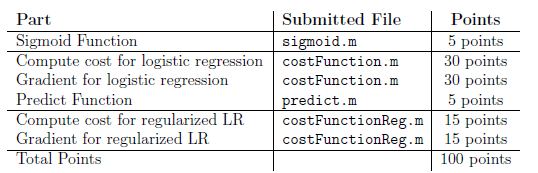

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.